% Path 2 Data
Path2AllData = '/Volumes/JulieE8T/LMCResults';
% Path2AllData = '/Users/elie/Documents/LMCResults';
addpath(genpath('/Users/elie/Documents/CODE/GitHub/GeneralCode'))
addpath(genpath('/Users/elie/Documents/CODE/GitHub/LMC'))
ADBitVolts_sorting=500/32767; %Conversion value used in mat2ntt for proper ploting under spikesort3D in AD count
% Let's find the date of interest in the Google sheet
% Path2RecordingTable = '/Users/elie/Google Drive/BatmanData/RecordingLogs/recording_logs.xlsx';
% [~,~,RecTableData]=xlsread(Path2RecordingTable,1,'A1:AF200','basic');
% Header = RecTableData(1,:);
% ND_IDCol = find(contains(Header, 'Neural data voc in operant + PSTH'));
% BatIDCol = find(contains(Header, 'Bat'));
% NLCol = find(contains(Header, 'NL'));
% Dates_Ind = find(cell2mat(RecTableData(2:end,ND_IDCol))==1)+1;
% Dates = cell2mat(RecTableData(Dates_Ind,1));
ThreshSig=50;

% Data Loader to skip re-running
load(fullfile(Path2AllData,'explore_populationSU_data.mat'))
Trim = 500;
Tstart = -5000;
TBa = length(Tstart+Trim:min([Tmax(:,1); Tmax(:,7)]));
TTr = length(Tstart+Trim:min([Tmax(:,2); Tmax(:,8)]));

## Loop through spike sorting units and evaluate quality

% Load the list of Spike sorted units generated by
% wrapper_allbehav_neuroscript
load(fullfile(Path2AllData, 'ListSSU.mat'), 'ListSSU')
NU = length(ListSSU);

SSQ = cell(NU,1);
SNR = nan(NU,1);
ContamInd = nan(NU,1);
ISIViolation = nan(NU,1);
SubjID = cell(NU,1);
ListCells = cell(NU,1);
for ss=1:NU
    fprintf(1,'File %d/%d\n',ss,NU)
    [~,FileName] = fileparts(ListSSU{ss});
    Ind_ = strfind(FileName,'_');
    SubjectID_local = FileName(1:5);
    Date = FileName(7:14);
    TetrodeID = FileName(Ind_(2)+3);
    SSQ_local = FileName(Ind_(3)+3);
    SSID = FileName(Ind_(4)+1:end);
    ListCells{ss} = fullfile(Path2AllData,sprintf('%s_%s_SS%s_%s-%s.mat', SubjectID_local, Date,SSQ_local,TetrodeID,SSID));
    Data=load(ListCells{ss});
    SubjID{ss} = SubjectID_local;
    SNR(ss) = max(Data.QualitySSU.SNR);
    ContamInd(ss) = Data.QualitySSU.ContamInd;
    ISIViolation(ss) = Data.QualitySSU.ISIViolation;
    if (SNR(ss)>=5) && (ISIViolation(ss)<=1) && (ContamInd(ss)<=0.2)
        SSQ{ss} = 'SSSU';
    elseif (SNR(ss)>=2)
        SSQ{ss} = 'SSMU';
    else
        SSQ{ss} = 'NOISE';
    end
end


SSSU = (SNR>=5) .* (ISIViolation<=1) .* (ContamInd<=0.2);
SSMU = ~SSSU .* (SNR>=2);
NOISE = SNR<2;
C = [NOISE SSSU SSMU];
fprintf('Number of single units: %d/%d, %.2f%%\n',sum(SSSU), NU,sum(SSSU)/NU*100)
fprintf('Number of multi-units: %d/%d, %.2f%%\n',sum(SSMU), NU,sum(SSMU)/NU*100)
fprintf('Number of Noise units: %d/%d, %.2f%%\n',sum(NOISE), NU,sum(NOISE)/NU*100)

% GoodCellIndices = find(contains(SSQ, 'SS'));

% C = [contains(SSQ, 'NOISE') contains(SSQ, 'SSSU') contains(SSQ, 'SSMU')];
scatter(ISIViolation, SNR,40,C,'filled')
xlabel('ISI violation (%)')
ylabel('SNR spike shape')
ContamInd(ContamInd>1)=1; %saturate the ContamInd, everything above 1 is just highly contaminated
scatter(ISIViolation,ContamInd, 40, C,'filled')
xlabel('ISI violation (%)')
ylabel('Poisson contamination Index')

## Hierarchical clustering on KDE onset of all cells for Ba and Tr in Operant and Free sessions

% gather the data
% There are weird effect of convolution at edges so Trim data 500ms
Trim = 500;
Tstart = -5000;
GoodCellIndices = sort([find(SSSU); find(SSMU)]);
GC = length(GoodCellIndices);
KDE_onset = cell(GC,9); % first column SelfBaOp, 2nd, SelfTrOp; 3rd SelfVocOp; 4th column SelfBaFr, 5th, SelfTrFr; 6th SelfVocFr; 7th column OthersBaOp, 8th, OthersTrOp; 9th OthersVocOp;
T_onset = cell(GC,2);
Tmax = nan(GC,9);
MeanKDEBaTrOp = nan(GC,1);
StdKDEBaTrOp = nan(GC,1);
MeanKDEBaTrFr = nan(GC,1);
StdKDEBaTrFr = nan(GC,1);
MeanKDEBaTrOpFr = nan(GC,1);
StdKDEBaTrOpFr = nan(GC,1);
MeanKDEAllVocOp = nan(GC,1);
StdKDEAllVocOp = nan(GC,1);
MeanKDEAllVocFr = nan(GC,1);
StdKDEAllVocFr = nan(GC,1);
MeanKDEAllVocOpFr = nan(GC,1);
StdKDEAllVocOpFr = nan(GC,1);
OperantVocalizer = nan(GC,1);
for ss=1:GC
    fprintf(1,'File %d/%d\n',ss,GC)
    Data=load(ListCells{GoodCellIndices(ss)});
    if isfield(Data,'KDE_onset') && isfield(Data.KDE_onset, 'SelfBaOp')
        if contains(ListCells{GoodCellIndices(ss)}, '65701')
            warning('Unexpected that 65701 has vocalproduction in Operant')
            keyboard
        end
        OperantVocalizer(ss) = 1;
        Tmax(ss,1) = max(Data.KDE_onset.SelfBaOp(2,(1:(end-Trim))));
        KDE_onset{ss,1} = Data.KDE_onset.SelfBaOp(1,find(Data.KDE_onset.SelfBaOp(2,:)==(Tstart+Trim)):(end-Trim));
    end
    if isfield(Data,'KDE_onset') && isfield(Data.KDE_onset, 'SelfTrOp')
        if contains(ListCells{GoodCellIndices(ss)}, '65701')
            warning('Unexpected that 65701 has vocalproduction in Operant')
            keyboard
        end
        OperantVocalizer(ss) = 1;
        Tmax(ss,2) = max(Data.KDE_onset.SelfTrOp(2,1:(end-Trim)));
        KDE_onset{ss,2} = Data.KDE_onset.SelfTrOp(1,find(Data.KDE_onset.SelfTrOp(2,:)==(Tstart+Trim)):(end-Trim));
    end
    if isfield(Data,'KDE_onset') && isfield(Data.KDE_onset, 'SelfVocOp')
        if contains(ListCells{GoodCellIndices(ss)}, '65701')
            warning('Unexpected that 65701 has vocalproduction in Operant')
            keyboard
        end
        OperantVocalizer(ss) = 1;
        Tmax(ss,3) = max(Data.KDE_onset.SelfVocOp(2,1:(end-Trim)));
        KDE_onset{ss,3} = Data.KDE_onset.SelfVocOp(1,find(Data.KDE_onset.SelfVocOp(2,:)==(Tstart+Trim)):(end-Trim));
        MeanKDEAllVocOp(ss) = nanmean(KDE_onset{ss,3}); 
        StdKDEAllVocOp(ss) = nanstd(KDE_onset{ss,3}); 
    end
    
    if isfield(Data,'KDE_onset') && isfield(Data.KDE_onset, 'SelfBaFr')
        Tmax(ss,4) = max(Data.KDE_onset.SelfBaFr(2,1:(end-Trim)));
        KDE_onset{ss,4} = Data.KDE_onset.SelfBaFr(1,find(Data.KDE_onset.SelfBaFr(2,:)==(Tstart+Trim)):(end-Trim));
    end
    if isfield(Data,'KDE_onset') && isfield(Data.KDE_onset, 'SelfTrFr')
        Tmax(ss,5) = max(Data.KDE_onset.SelfTrFr(2,1:(end-Trim)));
        KDE_onset{ss,5} = Data.KDE_onset.SelfTrFr(1,find(Data.KDE_onset.SelfTrFr(2,:)==(Tstart+Trim)):(end-Trim));
    end
    if isfield(Data,'KDE_onset') && isfield(Data.KDE_onset, 'SelfVocFr')
        Tmax(ss,6) = max(Data.KDE_onset.SelfVocFr(2,1:(end-Trim)));
        KDE_onset{ss,6} = Data.KDE_onset.SelfVocFr(1,find(Data.KDE_onset.SelfVocFr(2,:)==(Tstart+Trim)):(end-Trim));
        MeanKDEAllVocFr(ss) = nanmean(KDE_onset{ss,6}); 
        StdKDEAllVocFr(ss) = nanstd(KDE_onset{ss,6}); 
    end
    MeanKDEBaTrFr(ss) = nanmean([KDE_onset{ss,4} KDE_onset{ss,5}]); 
    StdKDEBaTrFr(ss) = nanstd([KDE_onset{ss,4} KDE_onset{ss,5}]); 
    MeanKDEBaTrOpFr(ss) = nanmean([KDE_onset{ss,4} KDE_onset{ss,5} KDE_onset{ss,1} KDE_onset{ss,2}]); 
    StdKDEBaTrOpFr(ss) = nanstd([KDE_onset{ss,4} KDE_onset{ss,5} KDE_onset{ss,1} KDE_onset{ss,2}]);
    MeanKDEAllVocOpFr(ss) = nanmean([KDE_onset{ss,3} KDE_onset{ss,6}]); 
    StdKDEAllVocOpFr(ss) = nanstd([KDE_onset{ss,3} KDE_onset{ss,6}]); 

    if isfield(Data,'KDE_onset') && isfield(Data.KDE_onset, 'OthersBaOp')
        if contains(ListCells{GoodCellIndices(ss)}, '59834') || contains(ListCells{GoodCellIndices(ss)}, '11689')
            warning('Unexpected that 59834 or 11689 has vocal perception in Operant')
            keyboard
        end
        OperantVocalizer(ss) = 0;
        Tmax(ss,7) = max(Data.KDE_onset.OthersBaOp(2,(1:(end-Trim))));
        KDE_onset{ss,7} = Data.KDE_onset.OthersBaOp(1,find(Data.KDE_onset.OthersBaOp(2,:)==(Tstart+Trim)):(end-Trim));
    end
    if isfield(Data,'KDE_onset') && isfield(Data.KDE_onset, 'OthersTrOp')
        if contains(ListCells{GoodCellIndices(ss)}, '59834') || contains(ListCells{GoodCellIndices(ss)}, '11689')
            warning('Unexpected that 59834 or 11689 has vocal perception in Operant')
            keyboard
        end
        OperantVocalizer(ss) = 0;
        Tmax(ss,8) = max(Data.KDE_onset.OthersTrOp(2,1:(end-Trim)));
        KDE_onset{ss,8} = Data.KDE_onset.OthersTrOp(1,find(Data.KDE_onset.OthersTrOp(2,:)==(Tstart+Trim)):(end-Trim));
    end
    if isfield(Data,'KDE_onset') && isfield(Data.KDE_onset, 'OthersVocOp')
        if contains(ListCells{GoodCellIndices(ss)}, '59834') || contains(ListCells{GoodCellIndices(ss)}, '11689')
            warning('Unexpected that 59834 or 11689 has vocal perception in Operant')
            keyboard
        end
        OperantVocalizer(ss) = 0;
        Tmax(ss,9) = max(Data.KDE_onset.OthersVocOp(2,1:(end-Trim)));
        KDE_onset{ss,9} = Data.KDE_onset.OthersVocOp(1,find(Data.KDE_onset.OthersVocOp(2,:)==(Tstart+Trim)):(end-Trim));
        MeanKDEAllVocOp(ss) = nanmean(KDE_onset{ss,9}); 
        StdKDEAllVocOp(ss) = nanstd(KDE_onset{ss,9}); 
    end
    if OperantVocalizer(ss)
        MeanKDEBaTrOp(ss) = nanmean([KDE_onset{ss,1} KDE_onset{ss,2}]); 
        StdKDEBaTrOp(ss) = nanstd([KDE_onset{ss,1} KDE_onset{ss,2}]); 
    else
        MeanKDEBaTrOp(ss) = nanmean([KDE_onset{ss,7} KDE_onset{ss,8}]); 
        StdKDEBaTrOp(ss) = nanstd([KDE_onset{ss,7} KDE_onset{ss,8}]); 
    end

end
save(fullfile(Path2AllData,'explore_populationSU_data.mat'), 'SSQ','SNR','ContamInd', 'ISIViolation', 'SubjID','SSSU', 'SSMU', 'ListCells','GoodCellIndices', 'KDE_onset','T_onset', 'Tmax', 'MeanKDEBaTrOp', 'StdKDEBaTrOp','StdKDEBaTrFr','MeanKDEBaTrFr','MeanKDEBaTrOpFr', 'StdKDEBaTrOpFr','MeanKDEAllVocOp','StdKDEAllVocOp','MeanKDEAllVocFr','StdKDEAllVocFr', 'MeanKDEAllVocOpFr','StdKDEAllVocOpFr','OperantVocalizer')

% Explore the average spike rates and get rid of non active cells?
histogram(MeanKDEAllVocOp,'BinWidth',0.1)
hold on
histogram(MeanKDEAllVocFr,'BinWidth',0.1)
legend('Operant', 'Free')
xlabel('Mean KDE All Voc (Hz)')
ylabel('# units')
hold off
histogram(MeanKDEAllVocOp,'BinWidth',0.1)
hold on
histogram(MeanKDEAllVocFr,'BinWidth',0.1)
legend('Operant', 'Free')
xlabel('Mean KDE All Voc (Hz)')
ylabel('# units')
xlim([0 5])
hold off
scatter(MeanKDEAllVocOp,MeanKDEAllVocFr, 20, 'filled')
xlabel('Mean KDE All Voc (Hz) Operant')
ylabel('Mean KDE All Voc (Hz) Free')
ActiveCells = find((MeanKDEAllVocOp>0.1) + (MeanKDEAllVocFr>0.1));
fprintf(1,'Number of active cells: %d/%d',length(ActiveCells), length(MeanKDEAllVocOp))

% Trim the data of active cells in time and create a matrix of all the
% z-scored KDE Tr and Ba Op For both Hearing and vocalizing bats

BaTr_0ind = (~isnan(Tmax(:,1))+~isnan(Tmax(:,7))) .* (~isnan(Tmax(:,2))+~isnan(Tmax(:,8))).* ~isnan(MeanKDEBaTrOp).*MeanKDEAllVocOp>0.1; % select cells that are either from vocalizer or listener of both Trills and non-trills during operant and that have a minimum average rate over all voc of 0.1Hz
BaTr_Ind = find(BaTr_0ind);
fprintf('The clustering algorithm can be performed on the data of %d/%d\n',sum(BaTr_0ind),length(ActiveCells))

The clustering algorithm can be performed on the data of 680/968


TBa = length(Tstart+Trim:min([Tmax(:,1); Tmax(:,7)]));
TTr = length(Tstart+Trim:min([Tmax(:,2); Tmax(:,8)]));
KDE_onset_Mat_BaTr_ZS_noTrim = nan(sum(BaTr_0ind),TBa + TTr);
for ss=1:sum(BaTr_0ind)
    fprintf(1,'File %d/%d\n',ss,sum(BaTr_0ind))
    if OperantVocalizer(BaTr_Ind(ss))
        KDE_onset_Mat_BaTr_ZS_noTrim(ss,:) = ([KDE_onset{BaTr_Ind(ss),1}(1:TBa) KDE_onset{BaTr_Ind(ss),2}(1:TTr)]-MeanKDEBaTrOp(BaTr_Ind(ss)))/StdKDEBaTrOp(BaTr_Ind(ss));
    else
        KDE_onset_Mat_BaTr_ZS_noTrim(ss,:) = ([KDE_onset{BaTr_Ind(ss),7}(1:TBa) KDE_onset{BaTr_Ind(ss),8}(1:TTr)]-MeanKDEBaTrOp(BaTr_Ind(ss)))/StdKDEBaTrOp(BaTr_Ind(ss));
    end
end
save('explore_populationSU.m', 'KDE_onset_Mat_BaTr_ZS_noTrim', 'BaTr_Ind','BaTr_0ind', '-append')

% Trim the data of active cells in time and create a matrix of all the
% z-scored KDE for all vocalizations and Fr and Op

OpFr_0ind = ~isnan(Tmax(:,3)) .* ~isnan(Tmax(:,6)).* ~isnan(MeanKDEBaTrOpFr).*((MeanKDEAllVocOp>0.1) + (MeanKDEAllVocFr>0.1))>0;
OpFr_Ind = find(OpFr_0ind);
fprintf('The clustering algorithm can be performed on the data of %d/%d\n',sum(OpFr_0ind),length(ActiveCells))
TOp = length(Tstart+Trim:min(Tmax(:,3)));
TFr = length(Tstart+Trim:min(Tmax(:,6)));
KDE_onset_Mat_OpFr_ZS_noTrim = nan(sum(OpFr_0ind),TOp + TFr);
for ss=1:sum(OpFr_0ind)
    fprintf(1,'File %d/%d\n',ss,sum(OpFr_0ind))
    KDE_onset_Mat_OpFr_ZS_noTrim(ss,:) = ([KDE_onset{OpFr_Ind(ss),3}(1:TOp) KDE_onset{OpFr_Ind(ss),6}(1:TFr)]-MeanKDEBaTrOpFr(OpFr_Ind(ss)))/StdKDEBaTrOpFr(OpFr_Ind(ss));
end

% Explore the number of time points with signficant (zscore>2) difference
% in spike rate
SignifTP = sum(abs(KDE_onset_Mat_OpFr_ZS_noTrim)>1.6,2);
histogram(SignifTP, 'BinWidth',10)
xlabel('Number of significant time points (ms)')
ylabel('# units')
histogram(SignifTP(logical(SignifTP)), 'BinWidth',20)
xlabel('Number of significant time points (ms)')
ylabel('# units')
fprintf(1,'%d/%d (%.2f %%) units are significant\n',sum(logical(SignifTP)),length(SignifTP),100*sum(logical(SignifTP))/length(SignifTP))
fprintf(1, 'Duration of significance: %.1f +/- %.1f ms\n',mean(SignifTP(logical(SignifTP))), std(SignifTP(logical(SignifTP)))/(sum(logical(SignifTP)))^0.5)
fprintf(1,'Minimum value %.1f ms\n',min(SignifTP(logical(SignifTP))))
fprintf(1, 'Maximum value %.1f ms\n',max(SignifTP(logical(SignifTP))))


ListCellsGC = ListCells(GoodCellIndices);
ListCellsGCOpFr = ListCellsGC(OpFr_Ind);
NonSignif=find(~logical(SignifTP));
fprintf(1,'***** Checking non-significant cells ******')
figure;
for ii=1:length(NonSignif)
    clc
    set(gcf, 'Visible','on')
    [~,Filename,~]=(fileparts(ListCellsGCOpFr(NonSignif(ii))))
    fprintf(1,'%s', Filename)
    plot(KDE_onset_Mat_OpFr_ZS_noTrim(NonSignif(ii),:))
    title(sprintf('%s',Filename))
    pause()
end

% Restrict the dataset to significant cells
% KDE_onset_Mat_BaTr_ZS = KDE_onset_Mat_BaTr_ZS_noTrim(logical(SignifTP),:);
% BaTr_ind = BaTr_Ind(logical(SignifTP));

% Clustering based on zscored KDE Of Opeant and Free KDE
hold off
Z = linkage(KDE_onset_Mat_OpFr_ZS_noTrim,'ward','euclidean');
[D1, T1, ~] = dendrogram(Z,0, 'ColorThreshold','Default','Orientation','left');
set(D1,'LineWidth',2)
ClustSize = 2:20;
MeanSilhouette = nan(size(ClustSize));
MedianSilhouette = nan(size(ClustSize));
PercLowSilhouette = nan(size(ClustSize));
LowSi = 0.3;
for cc=1:length(ClustSize)
    T = cluster(Z,'maxclust',ClustSize(cc));
    [Si,h] = silhouette(KDE_onset_Mat_OpFr_ZS_noTrim,T, 'Euclidean');
    MeanSilhouette(cc) = mean(Si);
    MedianSilhouette(cc) = median(Si);
    PercLowSilhouette(cc) = sum(Si<LowSi)/length(Si);
end
eva = evalclusters(KDE_onset_Mat_OpFr_ZS_noTrim, 'linkage','CalinskiHarabasz','KList',1:15)
eva = evalclusters(KDE_onset_Mat_OpFr_ZS_noTrim, 'linkage','DaviesBouldin','KList',1:15)
eva = evalclusters(KDE_onset_Mat_OpFr_ZS_noTrim, 'linkage','silhouette','KList',1:15)

plot(ClustSize, MeanSilhouette, 'LineWidth',2);
hold on
plot(ClustSize, MedianSilhouette, 'LineWidth',2);
xlabel('Cluster Size')
ylabel('Silhouette')
legend('Mean', 'Median')
hold off
plot(ClustSize, PercLowSilhouette, 'LineWidth',2);
ylabel('Proportion leaves with Low Silhouette')
%% According to all these metrics, the data are clearly clustered in 3

T = cluster(Z,'maxclust',3);
cutoff = median([Z(end-2,3) Z(end-1,3)]);
D3=dendrogram(Z,0,'ColorThreshold',cutoff,'Labels',num2str(T),'Orientation','left');
set(D3, 'LineWidth',2)
D3_30=dendrogram(Z,30,'ColorThreshold',cutoff,'Labels',num2str(T),'Orientation','left');
set(D3_30, 'LineWidth',2)
[D3_3,T3,O3]=dendrogram(Z,3,'ColorThreshold',cutoff,'Labels',num2str(T),'Orientation','left');
set(D3_3, 'LineWidth',2)

% PLot the average profil of cells under the 3 first clusters
hold off
plot(mean(KDE_onset_Mat_OpFr_ZS_noTrim(T==1,:)), 'LineWidth',2, 'Color',[0 0.4470 0.7410])
hold on
plot(mean(KDE_onset_Mat_OpFr_ZS_noTrim(T==2,:)), 'LineWidth',2, 'Color', [0.8500 0.3250 0.0980])
hold on
plot(mean(KDE_onset_Mat_OpFr_ZS_noTrim(T==3,:)), 'LineWidth',2, 'Color',[0.9290 0.6940 0.1250])
legend(sprintf('Clust1 (n=%d)',sum(T==1)), sprintf('Clust2 (n=%d)',sum(T==2)), sprintf('Clust3 (n=%d)', sum(T==3)), 'Location', 'northwest')
legend('AutoUpdate','off')

NT = size(KDE_onset_Mat_OpFr_ZS_noTrim,2);
hold on
shadedErrorBar(1:NT, mean(KDE_onset_Mat_OpFr_ZS_noTrim(T==1,:)),std(KDE_onset_Mat_OpFr_ZS_noTrim(T==1,:))./(sum(T==1))^0.5,{'-', 'Color',[0 0.4470 0.7410]})
hold on
shadedErrorBar(1:NT,mean(KDE_onset_Mat_OpFr_ZS_noTrim(T==2,:)),std(KDE_onset_Mat_OpFr_ZS_noTrim(T==2,:))./(sum(T==2))^0.5,{'-', 'Color',[0.8500 0.3250 0.0980]})
hold on
shadedErrorBar(1:NT,mean(KDE_onset_Mat_OpFr_ZS_noTrim(T==3,:)),std(KDE_onset_Mat_OpFr_ZS_noTrim(T==3,:))./(sum(T==3))^0.5,{'-', 'Color',[0.9290 0.6940 0.1250]})
ylabel('Zscore Rate')
xlabel('Time (s)')
xticks([1 -(Tstart+Trim) TOp TOp-(Tstart+Trim)])
xticklabels([(Tstart+Trim)/10^3 0 (Tstart+Trim)/10^3 0])
title('Operant               Free')
hold off

% Eliminate cluster 1 and cluster again
ReclustInd = T~=1;
hold off
Z = linkage(KDE_onset_Mat_OpFr_ZS_noTrim(ReclustInd,:),'ward','euclidean');
[D1, T1, ~] = dendrogram(Z,0, 'ColorThreshold','Default','Orientation','left');
set(D1,'LineWidth',2)
ClustSize = 2:20;
MeanSilhouette = nan(size(ClustSize));
MedianSilhouette = nan(size(ClustSize));
PercLowSilhouette = nan(size(ClustSize));
LowSi = 0.3;
for cc=1:length(ClustSize)
    T_local = cluster(Z,'maxclust',ClustSize(cc));
    [Si,h] = silhouette(KDE_onset_Mat_OpFr_ZS_noTrim(ReclustInd,:),T_local, 'Euclidean');
    MeanSilhouette(cc) = mean(Si);
    MedianSilhouette(cc) = median(Si);
    PercLowSilhouette(cc) = sum(Si<LowSi)/length(Si);
end
eva = evalclusters(KDE_onset_Mat_OpFr_ZS_noTrim(ReclustInd,:), 'linkage','CalinskiHarabasz','KList',1:15)
eva = evalclusters(KDE_onset_Mat_OpFr_ZS_noTrim(ReclustInd,:), 'linkage','DaviesBouldin','KList',1:15)
eva = evalclusters(KDE_onset_Mat_OpFr_ZS_noTrim(ReclustInd,:), 'linkage','silhouette','KList',1:15)

plot(ClustSize, MeanSilhouette, 'LineWidth',2);
hold on
plot(ClustSize, MedianSilhouette, 'LineWidth',2);
xlabel('Cluster Size')
ylabel('Silhouette')
legend('Mean', 'Median')
hold off
plot(ClustSize, PercLowSilhouette, 'LineWidth',2);
ylabel('Proportion leaves with Low Silhouette')
%% According to all these metrics, the data are clearly clustered in 2

% Re-cluster all data around 5 clusters and investigate functional features
Z = linkage(KDE_onset_Mat_OpFr_ZS_noTrim,'ward','euclidean');
T5 = cluster(Z,'maxclust',5);
cutoff = median([Z(end-4,3) Z(end-3,3)]);
D5=dendrogram(Z,0,'ColorThreshold',cutoff,'Labels',num2str(T5),'Orientation','left');
set(D5, 'LineWidth',2)
D5_30=dendrogram(Z,30,'ColorThreshold',cutoff,'Labels',num2str(T5),'Orientation','left');
set(D5_30, 'LineWidth',2)
[D5_5,T5_d,O5]=dendrogram(Z,5,'ColorThreshold',cutoff,'Labels',num2str(T5),'Orientation','left');
set(D5_5, 'LineWidth',2)

% PLot the average profil of cells under the 5 first clusters
ColClust1 = [0 0.4470 0.7410];
ColClust2 = [0.8500 0.3250 0.0980];
ColClust3 = [0.9290 0.6940 0.1250];
ColClust4 = [0.4940 0.1840 0.5560];
ColClust5 = [0.4660 0.6740 0.1880];
hold off
plot(mean(KDE_onset_Mat_OpFr_ZS_noTrim(T5==1,:)), 'LineWidth',2, 'Color',ColClust1)
hold on
plot(mean(KDE_onset_Mat_OpFr_ZS_noTrim(T5==2,:)), 'LineWidth',2, 'Color', ColClust2)
hold on
plot(mean(KDE_onset_Mat_OpFr_ZS_noTrim(T5==3,:)), 'LineWidth',2, 'Color',ColClust3)
hold on
plot(mean(KDE_onset_Mat_OpFr_ZS_noTrim(T5==4,:)), 'LineWidth',2, 'Color',ColClust4)
hold on
plot(mean(KDE_onset_Mat_OpFr_ZS_noTrim(T5==5,:)), 'LineWidth',2, 'Color',ColClust5)
legend(sprintf('Clust1 (n=%d)',sum(T5==1)), sprintf('Clust2 (n=%d)',sum(T5==2)), sprintf('Clust3 (n=%d)', sum(T5==3)),sprintf('Clust4 (n=%d)', sum(T5==4)),sprintf('Clust5 (n=%d)', sum(T5==5)), 'Location', 'northwest')
legend('AutoUpdate','off')

NT = size(KDE_onset_Mat_OpFr_ZS_noTrim,2);
hold on
shadedErrorBar(1:NT, mean(KDE_onset_Mat_OpFr_ZS_noTrim(T5==1,:)),std(KDE_onset_Mat_OpFr_ZS_noTrim(T5==1,:))./(sum(T5==1))^0.5,{'-', 'Color',ColClust1})
hold on
shadedErrorBar(1:NT,mean(KDE_onset_Mat_OpFr_ZS_noTrim(T5==2,:)),std(KDE_onset_Mat_OpFr_ZS_noTrim(T5==2,:))./(sum(T5==2))^0.5,{'-', 'Color',ColClust2})
hold on
shadedErrorBar(1:NT,mean(KDE_onset_Mat_OpFr_ZS_noTrim(T5==3,:)),std(KDE_onset_Mat_OpFr_ZS_noTrim(T5==3,:))./(sum(T5==3))^0.5,{'-', 'Color',ColClust3})
hold on
shadedErrorBar(1:NT,mean(KDE_onset_Mat_OpFr_ZS_noTrim(T5==4,:)),std(KDE_onset_Mat_OpFr_ZS_noTrim(T5==4,:))./(sum(T5==4))^0.5,{'-', 'Color',ColClust4})
hold on
shadedErrorBar(1:NT,mean(KDE_onset_Mat_OpFr_ZS_noTrim(T5==5,:)),std(KDE_onset_Mat_OpFr_ZS_noTrim(T5==5,:))./(sum(T5==5))^0.5,{'-', 'Color',ColClust5})
ylabel('Zscore Rate')
xlabel('Time (s)')
xticks([1 -(Tstart+Trim) TOp TOp-(Tstart+Trim)])
xticklabels([(Tstart+Trim)/10^3 0 (Tstart+Trim)/10^3 0])
title('Operant               Free')
hold off

hold off
plot(mean(KDE_onset_Mat_OpFr_ZS_noTrim(T5==1,:)), 'LineWidth',2, 'Color',ColClust1)
hold on
plot(mean(KDE_onset_Mat_OpFr_ZS_noTrim(T5==2,:)), 'LineWidth',2, 'Color',ColClust2)
hold on
plot(mean(KDE_onset_Mat_OpFr_ZS_noTrim(T5==3,:)), 'LineWidth',2, 'Color',ColClust3)
hold on
plot(mean(KDE_onset_Mat_OpFr_ZS_noTrim(T5==4,:)), 'LineWidth',2, 'Color',ColClust4)
legend(sprintf('Clust1 (n=%d)',sum(T5==1)), sprintf('Clust2 (n=%d)',sum(T5==2)), sprintf('Clust3 (n=%d)', sum(T5==3)),sprintf('Clust4 (n=%d)', sum(T5==4)), 'Location','eastoutside')
legend('AutoUpdate','off')

NT = size(KDE_onset_Mat_OpFr_ZS_noTrim,2);
hold on
shadedErrorBar(1:NT, mean(KDE_onset_Mat_OpFr_ZS_noTrim(T5==1,:)),std(KDE_onset_Mat_OpFr_ZS_noTrim(T5==1,:))./(sum(T5==1))^0.5,{'-', 'Color',ColClust1})
hold on
shadedErrorBar(1:NT,mean(KDE_onset_Mat_OpFr_ZS_noTrim(T5==2,:)),std(KDE_onset_Mat_OpFr_ZS_noTrim(T5==2,:))./(sum(T5==2))^0.5,{'-', 'Color',ColClust2})
hold on
shadedErrorBar(1:NT,mean(KDE_onset_Mat_OpFr_ZS_noTrim(T5==3,:)),std(KDE_onset_Mat_OpFr_ZS_noTrim(T5==3,:))./(sum(T5==3))^0.5,{'-', 'Color',ColClust3})
hold on
shadedErrorBar(1:NT,mean(KDE_onset_Mat_OpFr_ZS_noTrim(T5==4,:)),std(KDE_onset_Mat_OpFr_ZS_noTrim(T5==4,:))./(sum(T5==4))^0.5,{'-', 'Color',ColClust4})
ylabel('Zscore Rate')
xlabel('Time (s)')
xticks([1 -(Tstart+Trim) TOp TOp-(Tstart+Trim)])
xticklabels([(Tstart+Trim)/10^3 0 (Tstart+Trim)/10^3 0])
title('Operant               Free')
hold off

% Explore values of MI COherence with Vocal production in Operant
HDPath = '/Volumes/JulieE8T/LMCResults/';
MC = load(fullfile(HDPath,sprintf('MotorCoherence_%s_%s.mat', 'amp', 'Operant')));
ListCellsGC = ListCells(GoodCellIndices); % Select cells spike sorted as eitherMU or SU
ListCellsGCOpFr = ListCellsGC(OpFr_Ind); % Selecte cells with a minimum of 0.1Hz either during Op or Fr
% Gather data on Info
InfoOp = nan(length(ListCellsGCOpFr),3);% first column value of info, 2nd pRandSpikePer, 3rd pRandVoc
NanCount = [];
for cc=1:length(MC.CellsPath)
    Ind=find(contains(ListCellsGCOpFr, MC.CellsPath(cc).name));
    if ~isempty(Ind)
        InfoOp(Ind,1) = MC.Info(cc);
        if isnan(MC.Info(cc))
            NanCount = [NanCount Ind];
        end
        InfoOp(Ind,2) = MC.Info_pRandSpikePerm(cc);
        InfoOp(Ind,3) = MC.Info_pRandVoc(cc);
    end
end
% note that Motor coherence calculation was not run on {'/Volumes/JulieE8T/LMCResults/59834_20190630_SSS_2-150.mat'}
% Probably because of data corruption issues (I rerun all the extraction
% steps after spike sorting on 10/23/2021 because the file could not be
% opened by matlab anymore)

ScatterMarkerSz=30;
MeanMarkerSize=14;
hold off
swarmchart(ones(sum(T5==1),1),InfoOp(T5==1),ScatterMarkerSz,ColClust1,'o','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5)
hold on
errorbar(1,nanmean(InfoOp(T5==1)),nanstd(InfoOp(T5==1))/sum(~isnan(InfoOp(T5==1)))^0.5, 'dr','MarkerSize',MeanMarkerSize,'MarkerFaceColor',ColClust1)
hold on
swarmchart(2*ones(sum(T5==2),1),InfoOp(T5==2),ScatterMarkerSz,ColClust2,'o','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5)
hold on
errorbar(2,nanmean(InfoOp(T5==2)),nanstd(InfoOp(T5==2))/sum(~isnan(InfoOp(T5==2)))^0.5, 'dr','MarkerSize',MeanMarkerSize,'MarkerFaceColor',ColClust2)
hold on
swarmchart(3*ones(sum(T5==3),1),InfoOp(T5==3),ScatterMarkerSz,ColClust3,'o','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5)
hold on
errorbar(3,nanmean(InfoOp(T5==3)),nanstd(InfoOp(T5==3))/sum(~isnan(InfoOp(T5==3)))^0.5, 'dr','MarkerSize',MeanMarkerSize,'MarkerFaceColor',ColClust3)
hold on
swarmchart(4*ones(sum(T5==4),1),InfoOp(T5==4),ScatterMarkerSz,ColClust4,'o','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5)
hold on
errorbar(4,nanmean(InfoOp(T5==4)),nanstd(InfoOp(T5==4))/sum(~isnan(InfoOp(T5==4)))^0.5, 'dr','MarkerSize',MeanMarkerSize,'MarkerFaceColor',ColClust4)
hold on
swarmchart(5*ones(sum(T5==5),1),InfoOp(T5==5),ScatterMarkerSz,ColClust5,'o','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5)
hold on
errorbar(5,nanmean(InfoOp(T5==5)),nanstd(InfoOp(T5==5))/sum(~isnan(InfoOp(T5==5)))^0.5, 'dr','MarkerSize',MeanMarkerSize,'MarkerFaceColor',ColClust5)
hold off
xlabel('Cluster #')
ylabel('Info on Motor coherence')

The HCA is most likely highly driven by the difference in DC rate between Operant and free sessions. Let's z-score per session and explore again the HCA on Operant only. Instead of a z-score, treat the KDE as a pdf

% Trim the data in time and create a matrix of all the
% z-scored or pdf KDE for all vocalizations of Op. zscoring values for free
% session independantly gives weird results (out of the chart STD?! that mess up the zscore?!)

OpFr_0ind = ~isnan(Tmax(:,3)) .* ~isnan(Tmax(:,6)).* ~isnan(MeanKDEBaTrOpFr).*((MeanKDEAllVocOp>0.1) + (MeanKDEAllVocFr>0.1))>0;
OpFr_Ind = find(OpFr_0ind);
fprintf('The clustering algorithm can be performed on the data of %d/%d\n',sum(OpFr_0ind),length(ActiveCells))
TOp = length(Tstart+Trim:min(Tmax(:,3)));
% TFr = length(Tstart+Trim:min(Tmax(:,6)));
KDE_onset_Mat_Op_pdf_noTrim = nan(sum(OpFr_0ind),TOp);
% KDE_onset_Mat_Op_ZS_noTrim = nan(sum(OpFr_0ind),TOp+TFr);
for ss=1:sum(OpFr_0ind)
    fprintf(1,'File %d/%d\n',ss,sum(OpFr_0ind))
    KDEOp = KDE_onset{OpFr_Ind(ss),3}(1:TOp)./sum(KDE_onset{OpFr_Ind(ss),3}(1:TOp));
%     KDEOp = (KDE_onset{OpFr_Ind(ss),3}(1:TOp)-MeanKDEBaTrOp(OpFr_Ind(ss)))./StdKDEBaTrOp(OpFr_Ind(ss));
%     KDEFr = (KDE_onset{OpFr_Ind(ss),6}(1:TFr)-MeanKDEBaTrFr(OpFr_Ind(ss)))./StdKDEBaTrFr(OpFr_Ind(ss));
    KDE_onset_Mat_Op_pdf_noTrim(ss,:) = KDEOp;
end

% Clustering based on pdf Operant KDE
hold off
Z = linkage(KDE_onset_Mat_Op_pdf_noTrim,'ward','euclidean');
[D1, T1, ~] = dendrogram(Z,0, 'ColorThreshold','Default','Orientation','left');
set(D1,'LineWidth',2)
ClustSize = 2:20;
MeanSilhouette = nan(size(ClustSize));
MedianSilhouette = nan(size(ClustSize));
PercLowSilhouette = nan(size(ClustSize));
LowSi = 0.3;
for cc=1:length(ClustSize)
    T = cluster(Z,'maxclust',ClustSize(cc));
    [Si,h] = silhouette(KDE_onset_Mat_Op_pdf_noTrim,T, 'Euclidean');
    MeanSilhouette(cc) = mean(Si);
    MedianSilhouette(cc) = median(Si);
    PercLowSilhouette(cc) = sum(Si<LowSi)/length(Si);
end
eva = evalclusters(KDE_onset_Mat_Op_pdf_noTrim, 'linkage','CalinskiHarabasz','KList',1:15)
eva = evalclusters(KDE_onset_Mat_Op_pdf_noTrim, 'linkage','DaviesBouldin','KList',1:15)
eva = evalclusters(KDE_onset_Mat_Op_pdf_noTrim, 'linkage','silhouette','KList',1:15)

plot(ClustSize, MeanSilhouette, 'LineWidth',2);
hold on
plot(ClustSize, MedianSilhouette, 'LineWidth',2);
xlabel('Cluster Size')
ylabel('Silhouette')
legend('Mean', 'Median')
hold off
plot(ClustSize, PercLowSilhouette, 'LineWidth',2);
ylabel('Proportion leaves with Low Silhouette')
%% According to all these metrics, the data are clearly clustered in 2 or 7

% Let's do 5 clusters (they seem to cut the data in a reasonnable way) 
T = cluster(Z,'maxclust',5);
cutoff = median([Z(end-4,3) Z(end-3,3)]);
D5=dendrogram(Z,0,'ColorThreshold',cutoff,'Labels',num2str(T),'Orientation','left');
set(D5, 'LineWidth',2)
D5_30=dendrogram(Z,30,'ColorThreshold',cutoff,'Labels',num2str(T),'Orientation','left');
set(D5_30, 'LineWidth',2)
[D5_3,T5,O5]=dendrogram(Z,5,'ColorThreshold',cutoff,'Labels',num2str(T),'Orientation','left');
set(D5_3, 'LineWidth',2)

% PLot the average profil of cells under the 5 first clusters
ColClust1 = [0 0.4470 0.7410];
ColClust2 = [0.8500 0.3250 0.0980];
ColClust3 = [0.9290 0.6940 0.1250];
ColClust4 = [0.4940 0.1840 0.5560];
ColClust5 = [0.4660 0.6740 0.1880];
% ColClust6 = [0.3010 0.7450 0.9330];
hold off
plot(mean(KDE_onset_Mat_Op_pdf_noTrim(T5==1,:)), 'LineWidth',2, 'Color',ColClust1)
hold on
plot(mean(KDE_onset_Mat_Op_pdf_noTrim(T5==2,:)), 'LineWidth',2, 'Color', ColClust2)
hold on
plot(mean(KDE_onset_Mat_Op_pdf_noTrim(T5==3,:)), 'LineWidth',2, 'Color',ColClust3)
hold on
plot(mean(KDE_onset_Mat_Op_pdf_noTrim(T5==4,:)), 'LineWidth',2, 'Color',ColClust4)
hold on
plot(mean(KDE_onset_Mat_Op_pdf_noTrim(T5==5,:)), 'LineWidth',2, 'Color',ColClust5)
% hold on
% plot(mean(KDE_onset_Mat_Op_ZS_noTrim(T6==6,:)), 'LineWidth',2, 'Color',ColClust6)
% legend(sprintf('Clust1 (n=%d)',sum(T6==1)), sprintf('Clust2 (n=%d)',sum(T6==2)), sprintf('Clust3 (n=%d)', sum(T6==3)),sprintf('Clust4 (n=%d)', sum(T6==4)),sprintf('Clust5 (n=%d)', sum(T6==5)),sprintf('Clust6 (n=%d)', sum(T6==6)), 'Location', 'northwest')
legend(sprintf('Clust1 (n=%d)',sum(T6==1)), sprintf('Clust2 (n=%d)',sum(T6==2)), sprintf('Clust3 (n=%d)', sum(T6==3)),sprintf('Clust4 (n=%d)', sum(T6==4)),sprintf('Clust5 (n=%d)', sum(T6==5)), 'Location', 'northwest')
legend('AutoUpdate','off')

NT = size(KDE_onset_Mat_Op_pdf_noTrim,2);
hold on
shadedErrorBar(1:NT, mean(KDE_onset_Mat_Op_pdf_noTrim(T5==1,:)),std(KDE_onset_Mat_Op_pdf_noTrim(T5==1,:))./(sum(T5==1))^0.5,{'-', 'Color',ColClust1})
hold on
shadedErrorBar(1:NT,mean(KDE_onset_Mat_Op_pdf_noTrim(T5==2,:)),std(KDE_onset_Mat_Op_pdf_noTrim(T5==2,:))./(sum(T5==2))^0.5,{'-', 'Color',ColClust2})
hold on
shadedErrorBar(1:NT,mean(KDE_onset_Mat_Op_pdf_noTrim(T5==3,:)),std(KDE_onset_Mat_Op_pdf_noTrim(T5==3,:))./(sum(T5==3))^0.5,{'-', 'Color',ColClust3})
hold on
shadedErrorBar(1:NT,mean(KDE_onset_Mat_Op_pdf_noTrim(T5==4,:)),std(KDE_onset_Mat_Op_pdf_noTrim(T5==4,:))./(sum(T5==4))^0.5,{'-', 'Color',ColClust4})
hold on
shadedErrorBar(1:NT,mean(KDE_onset_Mat_Op_pdf_noTrim(T5==5,:)),std(KDE_onset_Mat_Op_pdf_noTrim(T5==5,:))./(sum(T5==5))^0.5,{'-', 'Color',ColClust5})
% hold on
% shadedErrorBar(1:NT,mean(KDE_onset_Mat_Op_ZS_noTrim(T6==6,:)),std(KDE_onset_Mat_Op_ZS_noTrim(T6==6,:))./(sum(T6==6))^0.5,{'-', 'Color',ColClust6})
ylabel('Rate pdf')
xlabel('Time (s)')
xticks([1 -(Tstart+Trim)])
xticklabels([(Tstart+Trim)/10^3 0])
title('Operant')
hold off

ScatterMarkerSz=30;
MeanMarkerSize=14;
hold off
swarmchart(ones(sum(T5==1),1),InfoOp(T5==1),ScatterMarkerSz,ColClust1,'o','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5)
hold on
errorbar(1,nanmean(InfoOp(T5==1)),nanstd(InfoOp(T5==1))/sum(~isnan(InfoOp(T5==1)))^0.5, 'dr','MarkerSize',MeanMarkerSize,'MarkerFaceColor',ColClust1)
hold on
swarmchart(2*ones(sum(T5==2),1),InfoOp(T5==2),ScatterMarkerSz,ColClust2,'o','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5)
hold on
errorbar(2,nanmean(InfoOp(T5==2)),nanstd(InfoOp(T5==2))/sum(~isnan(InfoOp(T5==2)))^0.5, 'dr','MarkerSize',MeanMarkerSize,'MarkerFaceColor',ColClust2)
hold on
swarmchart(3*ones(sum(T5==3),1),InfoOp(T5==3),ScatterMarkerSz,ColClust3,'o','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5)
hold on
errorbar(3,nanmean(InfoOp(T5==3)),nanstd(InfoOp(T5==3))/sum(~isnan(InfoOp(T5==3)))^0.5, 'dr','MarkerSize',MeanMarkerSize,'MarkerFaceColor',ColClust3)
hold on
swarmchart(4*ones(sum(T5==4),1),InfoOp(T5==4),ScatterMarkerSz,ColClust4,'o','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5)
hold on
errorbar(4,nanmean(InfoOp(T5==4)),nanstd(InfoOp(T5==4))/sum(~isnan(InfoOp(T5==4)))^0.5, 'dr','MarkerSize',MeanMarkerSize,'MarkerFaceColor',ColClust4)
hold on
swarmchart(5*ones(sum(T5==5),1),InfoOp(T5==5),ScatterMarkerSz,ColClust5,'o','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5)
hold on
errorbar(5,nanmean(InfoOp(T5==5)),nanstd(InfoOp(T5==5))/sum(~isnan(InfoOp(T5==5)))^0.5, 'dr','MarkerSize',MeanMarkerSize,'MarkerFaceColor',ColClust5)
hold off
xlabel('Cluster #')
ylabel('Info on Motor coherence')

% Clustering based onzscore Operant KDEof Trill and non-trill calls for
% both vocalizers and non-vocalizers
hold off
Z = linkage(KDE_onset_Mat_BaTr_ZS_noTrim,'ward','euclidean');
[D1, T1, ~] = dendrogram(Z,0, 'ColorThreshold','Default','Orientation','left');
set(D1,'LineWidth',2)
ClustSize = 2:20;
MeanSilhouette = nan(size(ClustSize));
MedianSilhouette = nan(size(ClustSize));
PercLowSilhouette = nan(size(ClustSize));
LowSi = 0.3;
for cc=1:length(ClustSize)
    T = cluster(Z,'maxclust',ClustSize(cc));
    [Si,h] = silhouette(KDE_onset_Mat_BaTr_ZS_noTrim,T, 'Euclidean');
    MeanSilhouette(cc) = mean(Si);
    MedianSilhouette(cc) = median(Si);
    PercLowSilhouette(cc) = sum(Si<LowSi)/length(Si);
end
eva = evalclusters(KDE_onset_Mat_BaTr_ZS_noTrim, 'linkage','CalinskiHarabasz','KList',1:15)
eva = evalclusters(KDE_onset_Mat_BaTr_ZS_noTrim, 'linkage','DaviesBouldin','KList',1:15)
eva = evalclusters(KDE_onset_Mat_BaTr_ZS_noTrim, 'linkage','silhouette','KList',1:15)

plot(ClustSize, MeanSilhouette, 'LineWidth',2);
hold on
plot(ClustSize, MedianSilhouette, 'LineWidth',2);
xlabel('Cluster Size')
ylabel('Silhouette')
legend('Mean', 'Median')
hold off
plot(ClustSize, PercLowSilhouette, 'LineWidth',2);
ylabel('Proportion leaves with Low Silhouette')
%% According to all these metrics, the data are clearly clustered in 3

% Let's do 6 clusters (they seem to cut the data in a reasonnable way) 
T = cluster(Z,'maxclust',6);
cutoff = median([Z(end-5,3) Z(end-4,3)]);
D6=dendrogram(Z,0,'ColorThreshold',cutoff,'Labels',num2str(T),'Orientation','left');
set(D6, 'LineWidth',2)
D6_30=dendrogram(Z,30,'ColorThreshold',cutoff,'Labels',num2str(T),'Orientation','left');
set(D6_30, 'LineWidth',2)
[D6_3,T6,O6]=dendrogram(Z,6,'ColorThreshold',cutoff,'Labels',num2str(T),'Orientation','left');
set(D6_3, 'LineWidth',2)

% PLot the average profil of cells under the 6 first clusters
OV_cells = OperantVocalizer(BaTr_0ind);
POV_cells = sum(OV_cells)/length(OV_cells);
ColClust1 = [0 0.4470 0.7410];
ColClust2 = [0.8500 0.3250 0.0980];
ColClust3 = [0.9290 0.6940 0.1250];
ColClust4 = [0.4940 0.1840 0.5560];
ColClust5 = [0.4660 0.6740 0.1880];
ColClust6 = [0.3010 0.7450 0.9330];
hold off
plot(mean(KDE_onset_Mat_BaTr_ZS_noTrim(T6==1,:)), 'LineWidth',2, 'Color',ColClust1)
hold on
plot(mean(KDE_onset_Mat_BaTr_ZS_noTrim(T6==2,:)), 'LineWidth',2, 'Color', ColClust2)
hold on
plot(mean(KDE_onset_Mat_BaTr_ZS_noTrim(T6==3,:)), 'LineWidth',2, 'Color',ColClust3)
hold on
plot(mean(KDE_onset_Mat_BaTr_ZS_noTrim(T6==4,:)), 'LineWidth',2, 'Color',ColClust4)
hold on
plot(mean(KDE_onset_Mat_BaTr_ZS_noTrim(T6==5,:)), 'LineWidth',2, 'Color',ColClust5)
hold on
plot(mean(KDE_onset_Mat_BaTr_ZS_noTrim(T6==6,:)), 'LineWidth',2, 'Color',ColClust6)
legend(sprintf('Clust1 (n=%d %.2fV)',sum(T6==1),sum(OV_cells(T6==1))/sum(T6==1)-POV_cells), sprintf('Clust2 (n=%d %.2fV)',sum(T6==2),sum(OV_cells(T6==2))/sum(T6==2)-POV_cells), sprintf('Clust3 (n=%d %.2fV)', sum(T6==3),sum(OV_cells(T6==3))/sum(T6==3)-POV_cells),sprintf('Clust4 (n=%d %.2fV)', sum(T6==4),sum(OV_cells(T6==4))/sum(T6==4)-POV_cells),sprintf('Clust5 (n=%d %.2fV)', sum(T6==5),sum(OV_cells(T6==5))/sum(T6==5)-POV_cells),sprintf('Clust6 (n=%d %.2fV)', sum(T6==6),sum(OV_cells(T6==6))/sum(T6==6)-POV_cells), 'Location', 'northoutside')
% legend(sprintf('Clust1 (n=%d)',sum(T6==1)), sprintf('Clust2 (n=%d)',sum(T6==2)), sprintf('Clust3 (n=%d)', sum(T6==3)),sprintf('Clust4 (n=%d)', sum(T6==4)),sprintf('Clust5 (n=%d)', sum(T6==5)), 'Location', 'northwest')
legend('AutoUpdate','off')

NT = size(KDE_onset_Mat_BaTr_ZS_noTrim,2);
hold on
shadedErrorBar(1:NT, mean(KDE_onset_Mat_BaTr_ZS_noTrim(T6==1,:)),std(KDE_onset_Mat_BaTr_ZS_noTrim(T6==1,:))./(sum(T6==1))^0.5,{'-', 'Color',ColClust1})
hold on
shadedErrorBar(1:NT,mean(KDE_onset_Mat_BaTr_ZS_noTrim(T6==2,:)),std(KDE_onset_Mat_BaTr_ZS_noTrim(T6==2,:))./(sum(T6==2))^0.5,{'-', 'Color',ColClust2})
hold on
shadedErrorBar(1:NT,mean(KDE_onset_Mat_BaTr_ZS_noTrim(T6==3,:)),std(KDE_onset_Mat_BaTr_ZS_noTrim(T6==3,:))./(sum(T6==3))^0.5,{'-', 'Color',ColClust3})
hold on
shadedErrorBar(1:NT,mean(KDE_onset_Mat_BaTr_ZS_noTrim(T6==4,:)),std(KDE_onset_Mat_BaTr_ZS_noTrim(T6==4,:))./(sum(T6==4))^0.5,{'-', 'Color',ColClust4})
hold on
shadedErrorBar(1:NT,mean(KDE_onset_Mat_BaTr_ZS_noTrim(T6==5,:)),std(KDE_onset_Mat_BaTr_ZS_noTrim(T6==5,:))./(sum(T6==5))^0.5,{'-', 'Color',ColClust5})
hold on
shadedErrorBar(1:NT,mean(KDE_onset_Mat_BaTr_ZS_noTrim(T6==6,:)),std(KDE_onset_Mat_BaTr_ZS_noTrim(T6==6,:))./(sum(T6==6))^0.5,{'-', 'Color',ColClust6})
ylabel('Z Rate')
xlabel('Time (s)')
xticks([1 -(Tstart+Trim)])
xticklabels([(Tstart+Trim)/10^3 0])
title('Operant')
hold off

## PCA Approach

Let's try a PCA on the ZS

% run PCA on the ZS of the operant KDE
[PC,Score,~, ~, VarExpl,~] = pca(KDE_onset_Mat_BaTr_ZS_noTrim);

% Plot the cumulative explained variance as a function of # PCs
hold off
clf
plot(cumsum(VarExpl), 'LineWidth',2);xlabel('#PC');ylabel('Proportion variance explained by PCA)'); xlim([0 30])
title('PCA on KDE of Trill and non-Trill jointly fed')
% Plot the first PC shapes
plot(PC(:,1), 'LineWidth',2);hold on;plot(PC(:,2), 'LineWidth',2);plot(PC(:,3), 'LineWidth',2);plot(PC(:,4), 'LineWidth',2);plot(PC(:,5), 'LineWidth',2);plot(PC(:,6), 'LineWidth',2);plot(PC(:,7), 'LineWidth',2);plot(PC(:,8), 'LineWidth',2);plot(PC(:,9), 'LineWidth',2);plot(PC(:,10), 'LineWidth',2);legend('PC1', 'PC2','PC3', 'PC4', 'PC5', 'PC6','PC7','PC8','PC9','PC10', 'Location', 'EastOutside'); ylabel('PCA coefficients');xlabel('Time (s)');xticks([1 -(Tstart+Trim)]);xticklabels([(Tstart+Trim)/10^3 0]);title('PCA on KDE of Trill and non-Trill jointly fed')
hold off

% Plot swarmplots of PC weights (scores) with color coded if a cell is from a
% vocalizer or listener
OV_cells = logical(OperantVocalizer(BaTr_0ind)); % Vocalizer cels=1
ColPC = get(groot, 'DefaultAxesColorOrder');
ScatterMarkerSz=30;
MeanMarkerSize=14;
NPC=20;
hold off
for n=1:NPC
    swarmchart((3*n-1)*ones(sum(OV_cells),1),Score(OV_cells,n),ScatterMarkerSz,ColPC(2,:),'o','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5)
    hold on
    swarmchart((3*n)*ones(sum(~OV_cells),1),Score(~OV_cells,n),ScatterMarkerSz,ColPC(1,:),'o','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5)
    hold on
    if n==1
        legend({'Vocalizer', 'Listener'})
        legend('AutoUpdate','off')
    end
    errorbar((3*n-1),nanmean(Score(OV_cells,n)),nanstd(Score(OV_cells,n))/sum(OV_cells)^0.5, 'dk','MarkerSize',MeanMarkerSize,'MarkerFaceColor',ColPC(2,:))
    hold on
    errorbar((3*n),nanmean(Score(~OV_cells,n)),nanstd(Score(~OV_cells,n))/sum(~OV_cells)^0.5, 'dk','MarkerSize',MeanMarkerSize,'MarkerFaceColor',ColPC(1,:))
    hold on
end
set(gca, 'XTick', 3*(1:NPC)-1, 'XTickLabel',1:NPC)
xlabel('PC #')
ylabel('PC score')
title('Weights of PC compomenets for each cell')

### Let's try a PCA on the ZS but feeding independently BA and Tr

load(fullfile(Path2AllData,'explore_populationSU_data.mat'), 'ListCells', 'GoodCellIndices','MeanKDEAllVocOp', 'Tmax','MeanKDEBaTrOp','StdKDEBaTrOp')
Trim = 500;
Tstart = -5000;
TBa = length(Tstart+Trim:min([Tmax(:,1); Tmax(:,7)]));
TTr = length(Tstart+Trim:min([Tmax(:,2); Tmax(:,8)]));

% Trim the data of active cells in time and create a matrix of all the
% z-scored KDE Tr and Ba Op For both Hearing and vocalizing bats

% Cells that are either SMU or SSU
ListCellsG = ListCells(GoodCellIndices);
% Active Cells
ActiveCells01 = MeanKDEAllVocOp>0.1;
ListCellsGA = ListCellsG(ActiveCells01);
% select cells that are either from vocalizer or listener of either Trills and non-trills during operant and that have a minimum average rate over all voc of 0.1Hz
BaorTr_0ind = logical((~isnan(Tmax(:,1)) + ~isnan(Tmax(:,7)) + ~isnan(Tmax(:,2)) + ~isnan(Tmax(:,8))).* (~isnan(MeanKDEBaTrOp)).*(MeanKDEAllVocOp>0.1)); 
BaorTr_Ind = find(BaorTr_0ind);
% select cells that are from vocalizer of both Trills and non-trills during operant and that have a minimum average rate over all voc of 0.1Hz
ListCellsGAOp = ListCellsG(BaorTr_0ind);

fprintf(1, 'Active cells defined as having a minimum time and vocalization average rate of 0.1Hz: %d/%d', sum(ActiveCells01), length(MeanKDEAllVocOp))

Active cells defined as having a minimum time and vocalization average rate of 0.1Hz: 954/973

fprintf('The clustering algorithm can be performed on the data of %d/%d\n',sum(BaorTr_0ind),length(ActiveCells01))

The clustering algorithm can be performed on the data of 954/973



% find the minimum duration of the KDE for all cells
TAll = length(Tstart+Trim:min([Tmax(:,1); Tmax(:,2); Tmax(:,7); Tmax(:,8)]))

TAll = 9089

KDE_onset_Mat_nTr = nan(sum(BaorTr_0ind),TAll);
KDE_onset_Mat_Tr = nan(sum(BaorTr_0ind),TAll);
for ss=1:sum(BaorTr_0ind)
    fprintf(1,'File %d/%d\n',ss,sum(BaorTr_0ind))
    if OperantVocalizer(BaorTr_Ind(ss))
        if ~isempty(KDE_onset{BaorTr_Ind(ss),1})
            KDE_onset_Mat_nTr(ss,:) = (KDE_onset{BaorTr_Ind(ss),1}(1:TAll) -MeanKDEBaTrOp(BaorTr_Ind(ss)))./StdKDEBaTrOp(BaorTr_Ind(ss));
        end 
        if ~isempty(KDE_onset{BaorTr_Ind(ss),2})
            KDE_onset_Mat_Tr(ss,:) = (KDE_onset{BaorTr_Ind(ss),2}(1:TAll) -MeanKDEBaTrOp(BaorTr_Ind(ss)))./StdKDEBaTrOp(BaorTr_Ind(ss));
        end
    else
        if ~isempty(KDE_onset{BaorTr_Ind(ss),7})
            KDE_onset_Mat_nTr(ss,:) = (KDE_onset{BaorTr_Ind(ss),7}(1:TAll) -MeanKDEBaTrOp(BaorTr_Ind(ss)))./StdKDEBaTrOp(BaorTr_Ind(ss));
        end
        if ~isempty(KDE_onset{BaorTr_Ind(ss),8})
            KDE_onset_Mat_Tr(ss,:) = (KDE_onset{BaorTr_Ind(ss),8}(1:TAll) -MeanKDEBaTrOp(BaorTr_Ind(ss)))./StdKDEBaTrOp(BaorTr_Ind(ss));
        end
    end
end

File 1/954
File 2/954
File 3/954
File 4/954
File 5/954
File 6/954
File 7/954
File 8/954
File 9/954
File 10/954
File 11/954
File 12/954
File 13/954
File 14/954
File 15/954
File 16/954
File 17/954
File 18/954
File 19/954
File 20/954
File 21/954
File 22/954
File 23/954
File 24/954
File 25/954
File 26/954
File 27/954
File 28/954
File 29/954
File 30/954
File 31/954
File 32/954
File 33/954
File 34/954
File 35/954
File 36/954
File 37/954
File 38/954
File 39/954
File 40/954
File 41/954
File 42/954
File 43/954
File 44/954
File 45/954
File 46/954
File 47/954
File 48/954
File 49/954
File 50/954
File 51/954
File 52/954
File 53/954
File 54/954
File 55/954
File 56/954
File 57/954
File 58/954
File 59/954
File 60/954
File 61/954
File 62/954
File 63/954
File 64/954
File 65/954
File 66/954
File 67/954
File 68/954
File 69/954
File 70/954
File 71/954
File 72/954
File 73/954
File 74/954
File 75/954
File 76/954
File 77/954
File 78/954
File 79/954
File 80/954
File 81/954
File 82/954
File 83/954
File 84/954
F

save(fullfile(Path2AllData,'explore_populationSU_data.mat'), 'KDE_onset_Mat_nTr','KDE_onset_Mat_Tr', 'BaorTr_Ind','BaorTr_0ind','ListCellsGAOp', '-append')

% run PCA on the ZS of the operant KDE
NanTr = isnan(KDE_onset_Mat_Tr(:,1));
NannTr = isnan(KDE_onset_Mat_nTr(:,1));
fprintf(1,'%d cells are represented by 2 entries (Tr and nonTr KDE)\n', sum((~NanTr) .* (~NannTr)));

680 cells are represented by 2 entries (Tr and nonTr KDE)


fprintf(1,'%d cells are represented by only 1 entry for Tr KDE)\n', sum((~NanTr) .* (NannTr)));

220 cells are represented by only 1 entry for Tr KDE)


fprintf(1,'%d cells are represented by only 1 entry for nonTr KDE)\n', sum((NanTr) .* (~NannTr)));

54 cells are represented by only 1 entry for nonTr KDE)


[PC,Score,~, ~, VarExpl,~] = pca([KDE_onset_Mat_Tr(~NanTr,:); KDE_onset_Mat_nTr(~NannTr,:)]);

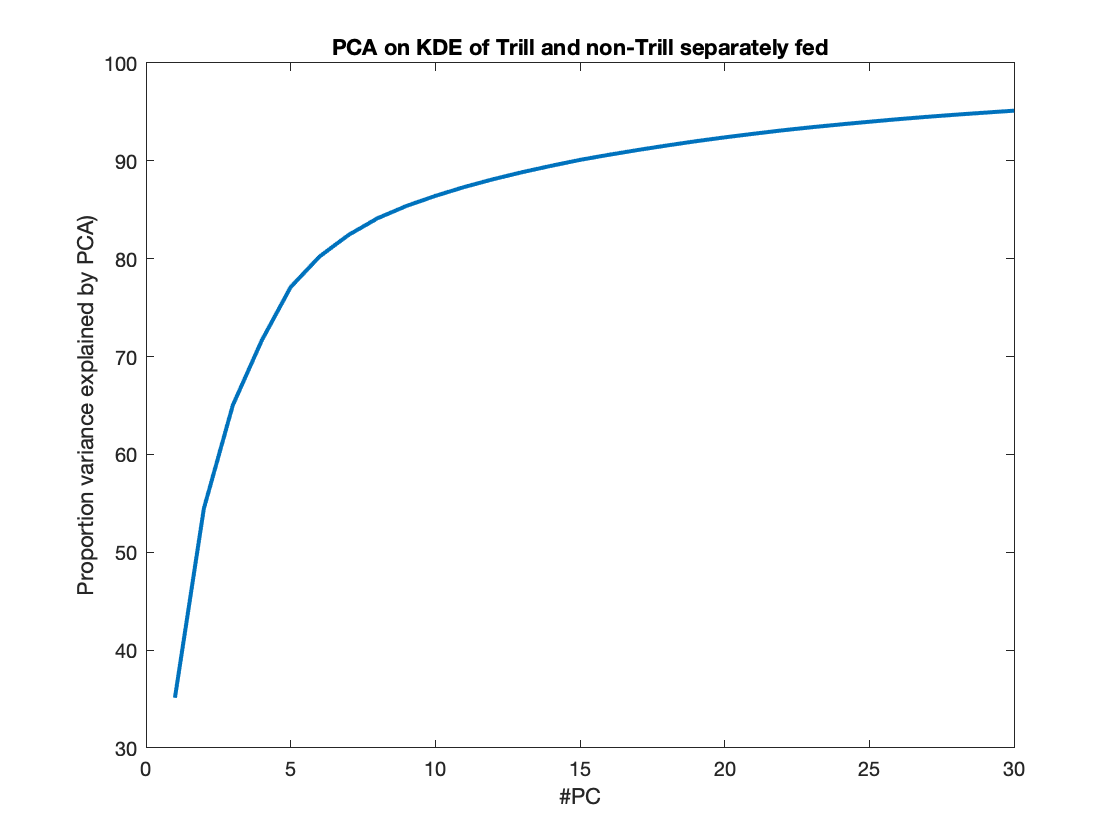

% Plot the cumulative explained variance as a function of # PCs
plot(cumsum(VarExpl), 'LineWidth',2);xlabel('#PC');ylabel('Proportion variance explained by PCA)'); xlim([0 30])
title('PCA on KDE of Trill and non-Trill separately fed')

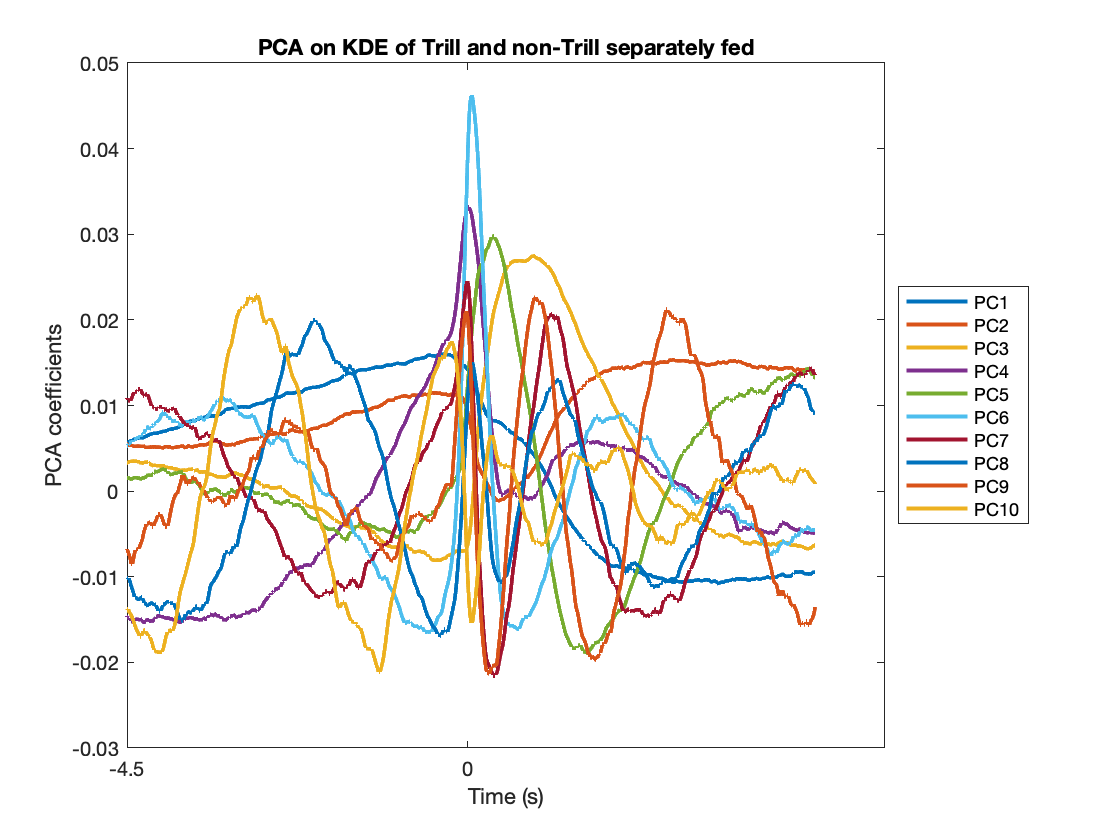

% Plot the first PC shapes
plot(PC(:,1), 'LineWidth',2);hold on;plot(PC(:,2), 'LineWidth',2);plot(PC(:,3), 'LineWidth',2);plot(PC(:,4), 'LineWidth',2);plot(PC(:,5), 'LineWidth',2);plot(PC(:,6), 'LineWidth',2);plot(PC(:,7), 'LineWidth',2);plot(PC(:,8), 'LineWidth',2);plot(PC(:,9), 'LineWidth',2);plot(PC(:,10), 'LineWidth',2);legend('PC1', 'PC2','PC3', 'PC4', 'PC5', 'PC6','PC7','PC8','PC9','PC10', 'Location', 'EastOutside'); ylabel('PCA coefficients');xlabel('Time (s)');xticks([1 -(Tstart+Trim)]);xticklabels([(Tstart+Trim)/10^3 0]);title('PCA on KDE of Trill and non-Trill separately fed')
hold off

% Plot swarmplots of PC weights (scores) with color coded if a cell is from a
% vocalizer or listener
NanTr = isnan(KDE_onset_Mat_Tr(:,1));
NannTr = isnan(KDE_onset_Mat_nTr(:,1));
OperantVocalizerCells01 = OperantVocalizer(BaorTr_0ind);
OV_cells = [OperantVocalizerCells01(~NanTr); OperantVocalizerCells01(~NannTr)]; % Vocalizer cells=1
OnT_cells = logical([zeros(sum(~NanTr),1); ones(sum(~NannTr),1)]); % Mesh on =1 <-> NonTrills=1
OVT_cells = logical(OV_cells .* (~OnT_cells));
OVnT_cells = logical(OV_cells .* OnT_cells);
OLT_cells = logical((~OV_cells) .* (~OnT_cells));
OLnT_cells = logical((~OV_cells) .* OnT_cells);
ColPC = get(groot, 'DefaultAxesColorOrder');
ScatterMarkerSz=30;
MeanMarkerSize=14;
NPC=15;
LMEpValVL = nan(NPC,1);
LMEpValTnT = nan(NPC,1);
LMEpValnull = nan(NPC,1);
LMEpValInt = nan(NPC,1);
LMpValVL_Trill = nan(NPC,1);
LMpValVL_nonTrill = nan(NPC,1);
LMCoeffVL_Trill = nan(NPC,1);
LMCoeffVL_nonTrill = nan(NPC,1);
for n=1:NPC
    swarmchart((5*n-3)*ones(sum(OVT_cells),1),Score(OVT_cells,n),ScatterMarkerSz,ColPC(2,:),'o','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5)
    hold on
    swarmchart((5*n-2)*ones(sum(OLT_cells),1),Score(OLT_cells,n),ScatterMarkerSz,ColPC(1,:),'o','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5)
    hold on
    swarmchart((5*n-1)*ones(sum(OVnT_cells),1),Score(OVnT_cells,n),ScatterMarkerSz,ColPC(3,:),'o','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5)
    hold on
    swarmchart((5*n)*ones(sum(OLnT_cells),1),Score(OLnT_cells,n),ScatterMarkerSz,ColPC(5,:),'o','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5)
    hold on
    if n==1
        legend({'Vocalizer Trills', 'Listener Trills', 'Vocalizer non-Trills', 'Listener non-Trills'})
        legend('Location', 'SouthEast','AutoUpdate','off')
    end
    errorbar((5*n-3),nanmean(Score(OVT_cells,n)),nanstd(Score(OVT_cells,n))/sum(OVT_cells)^0.5, 'dk','MarkerSize',MeanMarkerSize,'MarkerFaceColor',ColPC(2,:))
    hold on
    errorbar((5*n-2),nanmean(Score(OLT_cells,n)),nanstd(Score(OLT_cells,n))/sum(OLT_cells)^0.5, 'dk','MarkerSize',MeanMarkerSize,'MarkerFaceColor',ColPC(1,:))
    hold on
    errorbar((5*n-1),nanmean(Score(OVnT_cells,n)),nanstd(Score(OVnT_cells,n))/sum(OVnT_cells)^0.5, 'dk','MarkerSize',MeanMarkerSize,'MarkerFaceColor',ColPC(3,:))
    hold on
    errorbar((5*n),nanmean(Score(OLnT_cells,n)),nanstd(Score(OLnT_cells,n))/sum(OLnT_cells)^0.5, 'dk','MarkerSize',MeanMarkerSize,'MarkerFaceColor',ColPC(5,:))
    hold on
    Tbl =  table(Score(:,n), logical(OV_cells), logical(~OnT_cells),[ListCellsGAOp(~NanTr); ListCellsGAOp(~NannTr)], 'VariableNames', {'PCScore', 'VorL','TorNT','CellID'});
    lmefull = fitlme(Tbl, 'PCScore~VorL*TorNT+(1|CellID)');
    lmeInt = fitlme(Tbl, 'PCScore~VorL+TorNT+(1|CellID)');
    lmeVL = fitlme(Tbl, 'PCScore~TorNT+(1|CellID)');
    lmeTnT = fitlme(Tbl, 'PCScore~VorL+(1|CellID)');
    lmenull = fitlme(Tbl, 'PCScore~1+(1|CellID)');
    TestLMEnull=compare(lmenull, lmefull);
    TestLMEVL = compare(lmeVL,lmefull);
    TestLMETnT = compare(lmeTnT,lmefull);
    TestLMEInt = compare(lmeInt, lmefull);
    LMEpValVL(n) = TestLMEVL.pValue(2);
    LMEpValnull(n) = TestLMEnull.pValue(2);
    LMEpValTnT(n) = TestLMETnT.pValue(2);
    LMEpValInt(n) = TestLMEInt.pValue(2);
    if LMEpValVL(n)<0.01
        plot((5*n-3), 125,'r*','MarkerSize',15);
        fprintf(1,'\n\n\n**********PC%d: Effect of Vocalizer vs Listener\n***********', n)
        lmefull
        fprintf(1, 'Effect of VorL:')
        LMEpValVL(n)
        fprintf('Effect of Interaction:')
        LMEpValTnT(n)
        % run a model per call type
        TblTrill = table(Score(~OnT_cells,n), logical(OV_cells(~OnT_cells)), 'VariableNames', {'PCScore', 'VorL'});
        LmTrill = fitlm(TblTrill, 'PCScore~VorL')
        ATrill = LmTrill.anova;
        LMpValVL_Trill(n) = ATrill.pValue(1);
        LMCoeffVL_Trill(n) = LmTrill.Coefficients.Estimate(2);
        TblnonTrill = table(Score(OnT_cells,n), logical(OV_cells(OnT_cells)), 'VariableNames', {'PCScore', 'VorL'});
        LmnonTrill = fitlm(TblnonTrill, 'PCScore~VorL')
        AnonTrill = LmnonTrill.anova;
        LMpValVL_nonTrill(n) = AnonTrill.pValue(1);
        LMCoeffVL_nonTrill(n) = LmnonTrill.Coefficients.Estimate(2);
    end
    if LMEpValInt(n)<0.01
        plot((5*n-2), 125,'g*','MarkerSize',15);
        if isnan(LMpValVL_Trill(n))
            % run a model per call type
            TblTrill = table(Score(~OnT_cells,n), logical(OV_cells(~OnT_cells)), 'VariableNames', {'PCScore', 'VorL'});
            LmTrill = fitlm(TblTrill, 'PCScore~VorL')
            ATrill = LmTrill.anova;
            LMpValVL_Trill(n) = ATrill.pValue(1);
            LMCoeffVL_Trill(n) = LmTrill.Coefficients.Estimate(2);
            TblnonTrill = table(Score(OnT_cells,n), logical(OV_cells(OnT_cells)), 'VariableNames', {'PCScore', 'VorL'});
            LmnonTrill = fitlm(TblnonTrill, 'PCScore~VorL')
            AnonTrill = LmnonTrill.anova;
            LMpValVL_nonTrill(n) = AnonTrill.pValue(1);
            LMCoeffVL_nonTrill(n) = LmnonTrill.Coefficients.Estimate(2);
        end

    end
    if LMEpValTnT(n)<0.01
        plot((5*n-1), 125,'b*','MarkerSize',15);
    end
    if LMEpValnull(n)<0.01
        plot((5*n-1.5), 140,'k*','MarkerSize',15);
    end


end




**********PC4: Effect of Vocalizer vs Listener
***********

lmefull = Linear mixed-effects model fit by ML

Model information:
    Number of observations            1634
    Fixed effects coefficients           4
    Random effects coefficients        954
    Covariance parameters                2

Formula:
    PCScore ~ 1 + VorL*TorNT + (1 | CellID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    14953    14985    -7470.4          14941   

Fixed effects coefficients (95% CIs):
    Name                      Estimate    SE        tStat      DF      pValue        Lower      Upper  
    {'(Intercept)'   }         -4.183     1.3466    -3.1064    1630     0.0019267    -6.8243    -1.5418
    {'VorL_1'        }          14.96     1.7583     8.5084    1630    3.9345e-17     11.512     18.409
    {'TorNT_1'       }         1.0328     1.7295    0.59717    1630       0.55048    -2.3595     4.4251
    {'VorL_1:TorNT_1'}        -15.968     2.2298

Effect of VorL:

ans = 1.1102e-16

Effect of Interaction:

ans = 0

LmTrill = Linear regression model:
    PCScore ~ 1 + VorL

Estimated Coefficients:
                   Estimate      SE       tStat      pValue  
                   ________    ______    _______    _________

    (Intercept)    -3.1377     1.1072    -2.8339    0.0047008
    VorL_1         -1.1269     1.3986    -0.8057      0.42063


Number of observations: 900, Error degrees of freedom: 898
Root Mean Squared Error: 20.3
R-squared: 0.000722,  Adjusted R-Squared: -0.00039
F-statistic vs. constant model: 0.649, p-value = 0.421

LmnonTrill = Linear regression model:
    PCScore ~ 1 + VorL

Estimated Coefficients:
                   Estimate      SE       tStat       pValue  
                   ________    ______    _______    __________

    (Intercept)    -4.1011     1.5482    -2.6489     0.0082486
    VorL_1          15.046     2.0228     7.4382    2.8632e-13


Number of observations: 734, Error degrees of freedom: 732
Root Mean Squared Error: 27
R-squared: 0.0703,  Adjusted R-Squared: 0.069
F-statistic vs. constant model: 55.3, p-value = 2.86e-13




**********PC5: Effect of Vocalizer vs Listener
***********

lmefull = Linear mixed-effects model fit by ML

Model information:
    Number of observations            1634
    Fixed effects coefficients           4
    Random effects coefficients        954
    Covariance parameters                2

Formula:
    PCScore ~ 1 + VorL*TorNT + (1 | CellID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    14730    14762    -7358.9          14718   

Fixed effects coefficients (95% CIs):
    Name                      Estimate    SE        tStat      DF      pValue        Lower      Upper  
    {'(Intercept)'   }        -3.1214     1.2635    -2.4704    1630      0.013598    -5.5997    -0.6431
    {'VorL_1'        }         5.5792     1.6484     3.3846    1630    0.00072981      2.346     8.8125
    {'TorNT_1'       }         4.1219     1.5526     2.6549    1630     0.0080103     1.0767     7.1671
    {'VorL_1:TorNT_1'}        -7.6728     2.0043

Effect of VorL:

ans = 3.7769e-04

Effect of Interaction:

ans = 6.2102e-04

LmTrill = Linear regression model:
    PCScore ~ 1 + VorL

Estimated Coefficients:
                   Estimate      SE       tStat     pValue 
                   ________    ______    _______    _______

    (Intercept)     1.0351     1.0562    0.98007    0.32731
    VorL_1         -2.0705     1.3342    -1.5519    0.12104


Number of observations: 900, Error degrees of freedom: 898
Root Mean Squared Error: 19.4
R-squared: 0.00267,  Adjusted R-Squared: 0.00156
F-statistic vs. constant model: 2.41, p-value = 0.121

LmnonTrill = Linear regression model:
    PCScore ~ 1 + VorL

Estimated Coefficients:
                   Estimate      SE       tStat      pValue  
                   ________    ______    _______    _________

    (Intercept)    -2.9975     1.4371    -2.0858      0.03734
    VorL_1          5.6658     1.8776     3.0177    0.0026356


Number of observations: 734, Error degrees of freedom: 732
Root Mean Squared Error: 25.1
R-squared: 0.0123,  Adjusted R-Squared: 0.0109
F-statistic vs. constant model: 9.11, p-value = 0.00264




**********PC6: Effect of Vocalizer vs Listener
***********

lmefull = Linear mixed-effects model fit by ML

Model information:
    Number of observations            1634
    Fixed effects coefficients           4
    Random effects coefficients        954
    Covariance parameters                2

Formula:
    PCScore ~ 1 + VorL*TorNT + (1 | CellID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    13845    13877    -6916.3          13833   

Fixed effects coefficients (95% CIs):
    Name                      Estimate    SE         tStat      DF      pValue     Lower       Upper  
    {'(Intercept)'   }        -1.0543     0.95759     -1.101    1630    0.27107     -2.9325    0.82396
    {'VorL_1'        }         1.8227      1.2508     1.4573    1630    0.14522    -0.63053      4.276
    {'TorNT_1'       }        -1.4259      1.2611    -1.1307    1630    0.25834     -3.8994     1.0476
    {'VorL_1:TorNT_1'}         2.1094      1.6245   

Effect of VorL:

ans = 0.0016

Effect of Interaction:

ans = 0.4243

LmTrill = Linear regression model:
    PCScore ~ 1 + VorL

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________

    (Intercept)    -2.5046     0.85786    -2.9196     0.0035921
    VorL_1          3.9192      1.0837     3.6166    0.00031514


Number of observations: 900, Error degrees of freedom: 898
Root Mean Squared Error: 15.7
R-squared: 0.0144,  Adjusted R-Squared: 0.0133
F-statistic vs. constant model: 13.1, p-value = 0.000315

LmnonTrill = Linear regression model:
    PCScore ~ 1 + VorL

Estimated Coefficients:
                   Estimate      SE       tStat     pValue 
                   ________    ______    _______    _______

    (Intercept)    -1.1259     1.0252    -1.0982    0.27249
    VorL_1          2.0235     1.3394     1.5107    0.13129


Number of observations: 734, Error degrees of freedom: 732
Root Mean Squared Error: 17.9
R-squared: 0.00311,  Adjusted R-Squared: 0.00175
F-statistic vs. constant model: 2.28, p-value = 0.131




**********PC7: Effect of Vocalizer vs Listener
***********

lmefull = Linear mixed-effects model fit by ML

Model information:
    Number of observations            1634
    Fixed effects coefficients           4
    Random effects coefficients        954
    Covariance parameters                2

Formula:
    PCScore ~ 1 + VorL*TorNT + (1 | CellID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    13241    13273    -6614.5          13229   

Fixed effects coefficients (95% CIs):
    Name                      Estimate    SE         tStat      DF      pValue        Lower      Upper   
    {'(Intercept)'   }        -3.5834     0.79518    -4.5063    1630    7.0658e-06     -5.143     -2.0237
    {'VorL_1'        }         6.2663      1.0389     6.0318    1630    2.0022e-09     4.2286       8.304
    {'TorNT_1'       }          1.712      1.0783     1.5877    1630       0.11255     -0.403      3.8269
    {'VorL_1:TorNT_1'}        -3.3997   

Effect of VorL:

ans = 3.6707e-10

Effect of Interaction:

ans = 0.0450

LmTrill = Linear regression model:
    PCScore ~ 1 + VorL

Estimated Coefficients:
                   Estimate      SE        tStat      pValue  
                   ________    _______    _______    _________

    (Intercept)    -1.8687     0.64663    -2.8899    0.0039461
    VorL_1          2.8754     0.81684     3.5202    0.0004529


Number of observations: 900, Error degrees of freedom: 898
Root Mean Squared Error: 11.9
R-squared: 0.0136,  Adjusted R-Squared: 0.0125
F-statistic vs. constant model: 12.4, p-value = 0.000453

LmnonTrill = Linear regression model:
    PCScore ~ 1 + VorL

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________

    (Intercept)    -3.5695     0.91908    -3.8838    0.00011213
    VorL_1          6.2329      1.2008     5.1907    2.7173e-07


Number of observations: 734, Error degrees of freedom: 732
Root Mean Squared Error: 16
R-squared: 0.0355,  Adjusted R-Squared: 0.0342
F-statistic vs. constant model: 26.9, p-value = 2.72e-07




**********PC13: Effect of Vocalizer vs Listener
***********

lmefull = Linear mixed-effects model fit by ML

Model information:
    Number of observations            1634
    Fixed effects coefficients           4
    Random effects coefficients        954
    Covariance parameters                2

Formula:
    PCScore ~ 1 + VorL*TorNT + (1 | CellID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    11444    11477    -5716.2          11432   

Fixed effects coefficients (95% CIs):
    Name                      Estimate    SE         tStat       DF      pValue       Lower        Upper   
    {'(Intercept)'   }        0.80313      0.4588      1.7505    1630     0.080216    -0.096759       1.703
    {'VorL_1'        }        -1.6067     0.59942     -2.6805    1630    0.0074256      -2.7825    -0.43103
    {'TorNT_1'       }        0.03835      0.6332    0.060566    1630      0.95171      -1.2036      1.2803
    {'VorL_1:TorNT_1'}        0.

Effect of VorL:

ans = 0.0030

Effect of Interaction:

ans = 0.6410

LmTrill = Linear regression model:
    PCScore ~ 1 + VorL

Estimated Coefficients:
                   Estimate      SE        tStat      pValue 
                   ________    _______    _______    ________

    (Intercept)    0.84148     0.41059     2.0495    0.040707
    VorL_1          -1.163     0.51867    -2.2423    0.025186


Number of observations: 900, Error degrees of freedom: 898
Root Mean Squared Error: 7.53
R-squared: 0.00557,  Adjusted R-Squared: 0.00446
F-statistic vs. constant model: 5.03, p-value = 0.0252

LmnonTrill = Linear regression model:
    PCScore ~ 1 + VorL

Estimated Coefficients:
                   Estimate      SE        tStat      pValue 
                   ________    _______    _______    ________

    (Intercept)    0.80313     0.49121      1.635     0.10248
    VorL_1         -1.6067     0.64178    -2.5036    0.012511


Number of observations: 734, Error degrees of freedom: 732
Root Mean Squared Error: 8.56
R-squared: 0.00849,  Adjusted R-Squared: 0.00714
F-statistic vs. constant model: 6.27, p-value = 0.0125

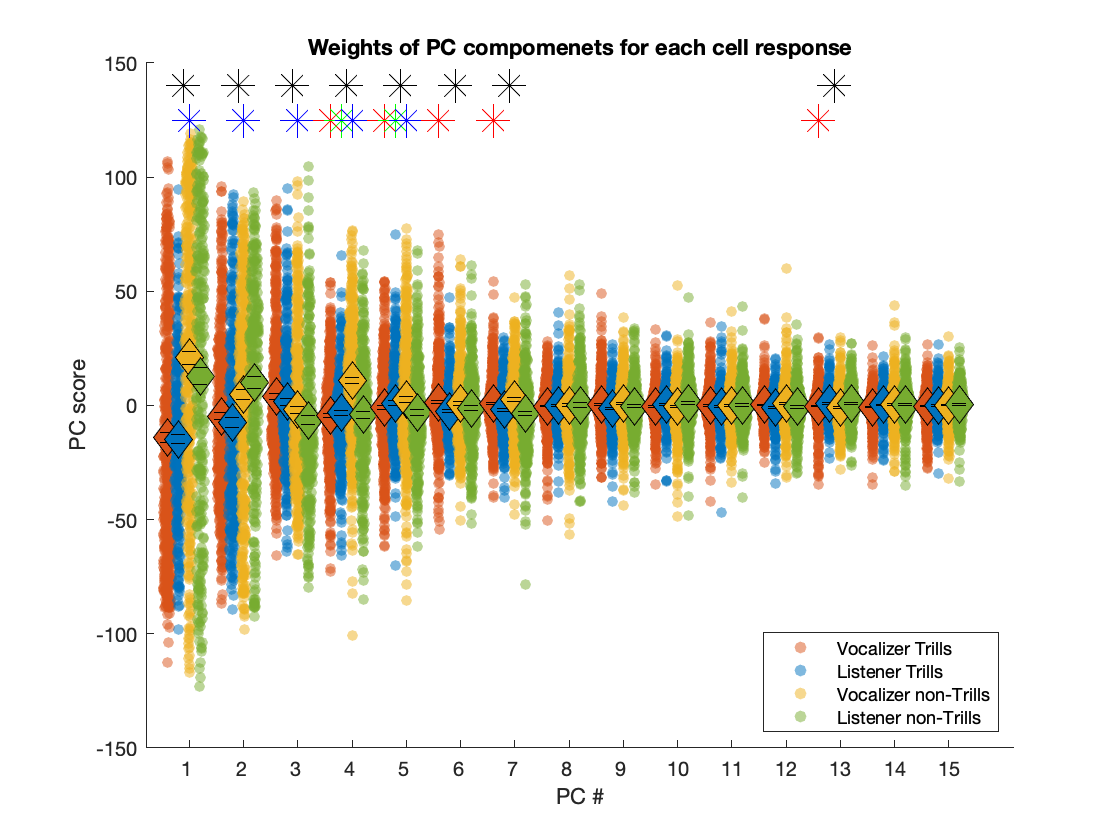

set(gca, 'XTick', 5*(1:NPC)-1, 'XTickLabel',1:NPC)
xlabel('PC #')
ylabel('PC score')
title('Weights of PC compomenets for each cell response')
hold off

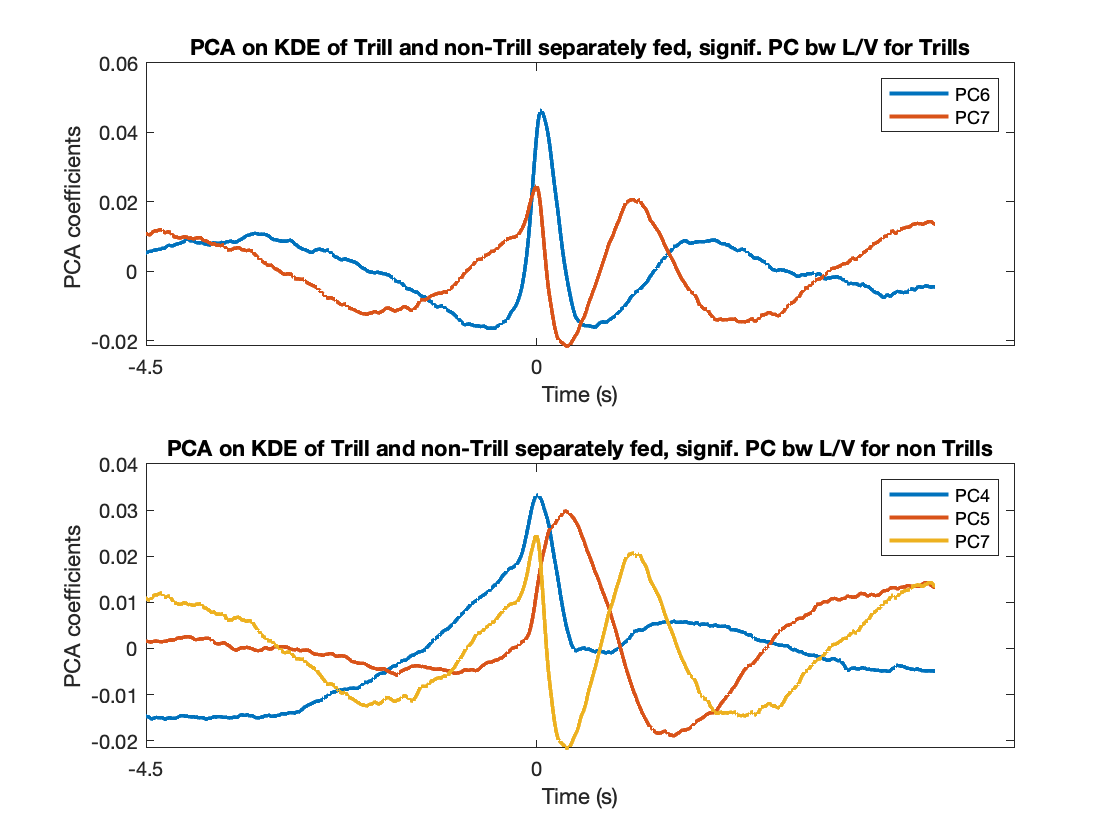

% Plot the PC shapes significant for the effect of Vocalizer/Listner in
% linear models
PCSigT = find(LMpValVL_Trill<0.01);
PCSigNT = find(LMpValVL_nonTrill<0.01);
tiledlayout(2,1)
nexttile
for n=1:length(PCSigT)
    legend('AutoUpdate',"on")
    plot(PC(:,PCSigT(n)), 'LineWidth',2, 'DisplayName',sprintf('PC%d',PCSigT(n)) );
    hold on;
end
ylabel('PCA coefficients ');
xlabel('Time (s)');
xticks([1 -(Tstart+Trim)]);xticklabels([(Tstart+Trim)/10^3 0]);
title('PCA on KDE of Trill and non-Trill separately fed, signif. PC bw L/V for Trills')
hold off
nexttile
for n=1:length(PCSigNT)
    legend('AutoUpdate',"on")
    plot(PC(:,PCSigNT(n)), 'LineWidth',2, 'DisplayName',sprintf('PC%d',PCSigNT(n)) );
    hold on;
end
ylabel('PCA coefficients');
xlabel('Time (s)');
xticks([1 -(Tstart+Trim)]);xticklabels([(Tstart+Trim)/10^3 0]);
title('PCA on KDE of Trill and non-Trill separately fed, signif. PC bw L/V for non Trills')
hold off

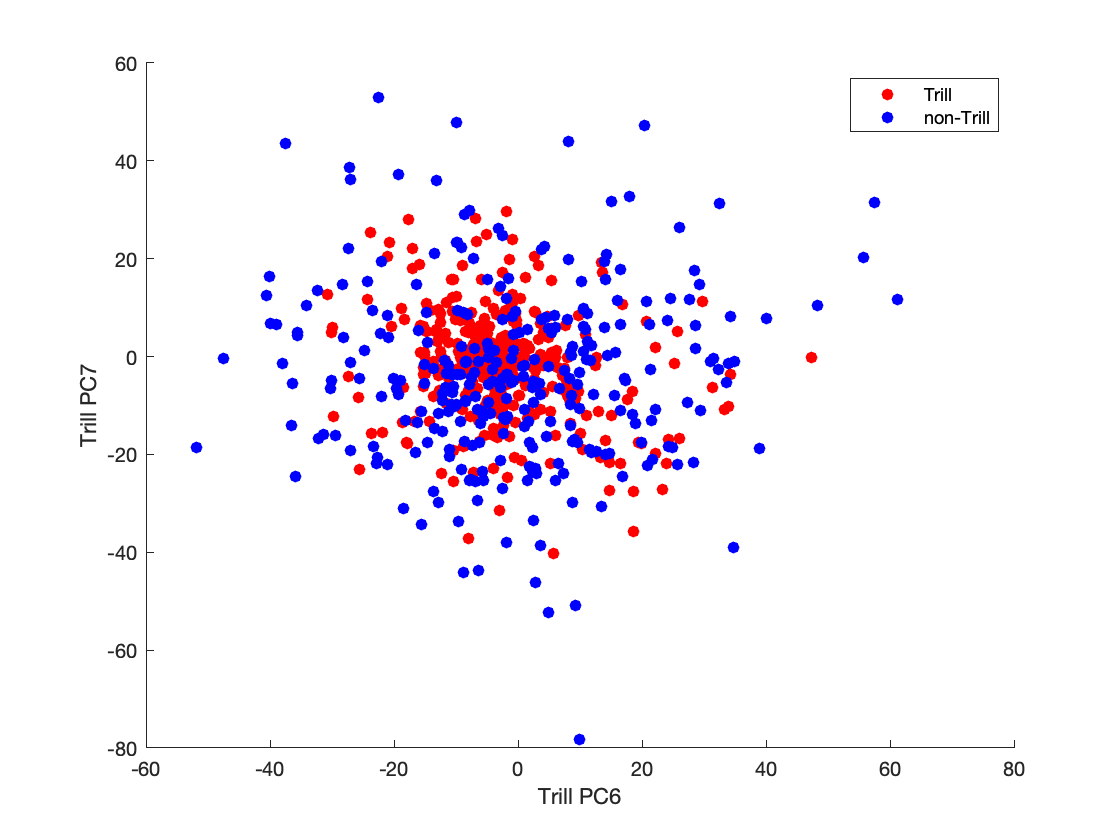

% Now we want to model the distribution of responses in the PC space for
% listener neurons
% first let's plot the scatters of that distribution

figure()
scatter(Score(OLT_cells,PCSigT(1)),Score(OLT_cells,PCSigT(2)),'ro', 'filled')
hold on
scatter(Score(OLnT_cells,PCSigT(1)),Score(OLnT_cells,PCSigT(2)), 'bo', 'filled')
legend({'Trill', 'non-Trill'})
xlabel(sprintf('Trill PC%d',PCSigT(1)))
ylabel(sprintf('Trill PC%d',PCSigT(2)))
hold off

scatter(Score(OLT_cells,PCSigNT(1)),Score(OLT_cells,PCSigNT(2)),'ro', 'filled')
hold on
scatter(Score(OLnT_cells,PCSigNT(1)),Score(OLnT_cells,PCSigNT(2)), 'bo', 'filled')
legend({'Trill', 'non-Trill'})
xlabel(sprintf('non-Trill PC%d',PCSigNT(1)))
ylabel(sprintf('non-Trill PC%d',PCSigNT(2)))
hold off

scatter(Score(OLT_cells,PCSigNT(1)),Score(OLT_cells,PCSigNT(3)),'ro', 'filled')
hold on
scatter(Score(OLnT_cells,PCSigNT(1)),Score(OLnT_cells,PCSigNT(3)), 'bo', 'filled')
legend({'Trill', 'non-Trill'})
xlabel(sprintf('non-Trill PC%d',PCSigNT(1)))
ylabel(sprintf('non-Trill PC%d',PCSigNT(3)))

hold off

% Now fit with a Gaussian Mixture model the distribution of Listener cells, split between Trills and non Trills and find the best number of components
AIC_T = zeros(1,10);
AIC_NT = zeros(1,10);
GMM_L_T = cell(1,10);
GMM_L_NT = cell(1,10);
options = statset('MaxIter',500);
for k = 1:10
    GMM_L_T{k} = fitgmdist(Score(OLT_cells,PCSigT),k,'Options',options);
    AIC_T(k)= GMM_L_T{k}.AIC;
    GMM_L_NT{k} = fitgmdist(Score(OLnT_cells,PCSigNT),k,'Options',options);
    AIC_NT(k)= GMM_L_T{k}.AIC;
end
figure
tiledlayout(2,1)
nexttile
plot(AIC_T, 'LineWidth',2)
xlabel('# components of GMM')
ylabel('AIC Trills')
nexttile
plot(AIC_NT, 'LineWidth',2)
xlabel('# components of GMM')
ylabel('AIC non-Trills')

[minAIC,numComponents] = min(AIC_T);
numComponents

numComponents = 3

[minAIC,numComponents] = min(AIC_NT);
numComponents

numComponents = 3

Plot the scatter of cells in PC space and overlay the contours of the Gaussian mixture models. For illustration purposes only I recalculate a GMM with only the 2 considered dimensions for Non-Trill that have 3 dimensions

% Values of Score for each Significant PC
figure()
scatter(Score(OLT_cells,PCSigT(1)),Score(OLT_cells,PCSigT(2)),'ko', 'filled')
hold on
scatter(Score(OVT_cells,PCSigT(1)),Score(OVT_cells,PCSigT(2)), 'ro', 'filled')
hold on

 
gmPDF = @(x,y) arrayfun(@(x0,y0) pdf(GMM_L_T{2},[x0 y0]),x,y);
g = gca;
fcontour(gmPDF,[g.XLim g.YLim], 'LineWidth',2)
legend({'Listener Trills', 'Vocalizer Trills', 'Listener GMM'}, 'Location', 'southoutside')
xlabel(sprintf('PC%d',PCSigT(1)))
ylabel(sprintf('PC%d',PCSigT(2)))
title(sprintf('{\b Scatter Plot PCScore %d and %d for Trills and Fitted Gaussian Mixture Contours}',PCSigT(1),PCSigT(2)))
hold off

% Minimum values of Score for each Significant PC Listener cells only plot
figure()
scatter(Score(OLT_cells,PCSigT(1)),Score(OLT_cells,PCSigT(2)),'ko', 'filled')
hold on

 
gmPDF = @(x,y) arrayfun(@(x0,y0) pdf(GMM_L_T{k},[x0 y0]),x,y);
g2 = gca;
g2.XLim = g.XLim;
g2.YLim = g.YLim;
fcontour(gmPDF,[g.XLim g.YLim], 'LineWidth',2)
legend({'Listener Trills', 'Listener GMM'}, 'Location', 'southoutside')
xlabel(sprintf('PC%d',PCSigT(1)))
ylabel(sprintf('PC%d',PCSigT(2)))

title(sprintf('{\b Scatter Plot PCScore %d and %d for Trills and Fitted Gaussian Mixture Contours}',PCSigT(1),PCSigT(2)))
hold off

% Minimum values of Score for each Significant PC
GMM_LnT_local = fitgmdist(Score(OLnT_cells,PCSigNT([1 2])),2,'Options',options);
figure()
scatter(Score(OLnT_cells,PCSigNT(1)),Score(OLnT_cells,PCSigNT(2)),'ko', 'filled')
hold on
scatter(Score(logical(OVnT_cells),PCSigNT(1)),Score(logical(OVnT_cells),PCSigNT(2)), 'ro', 'filled')
hold on

 
gmPDF = @(x,y) arrayfun(@(x0,y0) pdf(GMM_LnT_local,[x0 y0]),x,y);
g = gca;
fcontour(gmPDF,[g.XLim g.YLim], 'LineWidth',2)
legend({'Listener non-Trills', 'Vocalizer non-Trills', 'Listener GMM'}, 'Location', 'southoutside')
xlabel(sprintf('PC%d',PCSigNT(1)))
ylabel(sprintf('PC%d',PCSigNT(2)))
title(sprintf('{\b Scatter Plot PCScore %d and %d for NonTrills and Fitted Gaussian Mixture Contours}',PCSigNT(1),PCSigNT(2)))
hold off

% Minimum values of Score for each Significant PC
GMM_LnT_local = fitgmdist(Score(OLnT_cells,PCSigNT([1 3])),2,'Options',options);
figure()
scatter(Score(OLnT_cells,PCSigNT(1)),Score(OLnT_cells,PCSigNT(3)),'ko', 'filled')
hold on
scatter(Score(OVnT_cells,PCSigNT(1)),Score(OVnT_cells,PCSigNT(3)), 'ro', 'filled')
hold on

 
gmPDF = @(x,y) arrayfun(@(x0,y0) pdf(GMM_LnT_local,[x0 y0]),x,y);
g = gca;
fcontour(gmPDF,[g.XLim g.YLim], 'LineWidth',2)
legend({'Listener non-Trills', 'Vocalizer non-Trills', 'Listener GMM'}, 'Location', 'southoutside')
xlabel(sprintf('PC%d',PCSigNT(1)))
ylabel(sprintf('PC%d',PCSigNT(3)))
title(sprintf('{\b Scatter Plot PCScore %d and %d for non-Trill responses and Fitted Gaussian Mixture Contours}',PCSigNT(1),PCSigNT(3)))
hold off

% Let's find the vocalizer neurons that significantly diverge from the
% distribution of listener cells in the PC space, for this calculate the
% mahalanobis distance of each point from the Gaussian Mixture model
k=2;
 % Take the minimum of the distance to the 2 Gaussian distributions
MahalDistanceVT = min(mahal(GMM_L_T{k},Score(OVT_cells,PCSigT)),[],2);
MahalDistanceLT = min(mahal(GMM_L_T{k},Score(OLT_cells,PCSigT)),[],2);
MahalDistanceVnT = min(mahal(GMM_L_NT{k},Score(OVnT_cells,PCSigNT)),[],2);
MahalDistanceLnT = min(mahal(GMM_L_NT{k},Score(OLnT_cells,PCSigNT)),[],2);
MahalDistanceV = [MahalDistanceVT; MahalDistanceVnT];
MahalDistanceL = [MahalDistanceLT; MahalDistanceLnT];
MahalDistance = nan(size(Score,1),1);
MahalDistance(OVT_cells) = MahalDistanceVT;
MahalDistance(OLT_cells) = MahalDistanceLT;
MahalDistance(OVnT_cells) = MahalDistanceVnT;
MahalDistance(OLnT_cells) = MahalDistanceLnT;

% Visualize the outstanding cells: Values of Score for each Significant PC
figure()
scatter(Score(OLT_cells,PCSigT(1)),Score(OLT_cells,PCSigT(2)),'ko', 'filled')
hold on
ScoreOVT = Score(OVT_cells,PCSigT(1:2));
scatter(ScoreOVT(MahalDistanceVT<=4,1),ScoreOVT(MahalDistanceVT<=4,2), 'ro', 'filled')
hold on
scatter(ScoreOVT(MahalDistanceVT>4,1),ScoreOVT(MahalDistanceVT>4,2), 'go', 'filled')
hold on

 
gmPDF = @(x,y) arrayfun(@(x0,y0) pdf(GMM_L_T{2},[x0 y0]),x,y);
g = gca;
fcontour(gmPDF,[g.XLim g.YLim], 'LineWidth',2)
legend({'Listener Trills', 'Vocalizer Trills', 'Outstanding Vocalizer Trills', 'Listener GMM'}, 'Location', 'southoutside')
xlabel(sprintf('PC%d',PCSigT(1)))
ylabel(sprintf('PC%d',PCSigT(2)))
title(sprintf('{\b Scatter Plot PCScore %d and %d for Trills and Fitted Gaussian Mixture Contours}',PCSigT(1),PCSigT(2)))
hold off

% We only want to select the outstanding responses that are in the proper
% quarter of PC values (the LM coefficients indicate whether an increase or
% decrease of the PC is significant in vocalizer as compared to outsider).
figure()
scatter(Score(OLT_cells,PCSigT(1)),Score(OLT_cells,PCSigT(2)),'ko', 'filled')
hold on
ScoreOVT = Score(OVT_cells,PCSigT(1:2));
% Outstanding cells that respect the effect direction of the LM
OutstandingT = logical((MahalDistanceVT>4).*((sign(LMCoeffVL_Trill(PCSigT(1))).*ScoreOVT(:,1)>0)+(sign(LMCoeffVL_Trill(PCSigT(2))).*ScoreOVT(:,2)>0)));
scatter(ScoreOVT(~OutstandingT,1),ScoreOVT(~OutstandingT,2), 'ro', 'filled')
hold on
scatter(ScoreOVT(OutstandingT,1),ScoreOVT(OutstandingT,2), 'go', 'filled')
hold on

 
gmPDF = @(x,y) arrayfun(@(x0,y0) pdf(GMM_L_T{2},[x0 y0]),x,y);
g = gca;
fcontour(gmPDF,[g.XLim g.YLim], 'LineWidth',2)
legend({'Listener Trills', 'Vocalizer Trills', 'Outstanding Vocalizer Trills', 'Listener GMM'}, 'Location', 'southoutside')
xlabel(sprintf('PC%d',PCSigT(1)))
ylabel(sprintf('PC%d',PCSigT(2)))
title(sprintf('{\b Scatter Plot PCScore %d and %d for Trills and Fitted Gaussian Mixture Contours}',PCSigT(1),PCSigT(2)))
hold off

% some cells are represented by 2 Mahalanobis distance (KDE nTr and KdeTr)
% some by only one. First look at histograms of Mahalanobis distance for all cells
figure()
tiledlayout(2,1)
nexttile
histogram(MahalDistanceLT, 'BinWidth',1, 'Normalization', 'cdf')
hold on
histogram(MahalDistanceVT, 'BinWidth',1, 'Normalization', 'cdf')
xlabel('Shortest Squared Mahalanobis distance of cell Trill KDE to GMM Trill')
ylabel('Cumulative Density Function')
legend('Listener','Vocalizer')
hold on
VL = vline(2^2);
VL.LineWidth=2;
hold off
title('Mahalanobis distance for cells with Trill activity')
nexttile
histogram(MahalDistanceLnT, 'BinWidth',0.5, 'Normalization', 'cdf')
hold on
histogram(MahalDistanceVnT, 'BinWidth',0.5, 'Normalization', 'cdf')
xlabel('Shortest Squared Mahalanobis distance of cell non-Trill KDE to GMM non-Trill')
ylabel('Cumulative Density Function')
legend('Listener','Vocalizer')
hold on
VL = vline(2^2);
VL.LineWidth=2;
hold off
title('Mahalanobis distance for cells with non-Trill activity')

% Now scatter for cells that have distances for both Tr and nTr
%[ListCellsGAOp(~NanTr); ListCellsGAOp(~NannTr)]
% Indices of cells as organized in Score
CellID = [find(~NanTr); find(~NannTr)];
% Indices of Vocalizer cells in Score that have both Tr and nTr
CellIDVTrnTr = find(~NanTr .* ~NannTr .* OperantVocalizerCells01);
MahalDistanceVTrnTr = nan(length(CellIDVTrnTr),2);
for cc=1:length(CellIDVTrnTr)
    MahalDistanceVTrnTr(cc,:) = MahalDistance(CellID == CellIDVTrnTr(cc));
end
% Indices of Listener cells in Score that have both Tr and nTr
CellIDLTrnTr = find(~NanTr .* ~NannTr .* ~OperantVocalizerCells01);
MahalDistanceLTrnTr = nan(length(CellIDLTrnTr),2);
for cc=1:length(CellIDLTrnTr)
    MahalDistanceLTrnTr(cc,:) = MahalDistance(CellID == CellIDLTrnTr(cc));
end

% Indices of Vocalizer cells in Score that have only Tr and not nTr
CellIDVTr = find(~NanTr .* NannTr .* OperantVocalizerCells01);
MahalDistanceVTr = nan(length(CellIDVTr),1);
for cc=1:length(CellIDVTr)
    MahalDistanceVTr(cc) = MahalDistance(CellID == CellIDVTr(cc));
end
% Indices of Listener cells in Score that have only Tr and not nTr
CellIDLTr = find(~NanTr .* NannTr .* ~OperantVocalizerCells01);
MahalDistanceLTr = nan(length(CellIDLTr),1);
for cc=1:length(CellIDLTr)
    MahalDistanceLTr(cc) = MahalDistance(CellID == CellIDLTr(cc));
end

% Indices of Vocalizer cells in Score that have only nTr and not Tr
CellIDVnTr = find(NanTr .* ~NannTr .* OperantVocalizerCells01);
MahalDistanceVnTr = nan(length(CellIDVnTr),1);
for cc=1:length(CellIDVnTr)
    MahalDistanceVnTr(cc) = MahalDistance(CellID == CellIDVnTr(cc));
end
% Indices of Listener cells in Score that have only nTr and  not Tr
CellIDLnTr = find(NanTr .* ~NannTr .* ~OperantVocalizerCells01);
MahalDistanceLnTr = nan(length(CellIDLnTr),1);
for cc=1:length(CellIDLnTr)
    MahalDistanceLnTr(cc) = MahalDistance(CellID == CellIDLnTr(cc));
end

figure()
scatter(MahalDistanceVTrnTr(:,1), MahalDistanceVTrnTr(:,2), 'ko', 'filled')
hold on
VL = vline(2^2);
VL.LineWidth=2;
hold on
HL = hline(2^2);
HL.LineWidth = 2;
xlabel('Squared Mahalanobis distance Trill KDE')
ylabel('Squared Mahalanobis distance non-Trill KDE')
title('Vocalizer cells')
hold off

scatter(MahalDistanceLTrnTr(:,1), MahalDistanceLTrnTr(:,2), 'ko', 'filled')
ylim([0 15])
xlim([0 30])
hold on
VL = vline(2^2);
VL.LineWidth=2;
hold on
HL = hline(2^2);
HL.LineWidth = 2;
xlabel('Squared Mahalanobis distance Trill KDE')
ylabel('Squared Mahalanobis distance non-Trill KDE')
title('Listener cells')
hold off

figure()
Colors = get(groot, 'DefaultAxesColorOrder');
scatter(MahalDistanceLTrnTr(:,1), MahalDistanceLTrnTr(:,2), 'o', 'filled')
hold on
scatter(MahalDistanceVTrnTr(:,1), MahalDistanceVTrnTr(:,2), 'o', 'filled')
hold on
legend('Listener Cells','Vocalizer Cells', 'AutoUpdate', 'off')

hold on
scatter(MahalDistanceLTr, -1.*ones(length(MahalDistanceLTr),1), [],Colors(1,:),'filled')
hold on
scatter(-1.*ones(length(MahalDistanceLnTr),1),MahalDistanceLnTr, [],Colors(1,:), 'filled')
hold on
scatter(MahalDistanceVTr, -1.*ones(length(MahalDistanceVTr),1), [],Colors(2,:), 'filled')
hold on
scatter(-1.*ones(length(MahalDistanceVnTr),1),MahalDistanceVnTr,  [],Colors(2,:), 'filled')
VL = vline(2^2, 'k:');
VL.LineWidth=2;
hold on
HL = hline(2^2,'k:');
HL.LineWidth = 2;
HL = line([-1 2^2], max(MahalDistanceLnT).*[1 1],'LineStyle',':', 'LineWidth',2, 'Color',Colors(1,:));
VL = line(max(MahalDistanceLT).*[1 1], [-1 2^2],'LineStyle',':', 'LineWidth',2, 'Color',Colors(1,:));
xlim([-1 30])
ylim([-1 15])
xlabel('Squared Mahalanobis distance Trill KDE')
ylabel('Squared Mahalanobis distance non-Trill KDE')

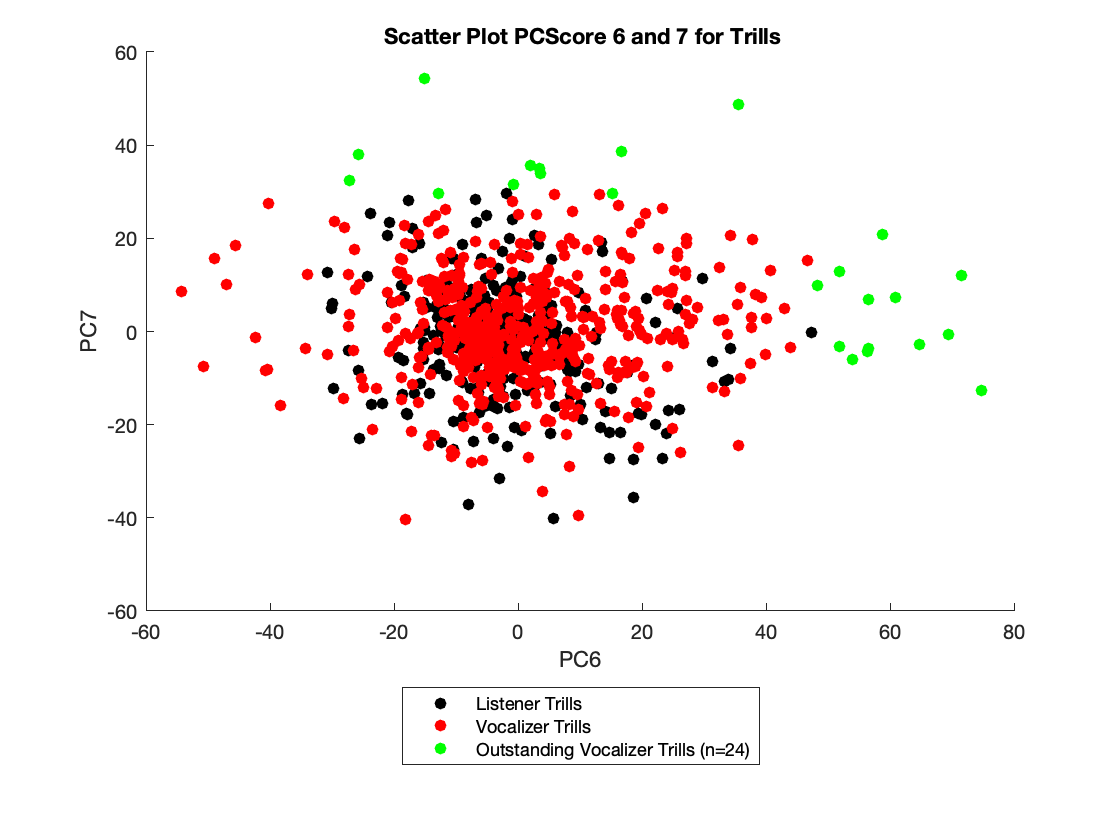

% What if we use the distribution of Listener cells as the null
% distribution and select cells that are in the 1percentile of that
% distribution?
% Outstanding cells that are in the 1percentile of the Listener
% distribution of values
PvalLim = 0.01;
ScoreOVT = Score(OVT_cells,PCSigT);
ScoreOLT = Score(OLT_cells,PCSigT);
% first calculate the probability for each vocalizer response and each PC
% of have a score larger than the expected one from the distribution of
% Listner retsponses
OutstandingT_pvalue = nan(size(ScoreOVT,1),length(PCSigT));
for rr=1:size(ScoreOVT,1)
    for nPC = 1:length(PCSigT)
        OutstandingT_pvalue(rr,nPC) = 1-(sum(sign(LMCoeffVL_Trill(PCSigT(nPC))).*(ScoreOVT(rr,nPC)-ScoreOLT(:,nPC))>0)/sum(OLT_cells));
    end
end

% Now correct that probability for False discovery rate (True proba =
% p*(Num_comparisons-rank))
[~,Ord]=sort([OutstandingT_pvalue(:,1);OutstandingT_pvalue(:,2)]);
Ord(Ord==length(Ord)) = length(Ord)-1;
Ord1 = Ord(1:size(ScoreOVT,1));
Ord2 = Ord(1+size(ScoreOVT,1) : end);
OutstandingT_pvalueFDR = [OutstandingT_pvalue(:,1).*(2*size(ScoreOVT,1)-Ord1) OutstandingT_pvalue(:,2).*(2*size(ScoreOVT,1)-Ord2)];
OutstandingT = OutstandingT_pvalueFDR<PvalLim;

% Bonferroni correction is another alternative
%  OutstandingT = (OutstandingT_pvalue.*2*size(ScoreOVT,1))<PvalLim;

 % No correction
% OutstandingT = (OutstandingT_pvalue)<PvalLim;

figure()
scatter(Score(OLT_cells,PCSigT(1)),Score(OLT_cells,PCSigT(2)),'ko', 'filled')
hold on


scatter(ScoreOVT(~sum(OutstandingT,2),1),ScoreOVT(~sum(OutstandingT,2),2), 'ro', 'filled')
hold on
scatter(ScoreOVT(logical(sum(OutstandingT,2)),1),ScoreOVT(logical(sum(OutstandingT,2)),2), 'go', 'filled')
hold on


legend({'Listener Trills', 'Vocalizer Trills', sprintf('Outstanding Vocalizer Trills (n=%d)',sum(logical(sum(OutstandingT,2))))}, 'Location', 'southoutside')
xlabel(sprintf('PC%d',PCSigT(1)))
ylabel(sprintf('PC%d',PCSigT(2)))
title(sprintf('{\b Scatter Plot PCScore %d and %d for Trills}',PCSigT(1),PCSigT(2)))
hold off

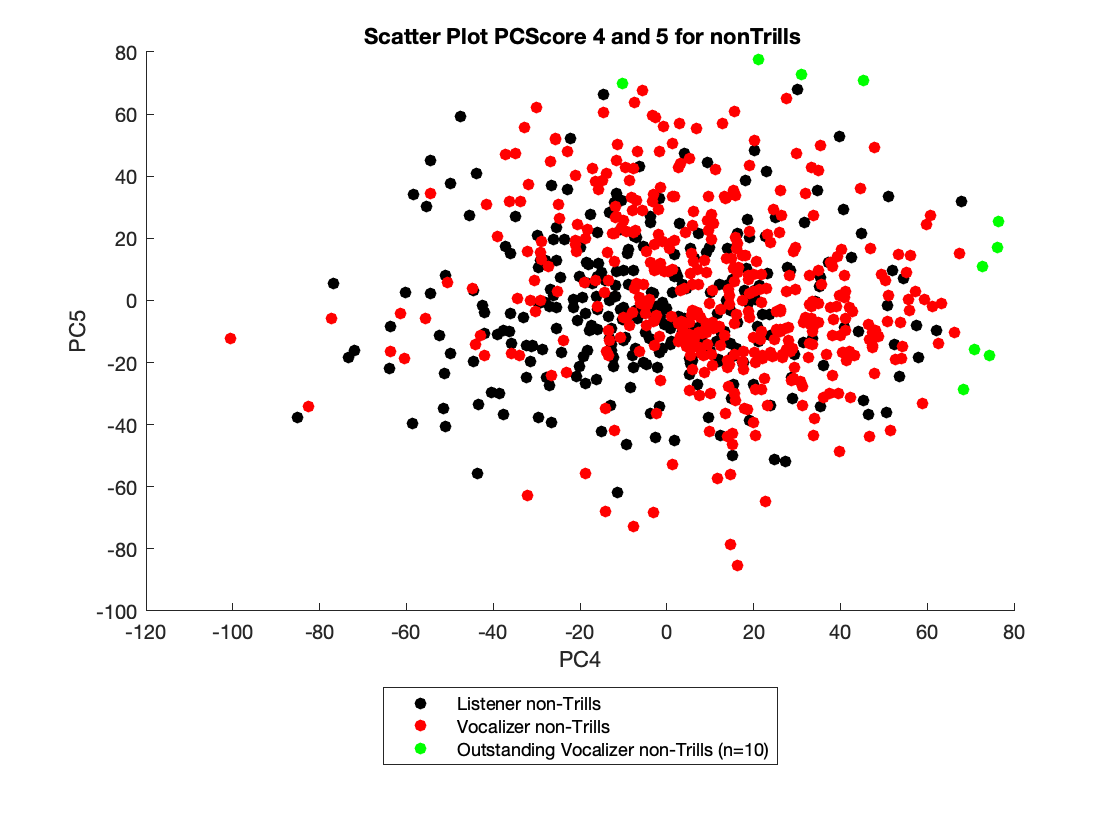

% What if we use the distribution of Listener cells as the null
% distribution and select cells that are in the 1percentile of that
% distribution?
% Outstanding cells that are in the 1percentile of the Listener
% distribution of values
PvalLim = 0.01;
ScoreOVnT = Score(OVnT_cells,PCSigNT);
ScoreOLnT = Score(OLnT_cells,PCSigNT);
OutstandingNT_pvalue = nan(size(ScoreOVnT,1),length(PCSigNT));
for rr=1:size(ScoreOVnT,1)
    for nPC = 1:length(PCSigNT)
        OutstandingNT_pvalue(rr,nPC) = 1-(sum(sign(LMCoeffVL_nonTrill(PCSigNT(nPC))).*(ScoreOVnT(rr,nPC)-ScoreOLnT(:,nPC))>0)/sum(OLnT_cells));
    end
end
% Now correct that probability for False discovery rate (True proba =
% p*(Num_comparisons-rank))
[~,Ord]=sort([OutstandingNT_pvalue(:,1); OutstandingNT_pvalue(:,2) ; OutstandingNT_pvalue(:,3)]);
Ord(Ord==length(Ord)) = length(Ord)-1;
Ord1 = Ord(1:size(ScoreOVnT,1));
Ord2 = Ord((1+size(ScoreOVnT,1)) : (2*size(ScoreOVnT,1)));
Ord3 = Ord((1+2*size(ScoreOVnT,1)) : end);
OutstandingNT_pvalueFDR = [OutstandingNT_pvalue(:,1).*(3*size(ScoreOVnT,1)-Ord1) OutstandingNT_pvalue(:,2).*(3*size(ScoreOVnT,1)-Ord2) OutstandingNT_pvalue(:,3).*(3*size(ScoreOVnT,1)-Ord3)];
OutstandingNT = OutstandingNT_pvalueFDR<PvalLim;

% Bonferroni correction is another alternative
%  OutstandingNT = (OutstandingNT_pvalue.*2*size(ScoreOVnT,1))<PvalLim;

figure()
scatter(Score(OLnT_cells,PCSigNT(1)),Score(OLnT_cells,PCSigNT(2)),'ko', 'filled')
hold on


scatter(ScoreOVnT(~sum(OutstandingNT,2),1),ScoreOVnT(~sum(OutstandingNT,2),2), 'ro', 'filled')
hold on
scatter(ScoreOVnT(logical(sum(OutstandingNT,2)),1),ScoreOVnT(logical(sum(OutstandingNT,2)),2), 'go', 'filled')
hold on


legend({'Listener non-Trills', 'Vocalizer non-Trills', sprintf('Outstanding Vocalizer non-Trills (n=%d)',sum(logical(sum(OutstandingNT,2))))}, 'Location', 'southoutside')
xlabel(sprintf('PC%d',PCSigNT(1)))
ylabel(sprintf('PC%d',PCSigNT(2)))
title(sprintf('{\b Scatter Plot PCScore %d and %d for nonTrills}',PCSigNT(1),PCSigNT(2)))
hold off

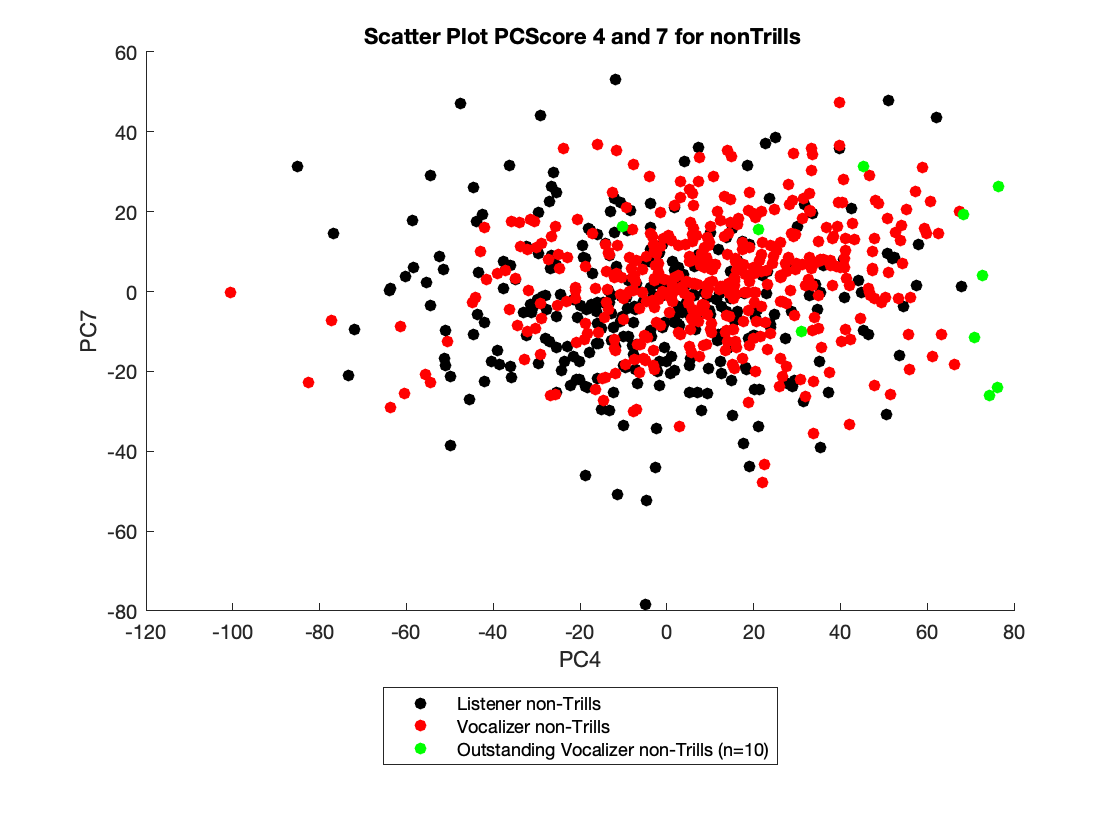


figure()
scatter(Score(OLnT_cells,PCSigNT(1)),Score(OLnT_cells,PCSigNT(3)),'ko', 'filled')
hold on


scatter(ScoreOVnT(~sum(OutstandingNT,2),1),ScoreOVnT(~sum(OutstandingNT,2),3), 'ro', 'filled')
hold on
scatter(ScoreOVnT(logical(sum(OutstandingNT,2)),1),ScoreOVnT(logical(sum(OutstandingNT,2)),3), 'go', 'filled')
hold on


legend({'Listener non-Trills', 'Vocalizer non-Trills', sprintf('Outstanding Vocalizer non-Trills (n=%d)',sum(logical(sum(OutstandingNT,2))))}, 'Location', 'southoutside')
xlabel(sprintf('PC%d',PCSigNT(1)))
ylabel(sprintf('PC%d',PCSigNT(3)))
title(sprintf('{\b Scatter Plot PCScore %d and %d for nonTrills}',PCSigNT(1),PCSigNT(3)))
hold off

% Now create the long logical vector of Outstanding vocalizer responses
OutstandingVoc = nan(size(Score,1),1);
OutstandingVoc(OVT_cells) = logical(sum(OutstandingT,2));
OutstandingVoc(OVnT_cells) = logical(sum(OutstandingNT,2));

% Cells are considered having a profile of a vocalizer if for at least one
% of their response (Trills or non-trills), the value of at least one of
% their PC score in the dimension significant in the LM comparing Listener
% and Vocalizer is significantly higher than the distribution of values for
% listener responses with FDR correction
% Cells that are further away than 2 SD in Mahalanobis distance from the 2
% Gaussian distribution of listener cells or that have at least one distance 
% higher than the max for the corresponding listener category are considered as having more
% components of vocalizer behavior. If Cells could only be evaluated
% regarding one vocalization type, they need to have a distance higher than
% the max for the corresponding listener category

% Indices of Vocalizer cells in Score that have Tr or nTr or both
CellIDV = find(OperantVocalizerCells01);
MahalDistanceV2 = nan(length(CellIDV),2);
OutstandingVoc2 = nan(length(CellIDV),2);
VCells = nan(length(CellIDV),3); % Col1: Boolean Significantly larger PC than Listener cells for at least one call type; Col2: Number of call types for which distance could be calculated; Call types for which distance was significant (2: both, 1: Trills, 0: non-trills)
for cc=1:length(CellIDV)
    CellIndices = find(CellID == CellIDV(cc));
    if length(CellIndices)==2
        MahalDistanceV2(cc,:) = MahalDistance(CellIndices);
        OutstandingVoc2(cc,:) = OutstandingVoc(CellIndices);
%         VCells(cc,1) = logical(prod(MahalDistanceV2(cc,:)>4));
        VCells(cc,1) = logical(prod(OutstandingVoc2(cc,:),2));
        VCells(cc,2) = 2;
        VCells(cc,3) = 2;
        if VCells(cc,1)==0 && OutstandingVoc2(cc,1) %(MahalDistanceV2(cc,1)>max(MahalDistanceLT)) %Large distance for Trills Significance for Trills only
            VCells(cc,1) = 1;
            VCells(cc,3) = 1;
        elseif VCells(cc,1)==0 && OutstandingVoc2(cc,2) %(MahalDistanceV2(cc,2)>max(MahalDistanceLnT)) %Large distance for non-Trills Significance for non-Trills only 
            VCells(cc,1) = 1;
            VCells(cc,3) = 0;
        end
    elseif (length(CellIndices)==1) && CellIndices(1)<=sum(~NanTr) % Distance for Trill only
        MahalDistanceV2(cc,1) = MahalDistance(CellIndices);
        OutstandingVoc2(cc,1) = OutstandingVoc(CellIndices);
%         VCells(cc,1) = MahalDistance(CellIndices)>max(MahalDistanceLT);
        VCells(cc,1) = OutstandingVoc(CellIndices);
        VCells(cc,2) = 1;
        VCells(cc,3) = 1;
    elseif (length(CellIndices)==1) && CellIndices(1)>sum(~NanTr) % Distance for Non-Trill only
        MahalDistanceV2(cc,2) = MahalDistance(CellIndices);
        OutstandingVoc2(cc,2) = OutstandingVoc(CellIndices);
%         VCells(cc,1) = MahalDistance(CellIndices)>max(MahalDistanceLnT);
        VCells(cc,1) = OutstandingVoc(CellIndices);
        VCells(cc,2) = 1;
        VCells(cc,3) = 0;
    else
        keyboard % there is an issue!
    end

end


% Cells that are either SMU or SSU
ListCellsG = ListCells(GoodCellIndices);
% select cells that are from vocalizer of either Trills or non-trills or both during operant and that have a minimum average rate over all voc of 0.1Hz
ListCellsGV = ListCellsG(logical(OperantVocalizer.*BaorTr_0ind));
% These are cells with the out of the chart values for components that
% discriminate Listener from vocalizer
ListCellsGV(logical(VCells(:,1)))

ans = 33×1 cell array
    {'/Volumes/JulieE8T/LMCResults/59834_20190604_SSM_2-208.mat'}
    {'/Volumes/JulieE8T/LMCResults/59834_20190610_SSS_1-130.mat'}
    {'/Volumes/JulieE8T/LMCResults/59834_20190612_SSS_1-81.mat' }
    {'/Volumes/JulieE8T/LMCResults/59834_20190613_SSS_1-11.mat' }
    {'/Volumes/JulieE8T/LMCResults/59834_20190613_SSS_3-127.mat'}
    {'/Volumes/JulieE8T/LMCResults/59834_20190614_SSS_1-100.mat'}
    {'/Volumes/JulieE8T/LMCResults/59834_20190618_SSM_1-73.mat' }
    {'/Volumes/JulieE8T/LMCResults/59834_20190619_SSM_1-86.mat' }
    {'/Volumes/JulieE8T/LMCResults/59834_20190620_SSM_1-87.mat' }
    {'/Volumes/JulieE8T/LMCResults/59834_20190620_SSM_4-161.mat'}
    {'/Volumes/JulieE8T/LMCResults/59834_20190621_SSM_1-84.mat' }
    {'/Volumes/JulieE8T/LMCResults/59834_20190621_SSM_1-92.mat' }
    {'/Volumes/JulieE8T/LMCResults/59834_20190623_SSM_1-108.mat'}
    {'/Volumes/JulieE8T/LMCResults/59834_20190623_SSM_1-94.mat' }
    {'/Volumes/JulieE8T/LMCResults/59834_20190624_SSM_

ListCellsVocPCAComponent = ListCellsGV(logical(VCells(:,1)));
save(fullfile(Path2AllData,'explore_populationSU_data.mat'), 'ListCellsVocPCAComponent','MahalDistanceV2','VCells', '-append')

% Get the values of MahalDistance for listener cells

% Indices of Listener cells in Score that have Tr or nTr or both
CellIDL = find(~OperantVocalizerCells01);
MahalDistanceL2 = nan(length(CellIDL),2);
LCells = nan(length(CellIDL),3);
for cc=1:length(CellIDL)
    CellIndices = find(CellID == CellIDL(cc));
    if length(CellIndices)==2
        MahalDistanceL2(cc,:) = MahalDistance(CellIndices);
        LCells(cc,1) = logical(prod(MahalDistanceL2(cc,:)>4));
        LCells(cc,2) = 2;
        LCells(cc,3) = 2;
        if LCells(cc,1)==0 && (MahalDistanceL2(cc,1)>max(MahalDistanceLT)) %Large distance for Trills
            LCells(cc,1) = 1;
            LCells(cc,3) = 1;
        elseif LCells(cc,1)==0 && (MahalDistanceL2(cc,2)>max(MahalDistanceLnT)) %Large distance for non-Trills
            LCells(cc,1) = 1;
            LCells(cc,3) = 0;
        end
    elseif (length(CellIndices)==1) && CellIndices(1)<=sum(~NanTr) % Distance for Trill
        MahalDistanceL2(cc,1) = MahalDistance(CellIndices);
        LCells(cc,1) = MahalDistance(CellIndices)>max(MahalDistanceLT);
        LCells(cc,2) = 1;
        LCells(cc,3) = 1;
    elseif (length(CellIndices)==1) && CellIndices(1)>sum(~NanTr) % Distance for Non-Trill
        MahalDistanceL2(cc,2) = MahalDistance(CellIndices);
        LCells(cc,1) = MahalDistance(CellIndices)>max(MahalDistanceLnT);
        LCells(cc,2) = 1;
        LCells(cc,3) = 0;
    else
        keyboard % there is an issue!
    end

end


% Cells that are either SMU or SSU
ListCellsG = ListCells(GoodCellIndices);
% select cells that are from Listner of either Trills or non-trills or both during operant and that have a minimum average rate over all voc of 0.1Hz
ListCellsGL = ListCellsG(logical((~OperantVocalizer).*BaorTr_0ind));
% These are cells with the out of the chart values for components that
% discriminate Listener from vocalizer
ListCellsGL(logical(LCells(:,1)))

ans = 1×1 cell array
    {'/Volumes/JulieE8T/LMCResults/65701_20190614_SSM_3-278.mat'}


ListCellsListPCAComponent = ListCellsGL(logical(LCells(:,1)));
save(fullfile(Path2AllData,'explore_populationSU_data.mat'), 'ListCellsListPCAComponent','MahalDistanceL2','LCells', '-append')

% For the vocalizer cells with motor components, get values of Information on motor and auditory coherence in Free
% session and motor coherence in operant, along with the time resolution of
% these cells. I need to find what would be the optimal size of the
% Gaussian for the next step (PCA on time varying spike rate of each vocalization for
% each cell)
% Values of MI COherence with Vocal production in Operant
HDPath = '/Volumes/JulieE8T/LMCResults/';
MC = load(fullfile(HDPath,sprintf('MotorCoherence_%s_%s.mat', 'amp', 'Operant')));
% Gather data on Info
InfoMotorOpGVCells = nan(sum(VCells(:,1)),3);% first column value of info, 2nd pRandSpikePer, 3rd pRandVoc
DelayResolutionMotorOpGVCells = nan(sum(VCells(:,1)),3); % first column delay in ms, 2nd column resolution
NanCount = [];
for cc=1:length(MC.CellsPath)
    Ind=find(contains(ListCellsGV(logical(VCells(:,1))), MC.CellsPath(cc).name));
    if ~isempty(Ind)
        InfoMotorOpGVCells(Ind,1) = MC.Info(cc);
        if isnan(MC.Info(cc))
            NanCount = [NanCount Ind];
        end
        InfoMotorOpGVCells(Ind,2) = MC.Info_pRandSpikePerm(cc);
        InfoMotorOpGVCells(Ind,3) = MC.Info_pRandVoc(cc);
        DelayResolutionMotorOpGVCells(Ind,1) = MC.CoherencyT_DelayAtzero(cc);
        DelayResolutionMotorOpGVCells(Ind,2) = 1000./(2*MC.CoherenceWeightedFreq(cc));
    end
end
fprintf(1,'Could not find any value of Motor information in Operant for %d cells', length(NanCount))

Could not find any value of Motor information in Operant for 0 cells

NanCount


NanCount =

     []




% Values of MI COherence with Vocal production in Free session
HDPath = '/Volumes/JulieE8T/LMCResults/';
MC = load(fullfile(HDPath,sprintf('MotorCoherence_%s_%s.mat', 'amp', 'Free')));
% Gather data on Info
InfoMotorFrGVCells = nan(sum(VCells(:,1)),3);% first column value of info, 2nd pRandSpikePer, 3rd pRandVoc
NanCount = [];
for cc=1:length(MC.CellsPath)
    Ind=find(contains(ListCellsGV(logical(VCells(:,1))), MC.CellsPath(cc).name));
    if ~isempty(Ind)
        InfoMotorFrGVCells(Ind,1) = MC.Info(cc);
        if isnan(MC.Info(cc))
            NanCount = [NanCount Ind];
        end
        InfoMotorFrGVCells(Ind,2) = MC.Info_pRandSpikePerm(cc);
        InfoMotorFrGVCells(Ind,3) = MC.Info_pRandVoc(cc);
    end
end
fprintf(1,'Could not find any value of Motor information in Free for %d cells', length(NanCount))

Could not find any value of Motor information in Free for 6 cells

NanCount

NanCount =     10    11    12    33    36    37



% Values of MI COherence with Vocal perception in Free session
HDPath = '/Volumes/JulieE8T/LMCResults/';
MC = load(fullfile(HDPath,sprintf('AuditoryCoherence_%s_%s.mat', 'amp', 'Free')));
% Gather data on Info
InfoAuditoryFrGVCells = nan(sum(VCells(:,1)),3);% first column value of info, 2nd pRandSpikePer, 3rd pRandVoc
NanCount = [];
for cc=1:length(MC.CellsPath)
    Ind=find(contains(ListCellsGV(logical(VCells(:,1))), MC.CellsPath(cc).name));
    if ~isempty(Ind)
        InfoAuditoryFrGVCells(Ind,1) = MC.Info(cc);
        if isnan(MC.Info(cc))
            NanCount = [NanCount Ind];
        end
        InfoAuditoryFrGVCells(Ind,2) = MC.Info_pRandSpikePerm(cc);
        InfoAuditoryFrGVCells(Ind,3) = MC.Info_pRandVoc(cc);
    end
end
fprintf(1,'Could not find any value of Auditory information in Free for %d cells', length(NanCount))

Could not find any value of Auditory information in Free for 7 cells

NanCount

NanCount =     10    11    12    33    34    36    37


% Plot the values of coherence Information
ColPC = get(groot, 'DefaultAxesColorOrder');
SigMCells = (InfoMotorOpGVCells(:,2)<0.01);
MinMahalVCells = min(MahalDistanceV2(logical(VCells(:,1)),:).^0.5, [],2);
MaxMahalVCells = max(MahalDistanceV2(logical(VCells(:,1)),:).^0.5, [],2);
figure()
scatter(MinMahalVCells(~SigMCells),InfoMotorOpGVCells(~SigMCells,1),40, 'k', 'filled')
hold on
scatter(MinMahalVCells(SigMCells),InfoMotorOpGVCells(SigMCells,1),40, 'r', 'filled')
% xlim([0 5])
hold off
legend('NS Info','Significant Info')
ylabel('Motor Info in Operant')
xlabel('Min Mahalanobis distance')

[Rho, pvalRho]=corr(MinMahalVCells,InfoMotorOpGVCells(:,1))

Rho = -0.1572

pvalRho = 0.3528

scatter(MaxMahalVCells(~SigMCells),InfoMotorOpGVCells(~SigMCells,1),30, 'k', 'filled')
hold on
scatter(MaxMahalVCells(SigMCells),InfoMotorOpGVCells(SigMCells,1),30, 'r', 'filled')
hold off
legend('NS Info','Significant Info')
ylabel('Motor Info in Operant')
xlabel('Max Mahalanobis distance')

[Rho, pvalRho]=corr(MaxMahalVCells,InfoMotorOpGVCells(:,1))

Rho = 0.2700

pvalRho = 0.1061

% Scatter of the value of information for the Vocalizer cells
SigMFrOpCells = logical((InfoMotorOpGVCells(:,2)<0.01) .* (InfoMotorFrGVCells(:,2)<0.01));
SigMFrCells = logical((InfoMotorOpGVCells(:,2)>=0.01).*(InfoMotorFrGVCells(:,2)<0.01));
SigMOpCells = logical((InfoMotorOpGVCells(:,2)<0.01).* ~(InfoMotorFrGVCells(:,2)<0.01));%Here we use ~ to consider Nan as non significant
NonSigMCells = logical((InfoMotorOpGVCells(:,2)>=0.01).* ~(InfoMotorFrGVCells(:,2)<0.01));

scatter(InfoMotorFrGVCells(SigMFrOpCells,1),InfoMotorOpGVCells(SigMFrOpCells,1),40,ColPC(4,:), 'filled')
hold on
scatter(InfoMotorFrGVCells(SigMFrCells,1),InfoMotorOpGVCells(SigMFrCells,1),40,ColPC(1,:), 'filled')
hold on
scatter(InfoMotorFrGVCells(SigMOpCells,1),InfoMotorOpGVCells(SigMOpCells,1),40,ColPC(2,:), 'filled')
hold on
scatter(InfoMotorFrGVCells(NonSigMCells,1),InfoMotorOpGVCells(NonSigMCells,1),40,'k', 'filled')
legend('Motor Op + Fr', 'Motor Fr', 'Motor Op', 'non Motor')
hold off

ylabel('Motor Info in Operant')
xlabel('Motor Info in Free')
title('Selected Vocalizer cells')

scatter(InfoMotorFrGVCells(:,1),InfoAuditoryFrGVCells(:,1),30,'k', 'filled')
ylabel('Auditory Info in Free')
xlabel('Motor Info in Free')
title('Selected Vocalizer cells')
ylim([0 3])

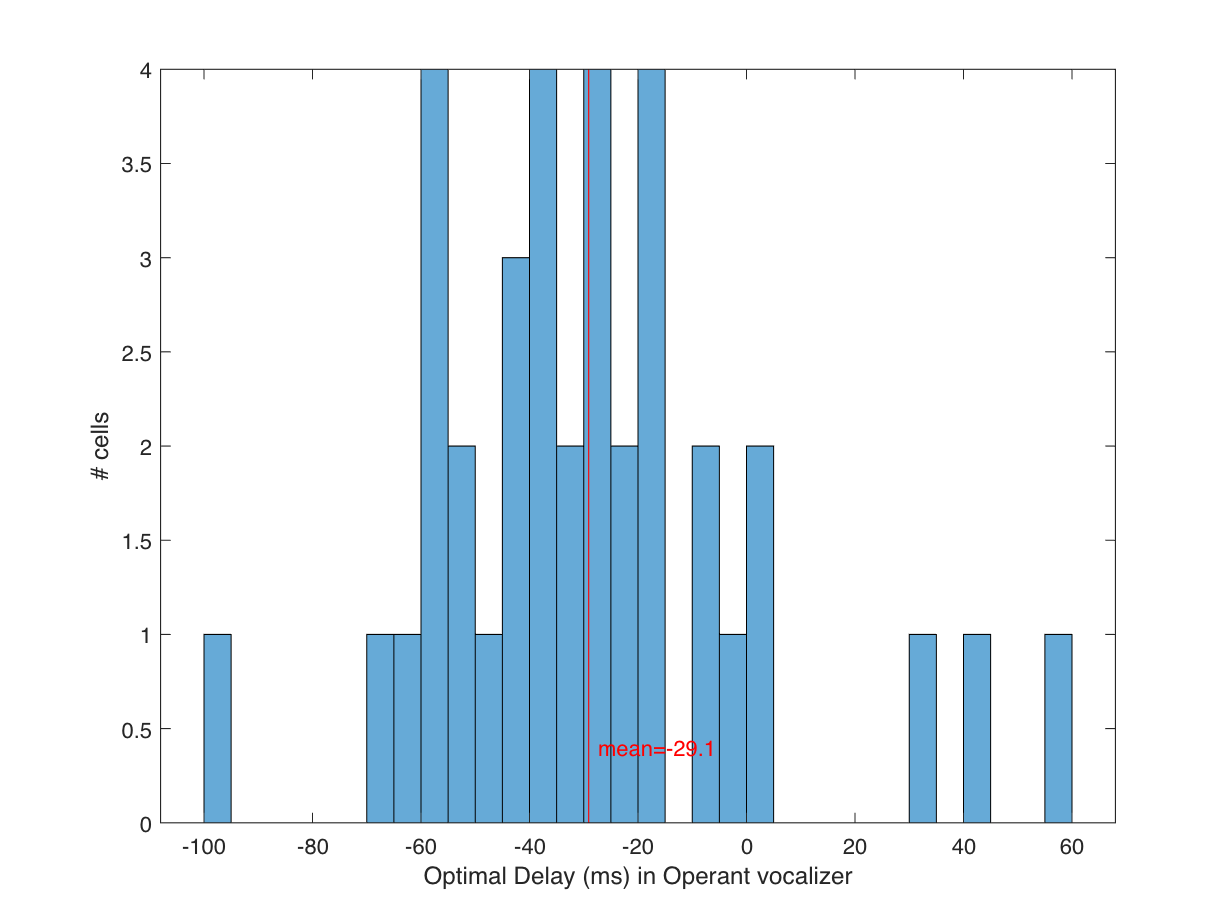

% plot the value of optimal Delay and Optimal resolution for these cells
% during Operant
histogram(DelayResolutionMotorOpGVCells(:,1), 'BinWidth',5)
hold on
vline(mean(DelayResolutionMotorOpGVCells(:,1)), 'r-',sprintf('mean=%.1f',mean(DelayResolutionMotorOpGVCells(:,1)) ))
hold off
ylabel('# cells')
xlabel('Optimal Delay (ms) in Operant vocalizer')

fprintf(1,'Minimum optimal delay = %d ms', min(DelayResolutionMotorOpGVCells(:,1)))

Minimum optimal delay = -98 ms

histogram(DelayResolutionMotorOpGVCells(:,2), 'BinWidth',1)
hold on
vline(mean(DelayResolutionMotorOpGVCells(:,2)), 'r-',sprintf('mean=%.1f',mean(DelayResolutionMotorOpGVCells(:,2)) ))
fprintf(1,'Mean optimal resolution = %.2f ms', mean(DelayResolutionMotorOpGVCells(:,2)))

Mean optimal resolution = 8.79 ms

hold on
vline(median(DelayResolutionMotorOpGVCells(:,2)), 'b-',sprintf('median=%.1f',median(DelayResolutionMotorOpGVCells(:,2)) ))
fprintf(1,'Median optimal resolution = %.2f ms', median(DelayResolutionMotorOpGVCells(:,2)))

Median optimal resolution = 7.34 ms

hold on
vline(quantile(DelayResolutionMotorOpGVCells(:,2), 0.25), 'g-',sprintf('Q25=%.1f',quantile(DelayResolutionMotorOpGVCells(:,2),0.25)))
fprintf(1,'75%% of cells have optimal resolution > %.2f ms', quantile(DelayResolutionMotorOpGVCells(:,2),0.25))

75% of cells have optimal resolution > 6.21 ms

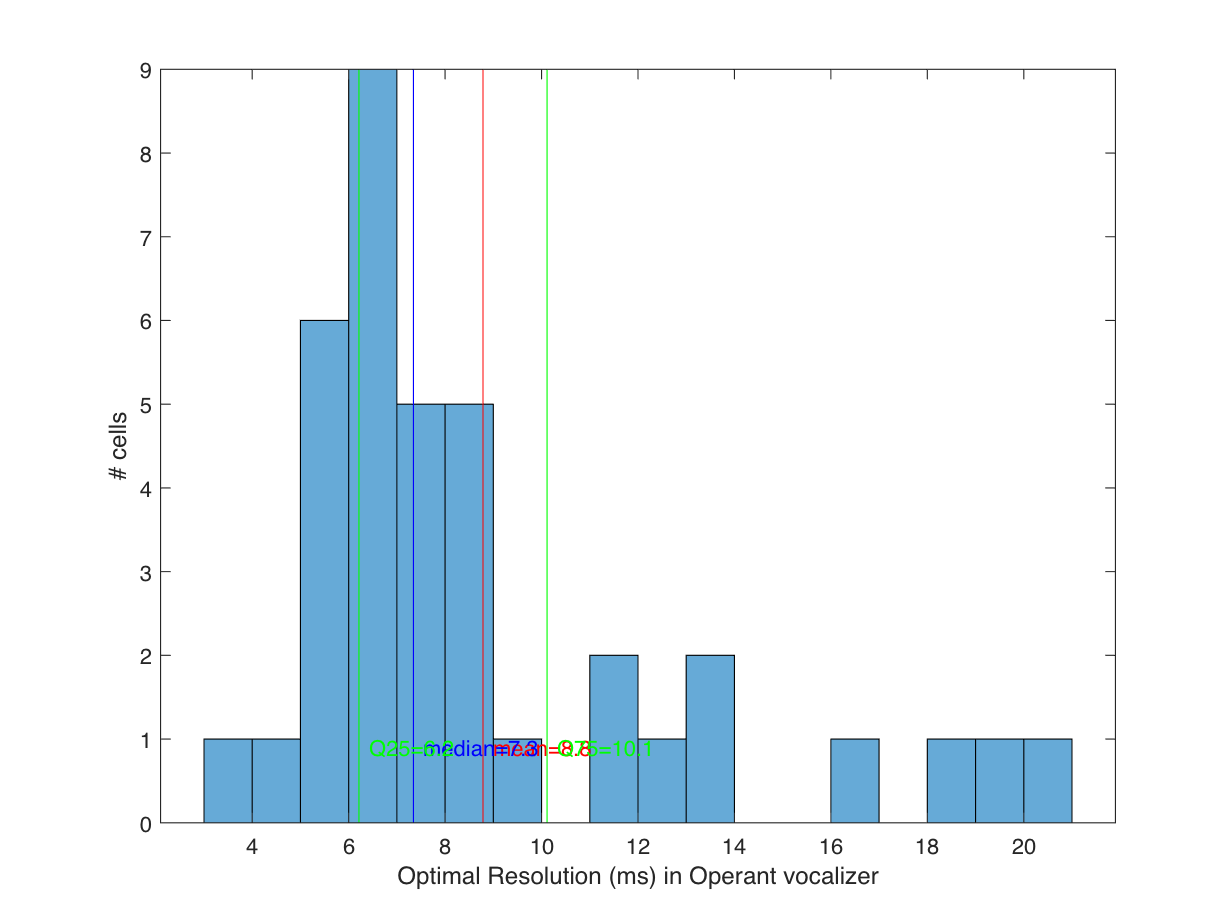

hold on
vline(quantile(DelayResolutionMotorOpGVCells(:,2), 0.75), 'g-',sprintf('Q75=%.1f',quantile(DelayResolutionMotorOpGVCells(:,2),0.75)))
ylabel('# cells')
xlabel('Optimal Resolution (ms) in Operant vocalizer')
hold off

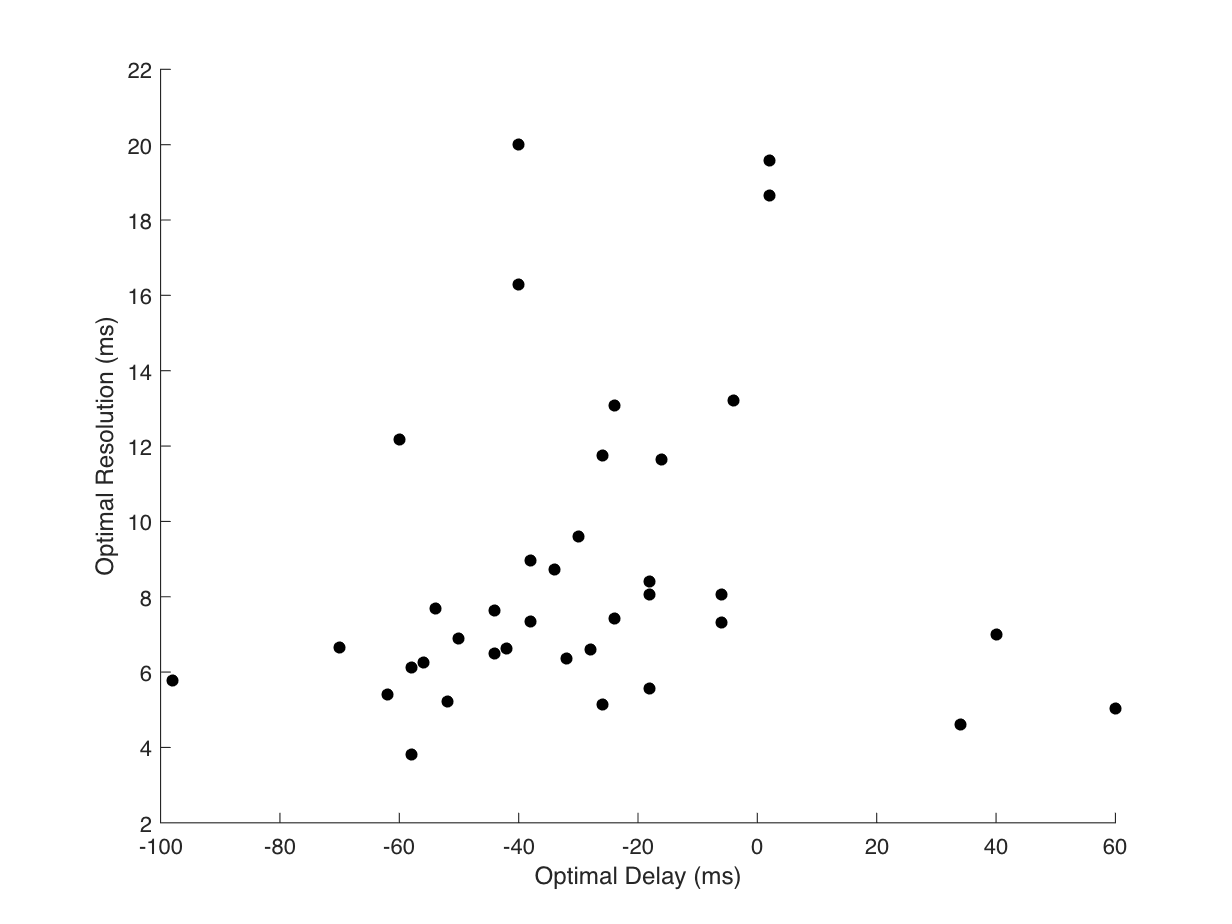

scatter(DelayResolutionMotorOpGVCells(:,1),DelayResolutionMotorOpGVCells(:,2), 30, 'k', 'filled')
xlabel('Optimal Delay (ms)')
ylabel('Optimal Resolution (ms)')

Let's try a PCA on the pdf

% run PCA on the pdf of the operant KDE
[PC,Score,~, ~, VarExpl,~] = pca(KDE_onset_Mat_Op_pdf_noTrim);

% Plot the cumulative explained variance as a function of # PCs
plot(cumsum(VarExpl), 'LineWidth',2);xlabel('#PC');ylabel('Proportion variance explained by PCA)'); xlim([0 15])
% Plot the first PC shapes
plot(PC(:,1), 'LineWidth',2);hold on;plot(PC(:,2), 'LineWidth',2);plot(PC(:,3), 'LineWidth',2);plot(PC(:,4), 'LineWidth',2);plot(PC(:,5), 'LineWidth',2);plot(PC(:,6), 'LineWidth',2);plot(PC(:,7), 'LineWidth',2);plot(PC(:,8), 'LineWidth',2);plot(PC(:,9), 'LineWidth',2);plot(PC(:,10), 'LineWidth',2);legend('PC1', 'PC2','PC3', 'PC4', 'PC5', 'PC6','PC7','PC8','PC9','PC10', 'Location', 'EastOutside'); ylabel('PCA coefficients');xlabel('Time (s)');xticks([1 -(Tstart+Trim)]);xticklabels([(Tstart+Trim)/10^3 0])
hold off

% Look for each PC the PCA Coefficient weighted amount of info explained on average
ColPC = get(groot, 'DefaultAxesColorOrder');
ScatterMarkerSz=30;
MeanMarkerSize=14;
hold off
NC = size(KDE_onset_Mat_Op_pdf_noTrim,1);
hold on
n=1;
swarmchart(n*ones(NC,1),InfoOp(:,1).*Score(:,n),ScatterMarkerSz,ColPC(n,:),'o','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5)
hold on
errorbar(n,nanmean(InfoOp(:,1).*Score(:,n)),nanstd(InfoOp(:,1).*Score(:,n))/sum(~isnan(InfoOp(:,1).*Score(:,n)))^0.5, 'dk','MarkerSize',MeanMarkerSize,'MarkerFaceColor',ColPC(n,:))
hold on
n=2;
swarmchart(n*ones(NC,1),InfoOp(:,1).*Score(:,n),ScatterMarkerSz,ColPC(n,:),'o','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5)
hold on
errorbar(n,nanmean(InfoOp(:,1).*Score(:,n)),nanstd(InfoOp(:,1).*Score(:,n))/sum(~isnan(InfoOp(:,1).*Score(:,n)))^0.5, 'dk','MarkerSize',MeanMarkerSize,'MarkerFaceColor',ColPC(n,:))
hold on
n=3;
swarmchart(n*ones(NC,1),InfoOp(:,1).*Score(:,n),ScatterMarkerSz,ColPC(n,:),'o','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5)
hold on
errorbar(n,nanmean(InfoOp(:,1).*Score(:,n)),nanstd(InfoOp(:,1).*Score(:,n))/sum(~isnan(InfoOp(:,1).*Score(:,n)))^0.5, 'dk','MarkerSize',MeanMarkerSize,'MarkerFaceColor',ColPC(n,:))
n=4;
hold on
swarmchart(n*ones(NC,1),InfoOp(:,1).*Score(:,n),ScatterMarkerSz,ColPC(n,:),'o','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5)
hold on
errorbar(n,nanmean(InfoOp(:,1).*Score(:,n)),nanstd(InfoOp(:,1).*Score(:,n))/sum(~isnan(InfoOp(:,1).*Score(:,n)))^0.5, 'dk','MarkerSize',MeanMarkerSize,'MarkerFaceColor',ColPC(n,:))
n=5;
hold on
swarmchart(n*ones(NC,1),InfoOp(:,1).*Score(:,n),ScatterMarkerSz,ColPC(n,:),'o','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5)
hold on
errorbar(n,nanmean(InfoOp(:,1).*Score(:,n)),nanstd(InfoOp(:,1).*Score(:,n))/sum(~isnan(InfoOp(:,1).*Score(:,n)))^0.5, 'dk','MarkerSize',MeanMarkerSize,'MarkerFaceColor',ColPC(n,:))
n=6;
hold on
swarmchart(n*ones(NC,1),InfoOp(:,1).*Score(:,n),ScatterMarkerSz,ColPC(n,:),'o','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5)
hold on
errorbar(n,nanmean(InfoOp(:,1).*Score(:,n)),nanstd(InfoOp(:,1).*Score(:,n))/sum(~isnan(InfoOp(:,1).*Score(:,n)))^0.5, 'dk','MarkerSize',MeanMarkerSize,'MarkerFaceColor',ColPC(n,:))
n=7;
hold on
swarmchart(n*ones(NC,1),InfoOp(:,1).*Score(:,n),ScatterMarkerSz,ColPC(n,:),'o','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5)
hold on
errorbar(n,nanmean(InfoOp(:,1).*Score(:,n)),nanstd(InfoOp(:,1).*Score(:,n))/sum(~isnan(InfoOp(:,1).*Score(:,n)))^0.5, 'dk','MarkerSize',MeanMarkerSize,'MarkerFaceColor',ColPC(n,:))
hold off
xlabel('PC #')
ylabel('Info on Motor coherence')

% what is the average score of cells that have the highest info values
[~,IndInfo] = sort(InfoOp(:,1), 'descend');
Nan_0 = ~isnan(InfoOp(IndInfo,1));
imagesc(Score(IndInfo(Nan_0),(1:10)))
colormap('copper')
ylabel('Cells classified by decreasing value of MI coherence voc Production')
xlabel('PC#')
title('PCA Score')

Plot the average spike rate for each cluster

CLim01 = 1;
if CLim01
    CLim = [-3 3];
end
% cluster 1
Clust=1;
IndSSU = intersect(GoodCellIndices(BaTr_ind(T==Clust)), find(SSSU));
IndSMU = intersect(GoodCellIndices(BaTr_ind(T==Clust)), find(SSMU));
fprintf(1,'**** Cluster %d *****\n%d units, %d single units, %d multi-units\n', Clust, sum(T==Clust),length(IndSSU),length(IndSMU))
for ii=1:length(IndSSU)
    fprintf('Single Unit: %s\n',ListSSU(IndSSU(ii)).name)
end
for ii=1:length(IndSMU)
    fprintf('Multi Unit: %s\n',ListSSU(IndSMU(ii)).name)
end
fprintf(1,' Plot ZS data Cluster %d \n', Clust)
imagesc(KDE_onset_Mat_BaTr_ZS(T==Clust,:))
if CLim01
    caxis(CLim)
else
    CLim = caxis;
end
colorbar()
colormap('cool')
hold on
% delimiting Barks from Trills
line(TBa*ones(2,1), [-1 sum(T==Clust)+1],'Color', 'w', 'LineWidth',2)
hold on
% Barks onset
line([-Tstart -Tstart], [0 sum(T==Clust)],'Color','y','LineStyle','--', 'LineWidth',2)
hold on
% Trills onset
line((-Tstart + TBa)*ones(2,1), [0 sum(T==Clust)],'Color','y','LineStyle','--', 'LineWidth',2)
ylabel('Units')
xlabel('Time (s)')
xticks([1 -Tstart TBa TBa-Tstart])
xticklabels([Tstart/10^3 0 Tstart/10^3 0])
title('Barks               Trills')
hold off

plot(mean(KDE_onset_Mat_BaTr_ZS(T==Clust,:)), 'k-', 'LineWidth',2)
xlim([0 size(KDE_onset_Mat_BaTr_ZS,2)])
xlabel('Time (s)')
xticks([1 -Tstart TBa TBa-Tstart])
xticklabels([Tstart/10^3 0 Tstart/10^3 0])
hold on
% Barks onset
line([-Tstart -Tstart], CLim,'Color','r','LineStyle','--', 'LineWidth',2)
hold on
% Trills onset
line((-Tstart + TBa)*ones(2,1), CLim,'Color','r','LineStyle','--', 'LineWidth',2)
ylabel('z-scored rate')
title('Barks                       Trills')
hold off


% cluster 2 good example: 0612_SSS_1-81
Clust=2;
IndSSU = intersect(GoodCellIndices(BaTr_ind(T==Clust)), find(SSSU));
IndSMU = intersect(GoodCellIndices(BaTr_ind(T==Clust)), find(SSMU));
fprintf(1,'**** Cluster %d *****\n%d units, %d single units, %d multi-units\n', Clust, sum(T==Clust),length(IndSSU),length(IndSMU))
for ii=1:length(IndSSU)
    fprintf('Single Unit: %s\n',ListSSU(IndSSU(ii)).name)
end
for ii=1:length(IndSMU)
    fprintf('Multi Unit: %s\n',ListSSU(IndSMU(ii)).name)
end
fprintf(1,' Plot ZS data Cluster %d \n', Clust)
imagesc(KDE_onset_Mat_BaTr_ZS(T==Clust,:))
if CLim01
    caxis(CLim)
else
    CLim = caxis;
end
colorbar()
colormap('cool')
hold on
% delimiting Barks from Trills
line(TBa*ones(2,1), [-1 sum(T==Clust)+1],'Color', 'w', 'LineWidth',2)
hold on
% Barks onset
line([-Tstart -Tstart], [0 sum(T==Clust)],'Color','y','LineStyle','--', 'LineWidth',2)
hold on
% Trills onset
line((-Tstart + TBa)*ones(2,1), [0 sum(T==Clust)],'Color','y','LineStyle','--', 'LineWidth',2)
ylabel('Units')
xlabel('Time (s)')
xticks([1 -Tstart TBa TBa-Tstart])
xticklabels([Tstart/10^3 0 Tstart/10^3 0])
title('Barks               Trills')
hold off

plot(mean(KDE_onset_Mat_BaTr_ZS(T==Clust,:)), 'k-', 'LineWidth',2)
xlim([0 size(KDE_onset_Mat_BaTr_ZS,2)])
xlabel('Time (s)')
xticks([1 -Tstart TBa TBa-Tstart])
xticklabels([Tstart/10^3 0 Tstart/10^3 0])
hold on
% Barks onset
line([-Tstart -Tstart], CLim,'Color','r','LineStyle','--', 'LineWidth',2)
hold on
% Trills onset
line((-Tstart + TBa)*ones(2,1), CLim,'Color','r','LineStyle','--', 'LineWidth',2)
ylabel('z-scored rate')
title('Barks                       Trills')
hold off

% cluster 3 good example 0620_SSS_3_131
Clust=3;
IndSSU = intersect(GoodCellIndices(BaTr_ind(T==Clust)), find(SSSU));
IndSMU = intersect(GoodCellIndices(BaTr_ind(T==Clust)), find(SSMU));
fprintf(1,'**** Cluster %d *****\n%d units, %d single units, %d multi-units\n', Clust, sum(T==Clust),length(IndSSU),length(IndSMU))
for ii=1:length(IndSSU)
    fprintf('Single Unit: %s\n',ListSSU(IndSSU(ii)).name)
end
for ii=1:length(IndSMU)
    fprintf('Multi Unit: %s\n',ListSSU(IndSMU(ii)).name)
end
fprintf(1,' Plot ZS data Cluster %d \n', Clust)
imagesc(KDE_onset_Mat_BaTr_ZS(T==Clust,:))
if CLim01
    caxis(CLim)
else
    CLim = caxis;
end
colorbar()
colormap('cool')
hold on
% delimiting Barks from Trills
line(TBa*ones(2,1), [-1 sum(T==Clust)+1],'Color', 'w', 'LineWidth',2)
hold on
% Barks onset
line([-Tstart -Tstart], [0 sum(T==Clust)],'Color','y','LineStyle','--', 'LineWidth',2)
hold on
% Trills onset
line((-Tstart + TBa)*ones(2,1), [0 sum(T==Clust)],'Color','y','LineStyle','--', 'LineWidth',2)
ylabel('Units')
xlabel('Time (s)')
xticks([1 -Tstart TBa TBa-Tstart])
xticklabels([Tstart/10^3 0 Tstart/10^3 0])
title('Barks               Trills')
hold off

plot(mean(KDE_onset_Mat_BaTr_ZS(T==Clust,:)), 'k-', 'LineWidth',2)
xlim([0 size(KDE_onset_Mat_BaTr_ZS,2)])
xlabel('Time (s)')
xticks([1 -Tstart TBa TBa-Tstart])
xticklabels([Tstart/10^3 0 Tstart/10^3 0])
hold on
% Barks onset
line([-Tstart -Tstart], CLim,'Color','r','LineStyle','--', 'LineWidth',2)
hold on
% Trills onset
line((-Tstart + TBa)*ones(2,1), CLim,'Color','r','LineStyle','--', 'LineWidth',2)
ylabel('z-scored rate')
title('Barks                       Trills')
hold off

% cluster 4
Clust=4;
IndSSU = intersect(GoodCellIndices(BaTr_ind(T==Clust)), find(SSSU));
IndSMU = intersect(GoodCellIndices(BaTr_ind(T==Clust)), find(SSMU));
fprintf(1,'**** Cluster %d *****\n%d units, %d single units, %d multi-units\n', Clust, sum(T==Clust),length(IndSSU),length(IndSMU))
for ii=1:length(IndSSU)
    fprintf('Single Unit: %s\n',ListSSU(IndSSU(ii)).name)
end
for ii=1:length(IndSMU)
    fprintf('Multi Unit: %s\n',ListSSU(IndSMU(ii)).name)
end
fprintf(1,' Plot ZS data Cluster %d \n', Clust)
imagesc(KDE_onset_Mat_BaTr_ZS(T==Clust,:))
if CLim01
    caxis(CLim)
else
    CLim = caxis;
end
colorbar()
colormap('cool')
hold on
% delimiting Barks from Trills
line(TBa*ones(2,1), [-1 sum(T==Clust)+1],'Color', 'w', 'LineWidth',2)
hold on
% Barks onset
line([-Tstart -Tstart], [0 sum(T==Clust)],'Color','y','LineStyle','--', 'LineWidth',2)
hold on
% Trills onset
line((-Tstart + TBa)*ones(2,1), [0 sum(T==Clust)],'Color','y','LineStyle','--', 'LineWidth',2)
ylabel('Units')
xlabel('Time (s)')
xticks([1 -Tstart TBa TBa-Tstart])
xticklabels([Tstart/10^3 0 Tstart/10^3 0])
title('Barks               Trills')
hold off

plot(mean(KDE_onset_Mat_BaTr_ZS(T==Clust,:)), 'k-', 'LineWidth',2)
xlim([0 size(KDE_onset_Mat_BaTr_ZS,2)])
xlabel('Time (s)')
xticks([1 -Tstart TBa TBa-Tstart])
xticklabels([Tstart/10^3 0 Tstart/10^3 0])
hold on
% Barks onset
line([-Tstart -Tstart], CLim,'Color','r','LineStyle','--', 'LineWidth',2)
hold on
% Trills onset
line((-Tstart + TBa)*ones(2,1), CLim,'Color','r','LineStyle','--', 'LineWidth',2)
ylabel('z-scored rate')
title('Barks                       Trills')
hold off

% cluster 5
Clust=5;
IndSSU = intersect(GoodCellIndices(BaTr_ind(T==Clust)), find(SSSU));
IndSMU = intersect(GoodCellIndices(BaTr_ind(T==Clust)), find(SSMU));
fprintf(1,'**** Cluster %d *****\n%d units, %d single units, %d multi-units\n', Clust, sum(T==Clust),length(IndSSU),length(IndSMU))
for ii=1:length(IndSSU)
    fprintf('Single Unit: %s\n',ListSSU(IndSSU(ii)).name)
end
for ii=1:length(IndSMU)
    fprintf('Multi Unit: %s\n',ListSSU(IndSMU(ii)).name)
end
fprintf(1,' Plot ZS data Cluster %d \n', Clust)
imagesc(KDE_onset_Mat_BaTr_ZS(T==Clust,:))
if CLim01
    caxis(CLim)
else
    CLim = caxis;
end
colorbar()
colormap('cool')
hold on
% delimiting Barks from Trills
line(TBa*ones(2,1), [-1 sum(T==Clust)+1],'Color', 'w', 'LineWidth',2)
hold on
% Barks onset
line([-Tstart -Tstart], [0 sum(T==Clust)],'Color','y','LineStyle','--', 'LineWidth',2)
hold on
% Trills onset
line((-Tstart + TBa)*ones(2,1), [0 sum(T==Clust)],'Color','y','LineStyle','--', 'LineWidth',2)
ylabel('Units')
xlabel('Time (s)')
xticks([1 -Tstart TBa TBa-Tstart])
xticklabels([Tstart/10^3 0 Tstart/10^3 0])
title('Barks               Trills')
hold off

plot(mean(KDE_onset_Mat_BaTr_ZS(T==Clust,:)), 'k-', 'LineWidth',2)
xlim([0 size(KDE_onset_Mat_BaTr_ZS,2)])
xlabel('Time (s)')
xticks([1 -Tstart TBa TBa-Tstart])
xticklabels([Tstart/10^3 0 Tstart/10^3 0])
hold on
% Barks onset
line([-Tstart -Tstart], CLim,'Color','r','LineStyle','--', 'LineWidth',2)
hold on
% Trills onset
line((-Tstart + TBa)*ones(2,1), CLim,'Color','r','LineStyle','--', 'LineWidth',2)
ylabel('z-scored rate')
title('Barks                       Trills')
hold off

save('explore_populationSU_data_5000.mat')

## Hierarchical clustering on KDE onset of all cells for Ba and Tr starting at -200ms and ending at 500ms

% gather the data
Tstart = -200;
Tstop = 500;
GoodCellIndices = sort([find(SSSU); find(SSMU)]);
GC = length(GoodCellIndices);
KDE_onset = cell(GC,3);
T_onset = cell(GC,2);
Tmax = nan(GC,2);
MeanKDEBaTrOp = nan(GC,1);
StdKDEBaTrOp = nan(GC,1);
MeanKDEAllVocOp = nan(GC,1);
StdKDEAllVocOp = nan(GC,1);
for ss=1:GC
    fprintf(1,'File %d/%d\n',ss,GC)
    [~,FileName] = fileparts(ListSSU(GoodCellIndices(ss)).name);
    Data=load(fullfile(ListSSU(GoodCellIndices(ss)).folder,ListSSU(GoodCellIndices(ss)).name));
    if isfield(Data,'KDE_onset') && isfield(Data.KDE_onset, 'SelfBaOp')
        Tmax(ss,1) = max(Data.KDE_onset.SelfBaOp(2,:));
        KDE_onset{ss,1} = Data.KDE_onset.SelfBaOp(1,find(Data.KDE_onset.SelfBaOp(2,:)==Tstart):find(Data.KDE_onset.SelfBaOp(2,:)==Tstop));
    end
    if isfield(Data,'KDE_onset') && isfield(Data.KDE_onset, 'SelfTrOp')
        Tmax(ss,2) = max(Data.KDE_onset.SelfTrOp(2,:));
        KDE_onset{ss,2} = Data.KDE_onset.SelfTrOp(1,find(Data.KDE_onset.SelfTrOp(2,:)==Tstart):find(Data.KDE_onset.SelfTrOp(2,:)==Tstop));
    end
    if isfield(Data,'KDE_onset') && isfield(Data.KDE_onset, 'SelfVocOp')
        KDE_onset{ss,3} = Data.KDE_onset.SelfVocOp(1,find(Data.KDE_onset.SelfVocOp(2,:)==Tstart):find(Data.KDE_onset.SelfVocOp(2,:)==Tstop));
        MeanKDEAllVocOp(ss) = nanmean(KDE_onset{ss,3}); 
        StdKDEAllVocOp(ss) = nanstd(KDE_onset{ss,3}); 
    end
    MeanKDEBaTrOp(ss) = nanmean([KDE_onset{ss,1} KDE_onset{ss,2}]); 
    StdKDEBaTrOp(ss) = nanstd([KDE_onset{ss,1} KDE_onset{ss,2}]); 
end
save('explore_populationSU_data_200.mat')

% Explore the average spike rates and get rid of non active cells?
histogram(MeanKDEAllVocOp,'BinWidth',0.1)
xlabel('Mean KDE All Voc (Hz)')
ylabel('# units')
histogram(MeanKDEAllVocOp,'BinWidth',0.1)
xlabel('Mean KDE All Voc (Hz)')
ylabel('# units')
xlim([0 5])
ActiveCells = find(MeanKDEAllVocOp>0.1);
fprintf(1,'Number of active cells: %d',length(ActiveCells))

% Trim the data of active cells in time and create a matrix of all the z-scored KDE

BaTr_0ind = ~isnan(Tmax(:,1)) .* ~isnan(Tmax(:,2)).* ~isnan(MeanKDEBaTrOp).*MeanKDEAllVocOp>0.1;
BaTr_Ind = find(BaTr_0ind);
fprintf('The clustering algorithm can be performed on the data of %d/%d\n',sum(BaTr_0ind),length(ActiveCells))
TBa = length(Tstart:Tstop);
TTr = length(Tstart:Tstop);
KDE_onset_Mat_BaTr_ZS_noTrim = nan(sum(BaTr_0ind),TBa + TTr);
for ss=1:sum(BaTr_0ind)
    fprintf(1,'File %d/%d\n',ss,sum(BaTr_0ind))
    KDE_onset_Mat_BaTr_ZS_noTrim(ss,:) = ([KDE_onset{BaTr_Ind(ss),1}(1:TBa) KDE_onset{BaTr_Ind(ss),2}(1:TTr)]-MeanKDEBaTrOp(BaTr_Ind(ss)))/StdKDEBaTrOp(BaTr_Ind(ss));
end


% Explore the number of time points with signficant (zscore>2) difference
% in spike rate
SignifTP = sum(abs(KDE_onset_Mat_BaTr_ZS_noTrim)>1.6,2);
histogram(SignifTP, 'BinWidth',10)
xlabel('Number of significant time points (ms)')
ylabel('# units')
histogram(SignifTP(logical(SignifTP)), 'BinWidth',20)
xlabel('Number of significant time points (ms)')
ylabel('# units')
fprintf(1,'%d/%d (%.2f %%) units are significant\n',sum(logical(SignifTP)),length(SignifTP),100*sum(logical(SignifTP))/length(SignifTP))
fprintf(1, 'Duration of significance: %.1f +/- %.1f ms\n',mean(SignifTP(logical(SignifTP))), std(SignifTP(logical(SignifTP)))/(sum(logical(SignifTP)))^0.5)
fprintf(1,'Minimum value %.1f ms\n',min(SignifTP(logical(SignifTP))))
fprintf(1, 'Maximum value %.1f ms\n',max(SignifTP(logical(SignifTP))))


ListCellsGC = ListSSU(GoodCellIndices);
ListCellsGCOpFr = ListCellsGC(BaTr_Ind);
NonSignif=find(~logical(SignifTP));
fprintf(1,'***** Checking non-significant cells ******')
figure;
for ii=1:length(NonSignif)
    clc
    set(gcf, 'Visible','on')
    fprintf(1,ListCellsGCOpFr(NonSignif(ii)).name)
    plot(KDE_onset_Mat_BaTr_ZS(NonSignif(ii),:))
    title(sprintf('%s',ListCellsGCOpFr(NonSignif(ii)).name))
    pause()
end

% Restrict the dataset to significant cells
KDE_onset_Mat_BaTr_ZS = KDE_onset_Mat_BaTr_ZS_noTrim(logical(SignifTP),:);
BaTr_ind = BaTr_Ind(logical(SignifTP));

% Clustering based on zscored KDE
Z = linkage(KDE_onset_Mat_BaTr_ZS,'ward','euclidean')
D1 = dendrogram(Z,0, 'ColorThreshold','Default');
set(D1,'LineWidth',2)
T = cluster(Z,'maxclust',6);
cutoff = median([Z(end-5,3) Z(end-4,3)]);
D2=dendrogram(Z,0,'ColorThreshold',cutoff,'Labels',num2str(T));
set(D2, 'LineWidth',2)
D3=dendrogram(Z,30,'ColorThreshold',cutoff,'Labels',num2str(T));
set(D3, 'LineWidth',2)

Plot the average spike rate for each cluster

CLim01 = 1;
if CLim01
    CLim = [-3 3];
end
% cluster 1
Clust=1;
IndSSU = intersect(GoodCellIndices(BaTr_ind(T==Clust)), find(SSSU));
IndSMU = intersect(GoodCellIndices(BaTr_ind(T==Clust)), find(SSMU));
fprintf(1,'**** Cluster %d *****\n%d units, %d single units, %d multi-units\n', Clust, sum(T==Clust),length(IndSSU),length(IndSMU))
for ii=1:length(IndSSU)
    fprintf('Single Unit: %s\n',ListSSU(IndSSU(ii)).name)
end
for ii=1:length(IndSMU)
    fprintf('Multi Unit: %s\n',ListSSU(IndSMU(ii)).name)
end
fprintf(1,' Plot ZS data Cluster %d \n', Clust)
imagesc(KDE_onset_Mat_BaTr_ZS(T==Clust,:))
if CLim01
    caxis(CLim)
else
    CLim = caxis;
end
colorbar()
colormap('cool')
hold on
% delimiting Barks from Trills
line(TBa*ones(2,1), [-1 sum(T==Clust)+1],'Color', 'w', 'LineWidth',2)
hold on
% Barks onset
line([-Tstart -Tstart], [0 sum(T==Clust)],'Color','y','LineStyle','--', 'LineWidth',2)
hold on
% Trills onset
line((-Tstart + TBa)*ones(2,1), [0 sum(T==Clust)],'Color','y','LineStyle','--', 'LineWidth',2)
ylabel('Units')
xlabel('Time (s)')
xticks([1 -Tstart TBa TBa-Tstart])
xticklabels([Tstart/10^3 0 Tstart/10^3 0])
title('Barks               Trills')
hold off

plot(mean(KDE_onset_Mat_BaTr_ZS(T==Clust,:)), 'k-', 'LineWidth',2)
xlim([0 size(KDE_onset_Mat_BaTr_ZS,2)])
xlabel('Time (s)')
xticks([1 -Tstart TBa TBa-Tstart])
xticklabels([Tstart/10^3 0 Tstart/10^3 0])
hold on
% Barks onset
line([-Tstart -Tstart], CLim,'Color','r','LineStyle','--', 'LineWidth',2)
hold on
% Trills onset
line((-Tstart + TBa)*ones(2,1), CLim,'Color','r','LineStyle','--', 'LineWidth',2)
ylabel('z-scored rate')
title('Barks                       Trills')
hold off


% cluster 2 good example: 0612_SSS_1-81
Clust=2;
IndSSU = intersect(GoodCellIndices(BaTr_ind(T==Clust)), find(SSSU));
IndSMU = intersect(GoodCellIndices(BaTr_ind(T==Clust)), find(SSMU));
fprintf(1,'**** Cluster %d *****\n%d units, %d single units, %d multi-units\n', Clust, sum(T==Clust),length(IndSSU),length(IndSMU))
for ii=1:length(IndSSU)
    fprintf('Single Unit: %s\n',ListSSU(IndSSU(ii)).name)
end
for ii=1:length(IndSMU)
    fprintf('Multi Unit: %s\n',ListSSU(IndSMU(ii)).name)
end
fprintf(1,' Plot ZS data Cluster %d \n', Clust)
imagesc(KDE_onset_Mat_BaTr_ZS(T==Clust,:))
if CLim01
    caxis(CLim)
else
    CLim = caxis;
end
colorbar()
colormap('cool')
hold on
% delimiting Barks from Trills
line(TBa*ones(2,1), [-1 sum(T==Clust)+1],'Color', 'w', 'LineWidth',2)
hold on
% Barks onset
line([-Tstart -Tstart], [0 sum(T==Clust)],'Color','y','LineStyle','--', 'LineWidth',2)
hold on
% Trills onset
line((-Tstart + TBa)*ones(2,1), [0 sum(T==Clust)],'Color','y','LineStyle','--', 'LineWidth',2)
ylabel('Units')
xlabel('Time (s)')
xticks([1 -Tstart TBa TBa-Tstart])
xticklabels([Tstart/10^3 0 Tstart/10^3 0])
title('Barks               Trills')
hold off

plot(mean(KDE_onset_Mat_BaTr_ZS(T==Clust,:)), 'k-', 'LineWidth',2)
xlim([0 size(KDE_onset_Mat_BaTr_ZS,2)])
xlabel('Time (s)')
xticks([1 -Tstart TBa TBa-Tstart])
xticklabels([Tstart/10^3 0 Tstart/10^3 0])
hold on
% Barks onset
line([-Tstart -Tstart], CLim,'Color','r','LineStyle','--', 'LineWidth',2)
hold on
% Trills onset
line((-Tstart + TBa)*ones(2,1), CLim,'Color','r','LineStyle','--', 'LineWidth',2)
ylabel('z-scored rate')
title('Barks                       Trills')
hold off

% cluster 3 good example 0620_SSS_3_131
Clust=3;
IndSSU = intersect(GoodCellIndices(BaTr_ind(T==Clust)), find(SSSU));
IndSMU = intersect(GoodCellIndices(BaTr_ind(T==Clust)), find(SSMU));
fprintf(1,'**** Cluster %d *****\n%d units, %d single units, %d multi-units\n', Clust, sum(T==Clust),length(IndSSU),length(IndSMU))
for ii=1:length(IndSSU)
    fprintf('Single Unit: %s\n',ListSSU(IndSSU(ii)).name)
end
for ii=1:length(IndSMU)
    fprintf('Multi Unit: %s\n',ListSSU(IndSMU(ii)).name)
end
fprintf(1,' Plot ZS data Cluster %d \n', Clust)
imagesc(KDE_onset_Mat_BaTr_ZS(T==Clust,:))
if CLim01
    caxis(CLim)
else
    CLim = caxis;
end
colorbar()
colormap('cool')
hold on
% delimiting Barks from Trills
line(TBa*ones(2,1), [-1 sum(T==Clust)+1],'Color', 'w', 'LineWidth',2)
hold on
% Barks onset
line([-Tstart -Tstart], [0 sum(T==Clust)],'Color','y','LineStyle','--', 'LineWidth',2)
hold on
% Trills onset
line((-Tstart + TBa)*ones(2,1), [0 sum(T==Clust)],'Color','y','LineStyle','--', 'LineWidth',2)
ylabel('Units')
xlabel('Time (s)')
xticks([1 -Tstart TBa TBa-Tstart])
xticklabels([Tstart/10^3 0 Tstart/10^3 0])
title('Barks               Trills')
hold off

plot(mean(KDE_onset_Mat_BaTr_ZS(T==Clust,:)), 'k-', 'LineWidth',2)
xlim([0 size(KDE_onset_Mat_BaTr_ZS,2)])
xlabel('Time (s)')
xticks([1 -Tstart TBa TBa-Tstart])
xticklabels([Tstart/10^3 0 Tstart/10^3 0])
hold on
% Barks onset
line([-Tstart -Tstart], CLim,'Color','r','LineStyle','--', 'LineWidth',2)
hold on
% Trills onset
line((-Tstart + TBa)*ones(2,1), CLim,'Color','r','LineStyle','--', 'LineWidth',2)
ylabel('z-scored rate')
title('Barks                       Trills')
hold off

% cluster 4
Clust=4;
IndSSU = intersect(GoodCellIndices(BaTr_ind(T==Clust)), find(SSSU));
IndSMU = intersect(GoodCellIndices(BaTr_ind(T==Clust)), find(SSMU));
fprintf(1,'**** Cluster %d *****\n%d units, %d single units, %d multi-units\n', Clust, sum(T==Clust),length(IndSSU),length(IndSMU))
for ii=1:length(IndSSU)
    fprintf('Single Unit: %s\n',ListSSU(IndSSU(ii)).name)
end
for ii=1:length(IndSMU)
    fprintf('Multi Unit: %s\n',ListSSU(IndSMU(ii)).name)
end
fprintf(1,' Plot ZS data Cluster %d \n', Clust)
imagesc(KDE_onset_Mat_BaTr_ZS(T==Clust,:))
if CLim01
    caxis(CLim)
else
    CLim = caxis;
end
colorbar()
colormap('cool')
hold on
% delimiting Barks from Trills
line(TBa*ones(2,1), [-1 sum(T==Clust)+1],'Color', 'w', 'LineWidth',2)
hold on
% Barks onset
line([-Tstart -Tstart], [0 sum(T==Clust)],'Color','y','LineStyle','--', 'LineWidth',2)
hold on
% Trills onset
line((-Tstart + TBa)*ones(2,1), [0 sum(T==Clust)],'Color','y','LineStyle','--', 'LineWidth',2)
ylabel('Units')
xlabel('Time (s)')
xticks([1 -Tstart TBa TBa-Tstart])
xticklabels([Tstart/10^3 0 Tstart/10^3 0])
title('Barks               Trills')
hold off

plot(mean(KDE_onset_Mat_BaTr_ZS(T==Clust,:)), 'k-', 'LineWidth',2)
xlim([0 size(KDE_onset_Mat_BaTr_ZS,2)])
xlabel('Time (s)')
xticks([1 -Tstart TBa TBa-Tstart])
xticklabels([Tstart/10^3 0 Tstart/10^3 0])
hold on
% Barks onset
line([-Tstart -Tstart], CLim,'Color','r','LineStyle','--', 'LineWidth',2)
hold on
% Trills onset
line((-Tstart + TBa)*ones(2,1), CLim,'Color','r','LineStyle','--', 'LineWidth',2)
ylabel('z-scored rate')
title('Barks                       Trills')
hold off

% cluster 5
Clust=5;
IndSSU = intersect(GoodCellIndices(BaTr_ind(T==Clust)), find(SSSU));
IndSMU = intersect(GoodCellIndices(BaTr_ind(T==Clust)), find(SSMU));
fprintf(1,'**** Cluster %d *****\n%d units, %d single units, %d multi-units\n', Clust, sum(T==Clust),length(IndSSU),length(IndSMU))
for ii=1:length(IndSSU)
    fprintf('Single Unit: %s\n',ListSSU(IndSSU(ii)).name)
end
for ii=1:length(IndSMU)
    fprintf('Multi Unit: %s\n',ListSSU(IndSMU(ii)).name)
end
fprintf(1,' Plot ZS data Cluster %d \n', Clust)
imagesc(KDE_onset_Mat_BaTr_ZS(T==Clust,:))
if CLim01
    caxis(CLim)
else
    CLim = caxis;
end
colorbar()
colormap('cool')
hold on
% delimiting Barks from Trills
line(TBa*ones(2,1), [-1 sum(T==Clust)+1],'Color', 'w', 'LineWidth',2)
hold on
% Barks onset
line([-Tstart -Tstart], [0 sum(T==Clust)],'Color','y','LineStyle','--', 'LineWidth',2)
hold on
% Trills onset
line((-Tstart + TBa)*ones(2,1), [0 sum(T==Clust)],'Color','y','LineStyle','--', 'LineWidth',2)
ylabel('Units')
xlabel('Time (s)')
xticks([1 -Tstart TBa TBa-Tstart])
xticklabels([Tstart/10^3 0 Tstart/10^3 0])
title('Barks               Trills')
hold off

plot(mean(KDE_onset_Mat_BaTr_ZS(T==Clust,:)), 'k-', 'LineWidth',2)
xlim([0 size(KDE_onset_Mat_BaTr_ZS,2)])
xlabel('Time (s)')
xticks([1 -Tstart TBa TBa-Tstart])
xticklabels([Tstart/10^3 0 Tstart/10^3 0])
hold on
% Barks onset
line([-Tstart -Tstart], CLim,'Color','r','LineStyle','--', 'LineWidth',2)
hold on
% Trills onset
line((-Tstart + TBa)*ones(2,1), CLim,'Color','r','LineStyle','--', 'LineWidth',2)
ylabel('z-scored rate')
title('Barks                       Trills')
hold off


% cluster 6
Clust=6;
IndSSU = intersect(GoodCellIndices(BaTr_ind(T==Clust)), find(SSSU));
IndSMU = intersect(GoodCellIndices(BaTr_ind(T==Clust)), find(SSMU));
fprintf(1,'**** Cluster %d *****\n%d units, %d single units, %d multi-units\n', Clust, sum(T==Clust),length(IndSSU),length(IndSMU))
for ii=1:length(IndSSU)
    fprintf('Single Unit: %s\n',ListSSU(IndSSU(ii)).name)
end
for ii=1:length(IndSMU)
    fprintf('Multi Unit: %s\n',ListSSU(IndSMU(ii)).name)
end
fprintf(1,' Plot ZS data Cluster %d \n', Clust)
imagesc(KDE_onset_Mat_BaTr_ZS(T==Clust,:))
if CLim01
    caxis(CLim)
else
    CLim = caxis;
end
colorbar()
colormap('cool')
hold on
% delimiting Barks from Trills
line(TBa*ones(2,1), [-1 sum(T==Clust)+1],'Color', 'w', 'LineWidth',2)
hold on
% Barks onset
line([-Tstart -Tstart], [0 sum(T==Clust)],'Color','y','LineStyle','--', 'LineWidth',2)
hold on
% Trills onset
line((-Tstart + TBa)*ones(2,1), [0 sum(T==Clust)],'Color','y','LineStyle','--', 'LineWidth',2)
ylabel('Units')
xlabel('Time (s)')
xticks([1 -Tstart TBa TBa-Tstart])
xticklabels([Tstart/10^3 0 Tstart/10^3 0])
title('Barks               Trills')
hold off

plot(mean(KDE_onset_Mat_BaTr_ZS(T==Clust,:)), 'k-', 'LineWidth',2)
xlim([0 size(KDE_onset_Mat_BaTr_ZS,2)])
xlabel('Time (s)')
xticks([1 -Tstart TBa TBa-Tstart])
xticklabels([Tstart/10^3 0 Tstart/10^3 0])
hold on
% Barks onset
line([-Tstart -Tstart], CLim,'Color','r','LineStyle','--', 'LineWidth',2)
hold on
% Trills onset
line((-Tstart + TBa)*ones(2,1), CLim,'Color','r','LineStyle','--', 'LineWidth',2)
ylabel('z-scored rate')
title('Barks                       Trills')
hold off

save('explore_populationSU_data.mat')

% For each day, each logger, each unit find the average spike rate
PLOT=1;
MeanSR4Calulations = 1; % Values in Hz of the mean SR for doing calculations
NDays = length(Dates);
HypNSU = 200;
TimeStep = 10*60; % Time resolution in seconds at which the spike rate shoule be calculated
MaxRecTime = 60*60*6;
TimePoints = 0:TimeStep:MaxRecTime;
SpikeRate = nan(HypNSU,length(TimePoints)-1);% will contain spike rate in Hz
KDE = nan(HypNSU,length(TimePoints)-1);% will contain spike rate in Hz
KDE_error = cell(HypNSU,1);% will contain spike rate error in Hz
Peak2Peak = nan(HypNSU,length(TimePoints)-1);% will contain mean spike amplitude along time
SpikeLife = nan(HypNSU,1); % Duration in minutes of period containing a spike from the cell
SD_SR = nan(HypNSU,1);
Mean_SR = nan(HypNSU,1); % average mean SR in Hz of each cell only counting time windows of 10min where there is at least one spike (cell still active)
Bat_ID = nan(HypNSU,1);
Date_ID = nan(HypNSU,1);
Tetrode_ID = nan(HypNSU,1);
SS_ID = cell(HypNSU,1);
Mean_Peak2Peak = nan(HypNSU,1);
SpikeShape = cell(HypNSU,4);
Alpha = 0.01; % Detection thershold for significant spike rate modulation before correction for false positive
SignWinVoc = nan(HypNSU,1); % number of time bin in the KDE when producing the vocalizations above the mean baseline firing rate by twice the SD of the baseline firing rate
SignWinHear = nan(HypNSU,1);% number of time bin in the KDE when hearing the vocalizations above the mean baseline firing rate by twice the SD of the baseline firing rate
ProdCellGood = nan(HypNSU,1);

CellCount=0;
for dd=1:NDays
    Date = Dates(dd);
    fprintf(1,'%d\n',Date)
    Path2Data = fullfile(Path2AllData, ['20' num2str(Date)]);
    % Get the number of loggers
    Logger_dirs = dir(fullfile(Path2Data, '*ogger*'));
    Logger_dirs=Logger_dirs([Logger_dirs.isdir]);
    NLogger = length(Logger_dirs);
    % Identify the type of logger and extract neural data
    LoggerType = cell(NLogger,1);
    % LOAD the data of KDE to do a test for vocalization production
    FileData = dir(fullfile(Path2Data, sprintf('%d_*_VocExtractData_*', Date)));
    load(fullfile(FileData(1).folder,FileData(1).name), 'SpikeTimesVoc')
    Ind_ = strfind(FileData(1).name, '_');
    Delay = str2double(FileData(1).name(Ind_(end) + (1:3)));
    for ll=1:NLogger
        fprintf(1,'%s\n',Logger_dirs(ll).name)
        LData_folder = fullfile(Logger_dirs(ll).folder, Logger_dirs(ll).name,'extracted_data');
        LDir = dir(fullfile(LData_folder, '*CSC*.mat'));
        LData = load(fullfile(LDir(1).folder, LDir(1).name), 'logger_type', 'logger_serial_number');
        LoggerType{ll}  = LData.logger_type;
        if strcmp(LoggerType{ll}, 'Mous') || strcmp(LoggerType{ll}, 'Rat')
            SU_files = dir(fullfile(LData_folder, '*TT*SS*.mat'));
            NSU = length(SU_files);
            %Get the Bat-ID for that logger
            RowData = find((cell2mat(RecTableData(2:end,1))== Date)) +1;
            DataInfo = RecTableData(RowData,:);
            NL_ID = cell2mat(DataInfo(NLCol));
            NLCol_local = NLCol(NL_ID==str2double(LData.logger_serial_number));
            Bat_ID_local = DataInfo{BatIDCol(find(BatIDCol<NLCol_local,1,'last'))};
            if Bat_ID_local==11689 % Only run on Hodor

                for uu=1:NSU
                    CellCount = CellCount+1;
                    fprintf(1,'Cell %d\n',CellCount)
                    Cell = load(fullfile(SU_files(uu).folder, SU_files(uu).name)); % This load the Spike_arrival_times in micro seconds and the Spike_snippets in microVolts, ceiled at 500uV for spike sorting projection
                    SpikeTimes = (Cell.Spike_arrival_times-Cell.Spike_arrival_times(1))*10^-6; % Spike arrival times centered to the first spike, in seconds

                    % Find the best channel to calculate the peak2peak value
                    % (channel with largest spike trace)
                    P2P_all = nan(size(Cell.Spike_snippets,3),4);
                    for cc=1:4 % calculate for each channel the peak2peak for all spikes
                        P2P_all(:,cc)=reshape(max(Cell.Spike_snippets(:,cc,:),[],1) - min(Cell.Spike_snippets(:,cc,:),[],1),size(Cell.Spike_snippets,3),1);
                    end
                    [~,I]=max(P2P_all,[],2);
                    Best_c = nan(1,4);
                    for cc=1:4
                        Best_c(cc) = sum(I==cc);
                    end
                    [~,Best_c] = max(Best_c); % This is the channel with the largest spike


                    for tt=1:(length(TimePoints)-1)
                        Spike_local = (SpikeTimes>=TimePoints(tt)) .* (SpikeTimes<=TimePoints(tt+1));
                        SpikeRate(CellCount,tt) = sum(Spike_local)/TimeStep; % this is the local spike rate in Hertz
                        SpikeInd = find(Spike_local);
                        % calculate for each channel the average peak2peak for the spikes occuring during that time slot
                        Peak2Peak(CellCount,tt) = ADBitVolts_sorting.*mean(max(Cell.Spike_snippets(:,Best_c,SpikeInd),[],1) - min(Cell.Spike_snippets(:,Best_c,SpikeInd),[],1));
                    end



                    % calculate average statistics for that cell
                    SpikeLife(CellCount) = (TimePoints(find(~isnan(Peak2Peak(CellCount,:)),1,'Last'))- TimePoints(find(~isnan(Peak2Peak(CellCount,:)),1,'First')))/60;
                    [KDE(CellCount,:),~,KDE_error{CellCount}] = kde_wrapper(SpikeTimes,TimePoints(2:end)-TimeStep/2,1/TimeStep);
                    Mean_Peak2Peak(CellCount) = mean(P2P_all(:,Best_c));
                    Mean_SR(CellCount) = mean(SpikeRate(CellCount,find(~isnan(Peak2Peak(CellCount,:)))));
                    SD_SR(CellCount) = std(SpikeRate(CellCount,find(~isnan(Peak2Peak(CellCount,:)))));
                    Bat_ID(CellCount) = Bat_ID_local;
                    Date_ID(CellCount) = str2double(['20' num2str(Date)]);
                    TTInd = strfind(SU_files(uu).name, 'TT');
                    Tetrode_ID(CellCount) = str2double(SU_files(uu).name(TTInd+2));
                    SSInd = strfind(SU_files(uu).name, 'SS');
                    SS_ID{CellCount} = SU_files(uu).name(SSInd+(3:4));

                    % extract the average spike shape for that cell
                    for cc=1:4
                        SpikeShape{CellCount,cc}=nan(2,size(Cell.Spike_snippets,1));
                        SpikeShape{CellCount,cc}(1,:) = mean(Cell.Spike_snippets(:,cc,:),3).*ADBitVolts_sorting;
                        SpikeShape{CellCount,cc}(2,:) = std(Cell.Spike_snippets(:,cc,:),0,3).*ADBitVolts_sorting;
                    end
                    
                    
                    % Test if the cell has a modulated spike rate compared to
                    % averaged before vocalizations (one time window with KDE
                    % away from the mean by twice SD). Rate is in spike per ms
                    % here. Test only if the average spike rate is  above 0.1Hz (1 spike every 10 seconds);
                    ST = SpikeTimesVoc.(sprintf('Logger%s',LData.logger_serial_number));
                    LogicalInd=logical((ST.Sum_Psth_KDEfiltered_VocCall{uu,1}>-Delay) .* (ST.Sum_Psth_KDEfiltered_VocCall{uu,1}<mean(ST.VocDuration+Delay)));
                    Fig0=figure(1);
                    clf(Fig0)
                    plot(ST.Sum_Psth_KDEfiltered_VocCall{uu,1}(LogicalInd), ST.Sum_Psth_KDEfiltered_VocCall{uu,2}(LogicalInd), '-k', 'LineWidth',2)
                    hold on
                    plot([min(ST.Sum_Psth_KDEfiltered_VocCall{uu,1}(LogicalInd)) max(ST.Sum_Psth_KDEfiltered_VocCall{uu,1}(LogicalInd))], MeanBaselineVoc/1000.* ones(2,1), ':r', 'LineWidth',2)
                    ylabel('Spike Rate (Hz)')
                    xlabel('Time (ms)')
                    legend('Rate','Background')
                    title(sprintf('Test for modulated spike rate M%d %d TT%d SS%s SU%d', Bat_ID(CellCount),Date_ID(CellCount), Tetrode_ID(CellCount), SS_ID{CellCount},uu))
                    
                    hold off
                    if Mean_SR(CellCount)>MeanSR4Calulations
                        if ~isempty(ST.Sum_Psth_KDEfiltered_VocBaseline) && iscell(ST.Sum_Psth_KDEfiltered_VocBaseline)
                            MeanBaselineVoc = mean(ST.Sum_Psth_KDEfiltered_VocBaseline{uu,2})*1000;% Average baseline rate in Hz
                            if MeanBaselineVoc>MeanSR4Calulations
                                Zscore = abs(ST.Sum_Psth_KDEfiltered_VocCall{uu,2}(LogicalInd) - MeanBaselineVoc/1000)/std(ST.Sum_Psth_KDEfiltered_VocBaseline{uu,2});
                                P_value = normcdf(Zscore, 'upper');
                                PV_sorted = sort(P_value);
                                
                                
                                % False Rate detection correction,
                                % Benjamini-Hochberg procedure
                                SignWinVoc(CellCount)=sum(PV_sorted<(Alpha/length(PV_sorted).*(1:length(PV_sorted))));
                            end
                        end
                        if ~isempty(ST.Sum_Psth_KDEfiltered_HearBaseline) && iscell(ST.Sum_Psth_KDEfiltered_HearBaseline)
                            MeanBaselineHear = mean(ST.Sum_Psth_KDEfiltered_HearBaseline{uu,2})*1000;% Average baseline rate in Hz
                            if MeanBaselineHear>MeanSR4Calulations
                                LogicalInd=logical((ST.Sum_Psth_KDEfiltered_HearCall{uu,1}>-Delay) .* (ST.Sum_Psth_KDEfiltered_HearCall{uu,1}<mean(ST.HearDuration(ST.HearOnlyInd)+Delay)));
                                Zscore = abs(ST.Sum_Psth_KDEfiltered_HearCall{uu,2}(LogicalInd) - MeanBaselineHear/1000)/std(ST.Sum_Psth_KDEfiltered_HearBaseline{uu,2});
                                P_value = normcdf(Zscore, 'upper');
                                PV_sorted = sort(P_value);
                                % False Rate detection correction,
                                % Benjamini-Hochberg procedure
                                SignWinHear(CellCount)=sum(PV_sorted<(Alpha/length(PV_sorted).*(1:length(PV_sorted))));
                            end
                        end

                    end

                    if PLOT
                        % Plot the average spike rate over time, the average spike
                        % amplitude over time and the mean snippets
                        Fig1=figure(2);
                        clf(Fig1)
                        yyaxis left
                        plot((TimePoints(2:end)-TimeStep/2)/60,SpikeRate(CellCount,:),'b-', 'LineWidth',2)
                        hold on
                        shadedErrorBar((TimePoints(2:end)-TimeStep/2)/60,KDE(CellCount,:),KDE_error{CellCount},{'b--', 'LineWidth',2})
                        ylabel('Spike rate (Hz)')
                        xlabel('Time (min)')
                        ylim([0 max(MeanSR4Calulations/10,Fig1.Children.YLim(2))])
                        hold on
                        if Fig1.Children.YLim(2)>MeanSR4Calulations
                            hline(MeanSR4Calulations, 'k:', 'Spike rate threshold for calculating significance')
                        end
                        yyaxis right
                        plot((TimePoints(2:end)-TimeStep/2)/60,Peak2Peak(CellCount,:),'r-', 'LineWidth',2)
                        ylabel('Spike Amplitude (uV)')
                        Fig1.Children.YLim(1)=0;
                        title(sprintf('M%d %d TT%d SS%s SU%d SignifVoc=%d SignifHear=%d', Bat_ID(CellCount),Date_ID(CellCount), Tetrode_ID(CellCount), SS_ID{CellCount},uu,SignWinVoc(CellCount),SignWinHear(CellCount)))
                        hold off
                        Fig2=figure(3);
                        clf(Fig2)
                        Fig2YLim = nan(2,4);
                        for cc=1:4
                            subplot(2,2,cc)
                            shadedErrorBar([],SpikeShape{CellCount,cc}(1,:), SpikeShape{CellCount,cc}(2,:), {'Color','k','LineWidth',2})
                            ylabel('Voltage (uVolt)')
                        end
                        for cc=1:4
                            Fig2YLim(:,cc) = Fig2.Children(cc).YLim;
                        end
                        Fig2YLim_final(1) = min(Fig2YLim(1,:));
                        Fig2YLim_final(2) = max(Fig2YLim(2,:));
                        for cc=1:4
                            Fig2.Children(cc).YLim = Fig2YLim_final;
                        end
                        sgtitle(sprintf('Spike shape M%d %d TT%d SS%s SU%d', Bat_ID(CellCount),Date_ID(CellCount), Tetrode_ID(CellCount), SS_ID{CellCount},uu))
                        print(Fig1,fullfile(Path2Data,sprintf('%d_Logger%s_TT%d_SS%s_SU%d_Rate.pdf', Date, LData.logger_serial_number,Tetrode_ID(CellCount),SS_ID{CellCount},uu)),'-dpdf')
                        print(Fig2,fullfile(Path2Data,sprintf('%d_Logger%s_TT%d_SS%s_SU%d_Snippets.pdf', Date, LData.logger_serial_number,Tetrode_ID(CellCount),SS_ID{CellCount},uu)),'-dpdf')
    %                     if SignWinVoc(CellCount)>0 || SignWinHear(CellCount)>0
        %                     pause()
        %                 end
                        pause(5)
                    end
                    if SignWinVoc(CellCount)>ThreshSig
                        ProdCellGood(CellCount)=input('Good Production Cell?');
                    end
                end
            end
            
        end
    end
end


% Plot the histogram of cells Mean_SR
figure()
[~,edges] = histcounts(log10(Mean_SR));
histogram(Mean_SR,10.^edges)
set(gca, 'XScale','log')
ylabel('# Cells')
xlabel('Average rate (Hz)')

% Scatter plot of mean_SR and Mean amplitude of the spikes

figure()
subplot(2,2,1)
plot(Mean_SR, Mean_Peak2Peak, 'k.','MarkerSize',10)
hold on
plot(Mean_SR(SignWinVoc>ThreshSig), Mean_Peak2Peak(SignWinVoc>ThreshSig), 'r.','MarkerSize',10)
set(gca, 'XScale','log')
ylabel('Spike Amplitude uV')
xlabel('Average rate (Hz)')
hold off

subplot(2,2,2)
plot(Mean_SR, Mean_Peak2Peak, 'k.','MarkerSize',10)
hold on
plot(Mean_SR(SignWinHear>ThreshSig), Mean_Peak2Peak(SignWinHear>ThreshSig), 'c.','MarkerSize',10)
set(gca, 'XScale','log')
ylabel('Spike Amplitude uV')
xlabel('Average rate (Hz)')
hold off

% Scatter plot of mean_SR and Recording duration
subplot(2,2,3)
plot(Mean_SR, SpikeLife, 'k.','MarkerSize',10)
hold on
plot(Mean_SR(SignWinVoc>ThreshSig), SpikeLife(SignWinVoc>ThreshSig), 'r.','MarkerSize',10)
set(gca, 'XScale','log')
ylabel('Recording duration (min)')
ylim([0 400])
xlabel('Average rate (Hz)')
hold off

subplot(2,2,4)
plot(Mean_SR, SpikeLife, 'k.','MarkerSize',10)
hold on
plot(Mean_SR(SignWinHear>ThreshSig), SpikeLife(SignWinHear>ThreshSig), 'c.','MarkerSize',10)
set(gca, 'XScale','log')
ylim([0 400])
ylabel('Recording duration (min)')
xlabel('Average rate (Hz)')
hold off
save('/Volumes/server_home/users/JulieE/LMC_HoHa/PopulationAnalysis.mat')

## Look at cell one by one

load('/Volumes/server_home/users/JulieE/LMC_HoHa/PopulationAnalysis.mat')
% First voc prod modulated
% ProdCell = find(SignWinVoc>ThreshSig);
% for cc=1:length(ProdCell)
%     fprintf(1,'Date: %d\n',Date_ID(ProdCell(cc)))
%     fprintf(1,'Bat: %d\n',Bat_ID(ProdCell(cc)))
%     fprintf(1,'T%d\n',Tetrode_ID(ProdCell(cc)));
%     fprintf(1,'SS%s\n',SS_ID{ProdCell(cc)});
%     % Scatter plot of mean_SR and Mean amplitude of the spikes
%     figure()
%     subplot(2,1,1)
%     plot(Mean_SR, Mean_Peak2Peak, 'k.','MarkerSize',10)
%     hold on
%     plot(Mean_SR(ProdCell(cc)), Mean_Peak2Peak(ProdCell(cc)), 'r.','MarkerSize',10)
%     set(gca, 'XScale','log')
%     ylabel('Spike Amplitude uV')
%     xlabel('Average rate (Hz)')
%     hold off
%     
%     % Scatter plot of mean_SR and Recording duration
%     subplot(2,1,2)
%     plot(Mean_SR, SpikeLife, 'k.','MarkerSize',10)
%     hold on
%     plot(Mean_SR(ProdCell(cc)), SpikeLife(ProdCell(cc)), 'r.','MarkerSize',10)
%     set(gca, 'XScale','log')
%     ylabel('Recording duration (min)')
%     ylim([0 400])
%     xlabel('Average rate (Hz)')
%     hold off  
% end
ProdCellGoodInd = find(ProdCellGood==1);
% Good Prod Cell: 121,122,123, 103,102,99,58

% Then Hear only modulated cell
HearCell = find((SignWinHear>ThreshSig).*~(SignWinVoc>ThreshSig));
HearCellGood = nan(length(HearCell),1);
for cc=1:length(HearCell)
    fprintf(1,'\n\n')
    fprintf(1,'Date: %d\n',Date_ID(HearCell(cc)))
    fprintf(1,'Bat: %d\n',Bat_ID(HearCell(cc)))
    fprintf(1,'T%d\n',Tetrode_ID(HearCell(cc)));
    fprintf(1,'SS%s\n',SS_ID{HearCell(cc)});
    % Scatter plot of mean_SR and Mean amplitude of the spikes
    figure()
    subplot(2,1,1)
    plot(Mean_SR, Mean_Peak2Peak, 'k.','MarkerSize',10)
    hold on
    plot(Mean_SR(HearCell(cc)), Mean_Peak2Peak(HearCell(cc)), 'c.','MarkerSize',10)
    set(gca, 'XScale','log')
    ylabel('Spike Amplitude uV')
    xlabel('Average rate (Hz)')
    hold off
    
    % Scatter plot of mean_SR and Recording duration
    subplot(2,1,2)
    plot(Mean_SR, SpikeLife, 'k.','MarkerSize',10)
    hold on
    plot(Mean_SR(HearCell(cc)), SpikeLife(HearCell(cc)), 'c.','MarkerSize',10)
    set(gca, 'XScale','log')
    ylim([0 400])
    ylabel('Recording duration (min)')
    xlabel('Average rate (Hz)')
    hold off
    HearCellGood=input('GoodCell?');
end

HearCellGood = find(HearCellGood);
% Only 68 is clearly modulated by vocalization hearing


% Scatter plot of mean_SR and Mean amplitude of the spikes
figure()
subplot(2,2,1)
plot(Mean_SR, Mean_Peak2Peak, 'k.','MarkerSize',10)
hold on
plot(Mean_SR(ProdCellGoodInd), Mean_Peak2Peak(ProdCellGoodInd), 'r.','MarkerSize',10)
set(gca, 'XScale','log')
ylabel('Spike Amplitude uV')
xlabel('Average rate (Hz)')
hold off

subplot(2,2,2)
plot(Mean_SR, Mean_Peak2Peak, 'k.','MarkerSize',10)
hold on
if ~isempty(HearCellGood)
    plot(Mean_SR(HearCellGood), Mean_Peak2Peak(HearCellGood), 'c.','MarkerSize',10)
end
set(gca, 'XScale','log')
ylabel('Spike Amplitude uV')
xlabel('Average rate (Hz)')
hold off

% Scatter plot of mean_SR and Mean amplitude of the spikes
subplot(2,2,3)
plot(Mean_SR, SpikeLife, 'k.','MarkerSize',10)
hold on
plot(Mean_SR(ProdCellGoodInd), SpikeLife(ProdCellGoodInd), 'r.','MarkerSize',10)
set(gca, 'XScale','log')
ylabel('Recording duration (min)')
ylim([0 400])
xlabel('Average rate (Hz)')
hold off

subplot(2,2,4)
plot(Mean_SR, SpikeLife, 'k.','MarkerSize',10)
hold on
if ~isempty(HearCellGood)
    plot(Mean_SR(HearCellGood), SpikeLife(HearCellGood), 'c.','MarkerSize',10)
end
set(gca, 'XScale','log')
ylim([0 400])
ylabel('Recording duration (min)')
xlabel('Average rate (Hz)')
hold off